**Linear Regression & Neural Network Modeling - Seoul Bike Sharing**

Dataset from https://archive.ics.uci.edu/ml/datasets/Seoul+Bike+Sharing+Demand

Christine Kuhn

**Data columns: **

1 - Date : year-month-day, 2 - Rented Bike count - Count of bikes rented at each hour; 3 - Hour - Hour of the day; 4 - Temperature-Temperature in Celsius; 5 - Humidity - %; 6 - Windspeed - m/s; 7 - Visibility - 10m; 8 - Dew point temperature - Celsius; 9 - Solar radiation - MJ/m2; 10 - Rainfall - mm; 11 - Snowfall - cm; 12 - Seasons - Winter, Spring, Summer, Autumn; 13 - Holiday - Holiday/No holiday, 14 - Functional Day - NoFunc(Non Functional Hours), Fun(Functional hours)

**Output variable:**

Column 2 (Rented bike count)

clear all
close all

Read in dataset

dataset=readtable('SeoulBikeData.csv');

dataset = convertvars(dataset, "Date", 'datenum');
dataset = convertvars(dataset, "FunctioningDay", 'string');
dataset = convertvars(dataset, "Holiday", 'string');
dataset = convertvars(dataset, "Seasons", 'string');
seasonnum = double(categorical(dataset.Seasons));
fdaynum = double(categorical(dataset.FunctioningDay));
hdaynum = double(categorical(dataset.Holiday));
datamat = table2array(dataset(:,1:11));
% Note: Season, Holiday, and FunctioningDay data have been converted to
% numbers, but those numbers still represent categories.
% Subtract 1 from hdaynum and fdaynum to turn those into booleans (0 or 1)
% Create 3 new columns to hold the season data: Winter Y/N, Spring Y/N,
% Summer Y/N. (Fall will be represented by Winter=Spring=Summer=0)
winter = logical(seasonnum==4);
spring = logical(seasonnum==2);
summer = logical(seasonnum==3);
datamat(:,12:16) = [winter spring summer -1*(hdaynum-2) -1*(fdaynum-2)];

Divide dataset into inputs and outputs

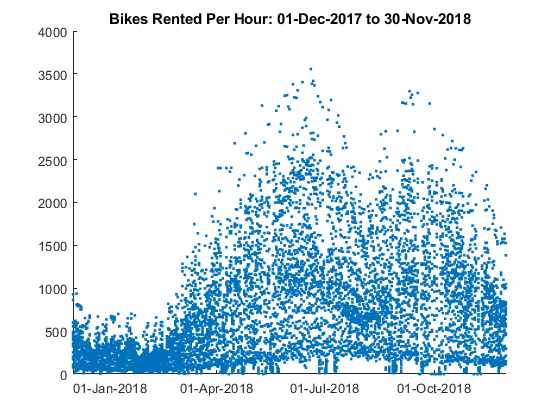

% inputs are all of datamat except col 2
datasetInputs=datamat;
datasetInputs(:,2)=[];
datasetOutputs=datamat(:,2);

dateslist = datetime(datamat(:,1),'ConvertFrom','datenum');

figure
scatter(dateslist, datasetOutputs,'.')
xtickformat('dd-MMM-yyyy')
title(['Bikes Rented Per Hour: ' datestr(dateslist(1)) ' to ' datestr(dateslist(end))])

Scatter plots of inputs and outputs

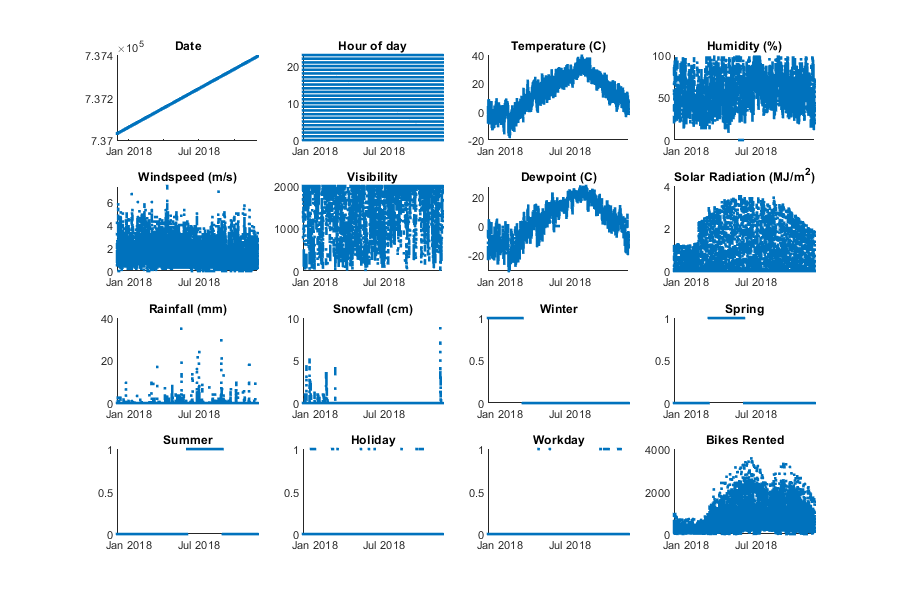

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,4,1)
scatter(dateslist, datasetInputs(:,1),'.')
title('Date')
subplot(4,4,2)
scatter(dateslist, datasetInputs(:,2),'.')
title('Hour of day')
subplot(4,4,3)
scatter(dateslist, datasetInputs(:,3),'.')
title('Temperature (C)')
subplot(4,4,4)
scatter(dateslist, datasetInputs(:,4),'.')
title('Humidity (%)')
subplot(4,4,5)
scatter(dateslist, datasetInputs(:,5),'.')
title('Windspeed (m/s)')
subplot(4,4,6)
scatter(dateslist, datasetInputs(:,6),'.')
title('Visibility')
subplot(4,4,7)
scatter(dateslist, datasetInputs(:,7),'.')
title('Dewpoint (C)')
subplot(4,4,8)
scatter(dateslist, datasetInputs(:,8),'.')
title('Solar Radiation (MJ/m^2)')
subplot(4,4,9)
scatter(dateslist, datasetInputs(:,9),'.')
title('Rainfall (mm)')
subplot(4,4,10)
scatter(dateslist, datasetInputs(:,10),'.')
title('Snowfall (cm)')
subplot(4,4,11)
scatter(dateslist, datasetInputs(:,11),'.')
title('Winter')
subplot(4,4,12)
scatter(dateslist, datasetInputs(:,12),'.')
title('Spring')
subplot(4,4,13)
scatter(dateslist, datasetInputs(:,13),'.')
title('Summer')
subplot(4,4,14)
scatter(dateslist, datasetInputs(:,14),'.')
title('Holiday')
subplot(4,4,15)
scatter(dateslist, datasetInputs(:,15),'.')
title('Workday')
subplot(4,4,16)
scatter(dateslist, datasetOutputs,'.')
title('Bikes Rented')

Histograms of inputs and outputs

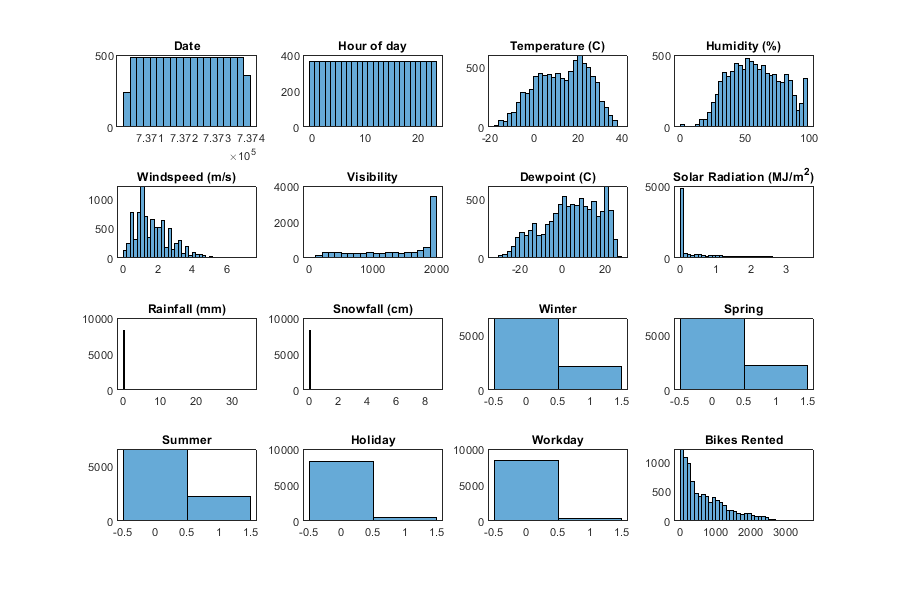

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,4,1)
histogram(datasetInputs(:,1))
title('Date')
subplot(4,4,2)
histogram(datasetInputs(:,2))
title('Hour of day')
subplot(4,4,3)
histogram(datasetInputs(:,3))
title('Temperature (C)')
subplot(4,4,4)
histogram(datasetInputs(:,4))
title('Humidity (%)')
subplot(4,4,5)
histogram(datasetInputs(:,5))
title('Windspeed (m/s)')
subplot(4,4,6)
histogram(datasetInputs(:,6))
title('Visibility')
subplot(4,4,7)
histogram(datasetInputs(:,7))
title('Dewpoint (C)')
subplot(4,4,8)
histogram(datasetInputs(:,8))
title('Solar Radiation (MJ/m^2)')
subplot(4,4,9)
histogram(datasetInputs(:,9))
title('Rainfall (mm)')
subplot(4,4,10)
histogram(datasetInputs(:,10))
title('Snowfall (cm)')
subplot(4,4,11)
histogram(datasetInputs(:,11))
title('Winter')
subplot(4,4,12)
histogram(datasetInputs(:,12))
title('Spring')
subplot(4,4,13)
histogram(datasetInputs(:,13))
title('Summer')
subplot(4,4,14)
histogram(datasetInputs(:,14))
title('Holiday')
subplot(4,4,15)
histogram(datasetInputs(:,15))
title('Workday')
subplot(4,4,16)
histogram(datasetOutputs)
title('Bikes Rented')

Boxplots of inputs and outputs to check for outliers

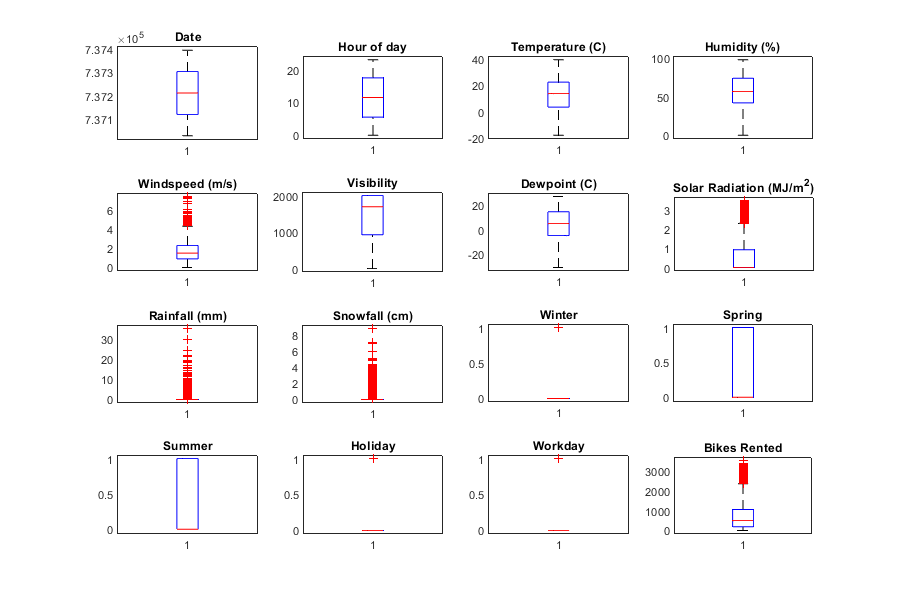

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,4,1)
boxplot(datasetInputs(:,1))
title('Date')
subplot(4,4,2)
boxplot(datasetInputs(:,2))
title('Hour of day')
subplot(4,4,3)
boxplot(datasetInputs(:,3))
title('Temperature (C)')
subplot(4,4,4)
boxplot(datasetInputs(:,4))
title('Humidity (%)')
subplot(4,4,5)
boxplot(datasetInputs(:,5))
title('Windspeed (m/s)')
subplot(4,4,6)
boxplot(datasetInputs(:,6))
title('Visibility')
subplot(4,4,7)
boxplot(datasetInputs(:,7))
title('Dewpoint (C)')
subplot(4,4,8)
boxplot(datasetInputs(:,8))
title('Solar Radiation (MJ/m^2)')
subplot(4,4,9)
boxplot(datasetInputs(:,9))
title('Rainfall (mm)')
subplot(4,4,10)
boxplot(datasetInputs(:,10))
title('Snowfall (cm)')
subplot(4,4,11)
boxplot(datasetInputs(:,11))
title('Winter')
subplot(4,4,12)
boxplot(datasetInputs(:,12))
title('Spring')
subplot(4,4,13)
boxplot(datasetInputs(:,13))
title('Summer')
subplot(4,4,14)
boxplot(datasetInputs(:,14))
title('Holiday')
subplot(4,4,15)
boxplot(datasetInputs(:,15))
title('Workday')
subplot(4,4,16)
boxplot(datasetOutputs)
title('Bikes Rented')

In this case the outliers hold relevant information, so keep them in the dataset. 

% idx=[];
% for ii=1:11
%     idx = [idx isoutlier(datasetInputs(:,ii),'quartiles')];
% end
% % idx = [idx isoutlier(datasetOutputs(:,1),'quartiles')];
% idx(:,12) = any(idx,2);
% idxremove = find(idx(:,12)==1);
% datasetInputs(idxremove,:)=[];
% datasetOutputs(idxremove,:)=[];

Rows and columns of all missing entries

[rowmissingIn,colmissingIn]=find(isnan(datasetInputs))


rowmissingIn =

  0×1 empty double column vector


colmissingIn =

  0×1 empty double column vector



[rowmissingOut]=find(isnan(datasetOutputs))


rowmissingOut =

  0×1 empty double column vector



No missing entries. 

**Scatter plots of all inputs and outputs**

alldata = [datasetInputs,datasetOutputs];
names = {'Day', 'Hour', 'Temp', 'Hum', 'Wind', 'Vis', 'Dewpt', 'Sol', 'Rain', 'Snow','Winter','Spring','Summer','Hol','Wkdy','Bikes'}

names = 1×16 cell array
    {'Day'}    {'Hour'}    {'Temp'}    {'Hum'}    {'Wind'}    {'Vis'}    {'Dewpt'}    {'Sol'}    {'Rain'}    {'Snow'}    {'Winter'}    {'Spring'}    {'Summer'}    {'Hol'}    {'Wkdy'}    {'Bikes'}


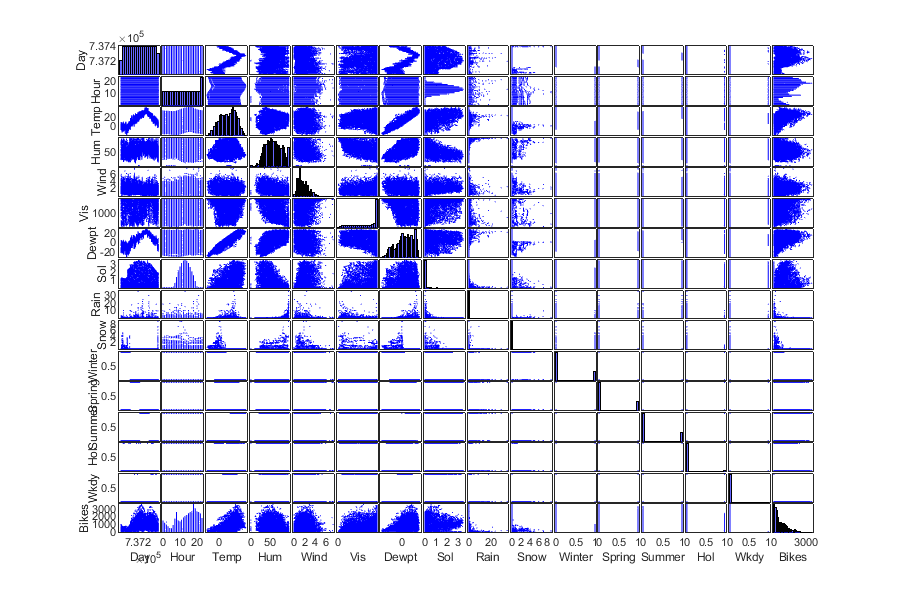

namesCell = cell(1,16);
namesCell(1:16) = names;
figure('Renderer', 'painters', 'Position', [10 10 900 600])
g=gplotmatrix(alldata,[],[],[],[],[],[], 'hist',namesCell);

**Relationships among the inputs:**

Temperature is strongly linearly correlated with Dewpoint.  Day of the Year is strongly correlated with both Temperature and Dewpoint.  Hour of the Day is strongly correlated with Solar Radiation Level.  Weak linear relationships exist between Humidity and Dewpoin; Temperature and Solar Radiation; and Humidity and Solar Radiation. 

**Relationships between the inputs and output:**

The output (Bikes Rented) is weakly correlated to Day of Year, Hour of Day, Temperature, Dewpoint, and Solar Radiation.

**Correlation matrix for the input data**

corrmat = corrcoef(datasetInputs)

corrmat =     1.0000         0    0.5780    0.1701   -0.1621    0.1075    0.5629    0.0911    0.0380   -0.1370   -0.7465   -0.2562    0.2507   -0.0660    0.1838
         0    1.0000    0.1241   -0.2416    0.2852    0.0988    0.0031    0.1451    0.0087   -0.0215   -0.0000    0.0000    0.0000    0.0000   -0.0054
    0.5780    0.1241    1.0000    0.1594   -0.0363    0.0348    0.9128    0.3535    0.0503   -0.2184   -0.7387    0.0080    0.6658   -0.0559    0.0502
    0.1701   -0.2416    0.1594    1.0000   -0.3367   -0.5431    0.5369   -0.4619    0.2364    0.1082   -0.2383    0.0157    0.1926   -0.0503    0.0208
   -0.1621    0.2852   -0.0363   -0.3367    1.0000    0.1715   -0.1765    0.3323   -0.0197   -0.0036    0.1092    0.0839   -0.0647    0.0230   -0.0050
    0.1075    0.0988    0.0348   -0.5431    0.1715    1.0000   -0.1766    0.1497   -0.1676   -0.1217    0.0086   -0.1875    0.0620    0.0318    0.0260
    0.5629    0.0031    0.9128    0.5369   -0.1765   -0.1766    1.0000    0.0944    

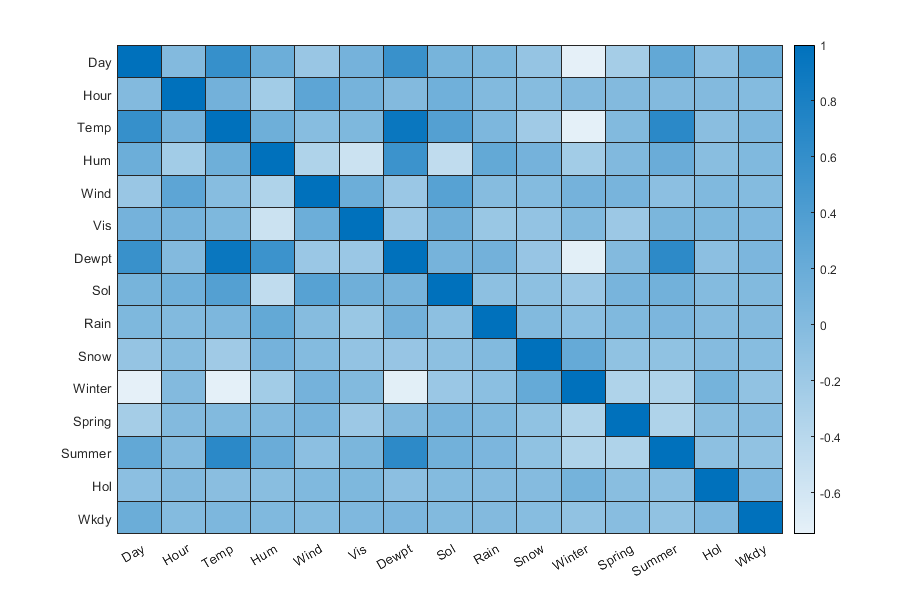

heatmap(namesCell(1:15), namesCell(1:15), corrmat)

**Variance inflation factor for each input factor**

VIF = diag(inv(corrmat))

VIF =    16.2657
    1.2110
   89.5456
   20.5671
    1.3036
    1.6936
  117.3150
    2.0448
    1.0868
    1.1210


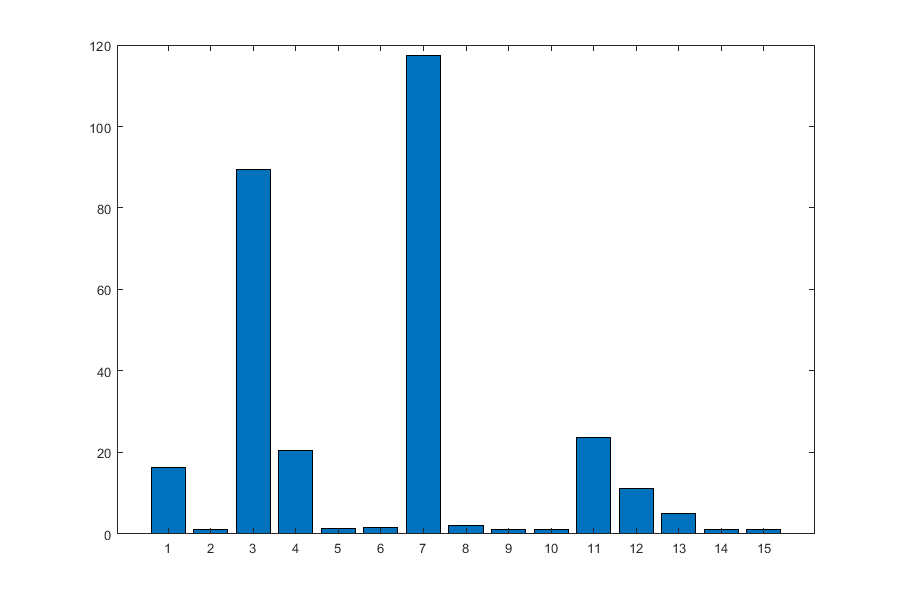

bar(VIF)

**Factors 1, 3, 4, 7, and 11 (Day of Year, Temperature, Humidity, Dew Point, and Winter) have a VIF > 10, indicating that there is strong multicollinearity.  The VIF for Dew Point is the highest, so remove Dew Point as an input and re-evaluate the VIFs.**

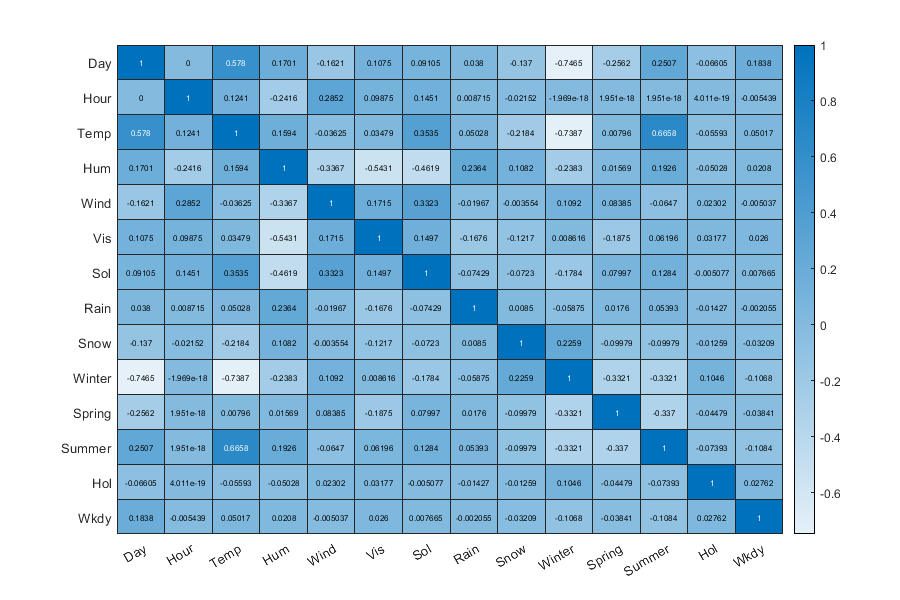

datasetInputs2=datasetInputs;
datasetInputs2(:,7)=[];
corrmat2 = corrcoef(datasetInputs2);
namesCell2=namesCell;
namesCell2(7)=[];
heatmap(namesCell2(1:14), namesCell2(1:14), corrmat2)

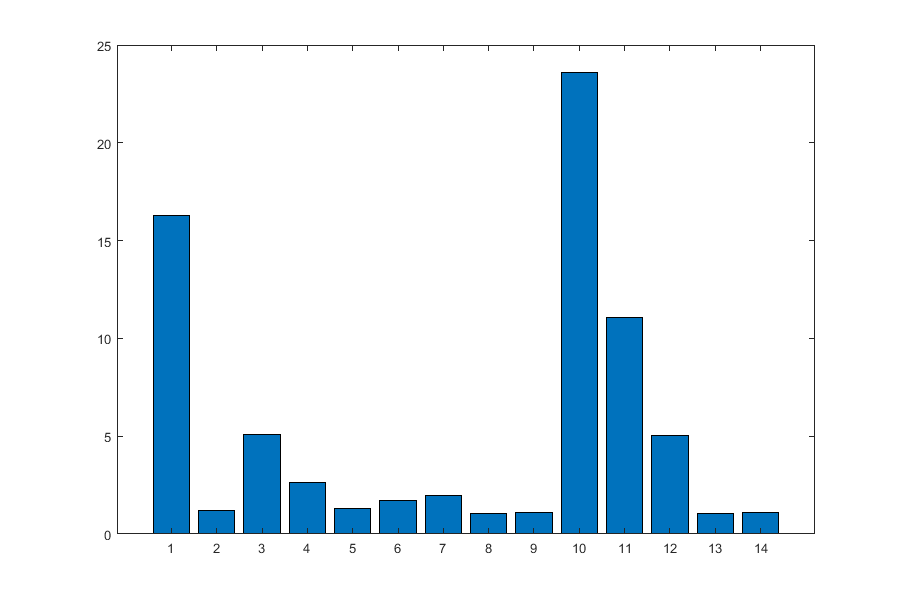

VIF2 = diag(inv(corrmat2));
bar(VIF2)

**With Dew Point removed, factors 1, 10, and 11 (Day of Year, Winter, and Spring) have a VIF > 10, indicating that there is still strong multicollinearity in the data.  The VIF for Winter is the highest, so remove Winter as an input and re-evaluate the VIFs.**

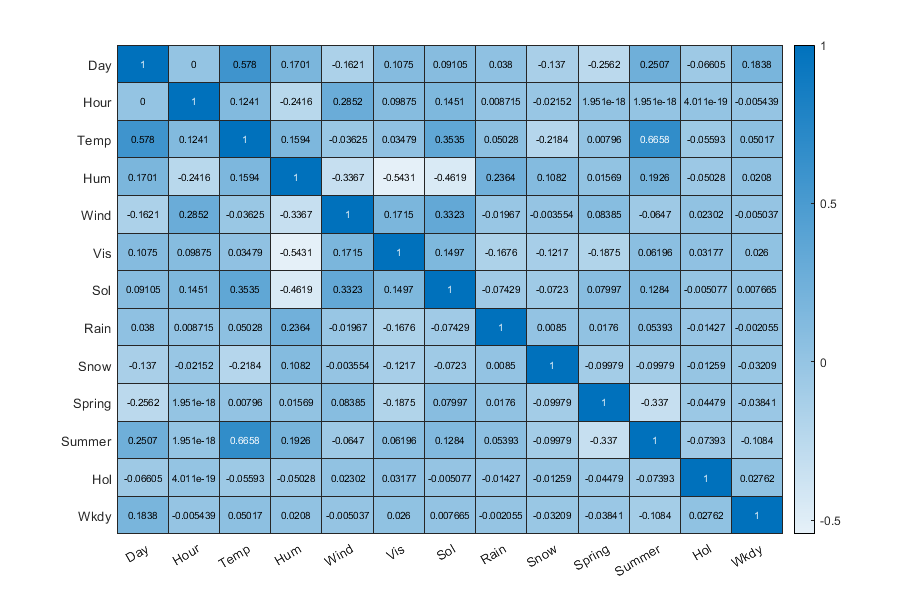

datasetInputs3=datasetInputs2;
datasetInputs3(:,10)=[];
corrmat3 = corrcoef(datasetInputs3);
namesCell3=namesCell2;
namesCell3(10)=[];
heatmap(namesCell3(1:13), namesCell3(1:13), corrmat3)

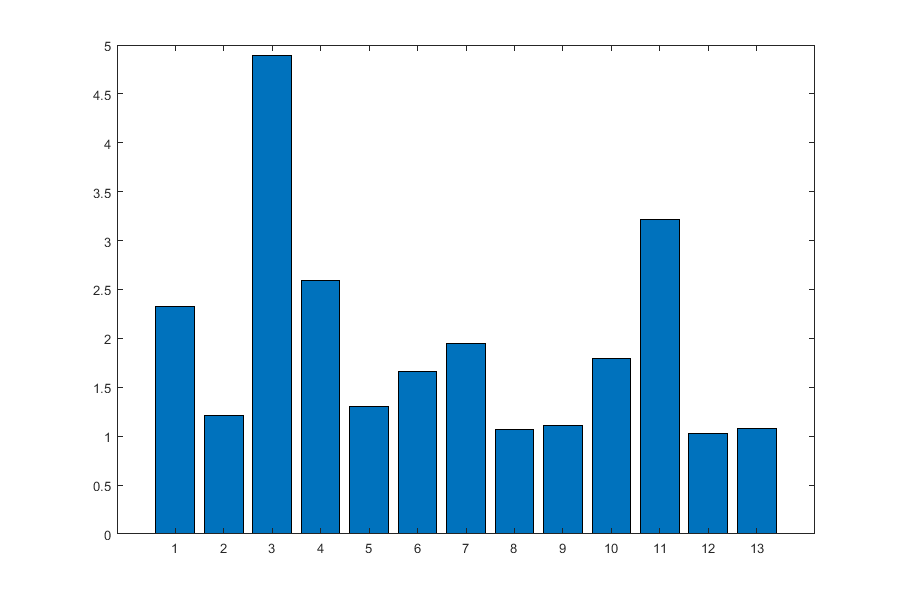

VIF3 = diag(inv(corrmat3));
bar(VIF3)

**Now the correlation matrix and VIFs do not show any strong correlations between the remaining input variables.  The dataset without Dew Point and Winter will be used moving forward.**

clear datasetInputs namesCell datasetInputs2 namesCell2
datasetInputs = datasetInputs3;
namesCell = namesCell3;

**Linear Regression model:**

mdl_linear = fitlm(datasetInputs,datasetOutputs)

mdl_linear = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13

Estimated Coefficients:
                    Estimate         SE         tStat       pValue   
                   ___________    _________    _______    ___________

    (Intercept)    -6.9536e+05        49793    -13.965     7.5227e-44
    x1                 0.94388     0.067551     13.973     6.7487e-44
    x2                  27.217      0.74123     36.718    1.2292e-274
    x3                  29.296       0.8638     33.915    5.4468e-237
    x4                 -7.4577      0.36869    -20.228     5.9225e-89
    x5                  16.137       5.1339     3.1431      0.0016772
    x6                0.024644    0.009897

**Plot of actual vs predicted values:**

predicted = predict(mdl_linear,datasetInputs);
RMSE_linearmodel = sqrt(mean((predicted-datasetOutputs).^2))

RMSE_linearmodel = 436.2951

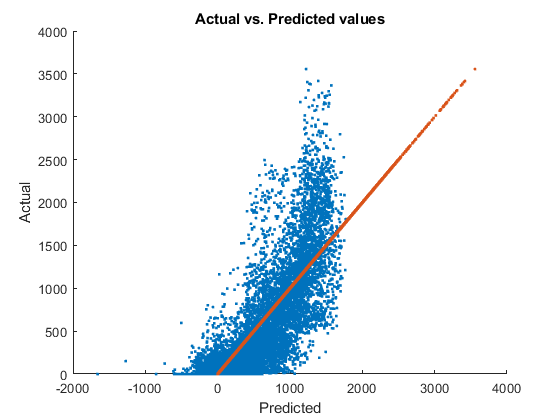

figure
scatter(predicted, datasetOutputs,'.')
hold on
plot(datasetOutputs,datasetOutputs,'.')
title('Actual vs. Predicted values')
xlabel('Predicted')
ylabel('Actual')

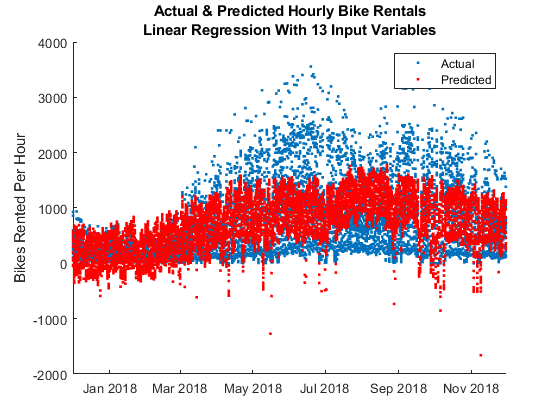


figure
scatter(dateslist,datasetOutputs,'.')
hold on
scatter(dateslist,predicted,'.r')
title({'Actual & Predicted Hourly Bike Rentals','Linear Regression With 13 Input Variables'})
ylabel('Bikes Rented Per Hour')
legend({'Actual','Predicted'})

**Plot of residual vs. predicted values:**

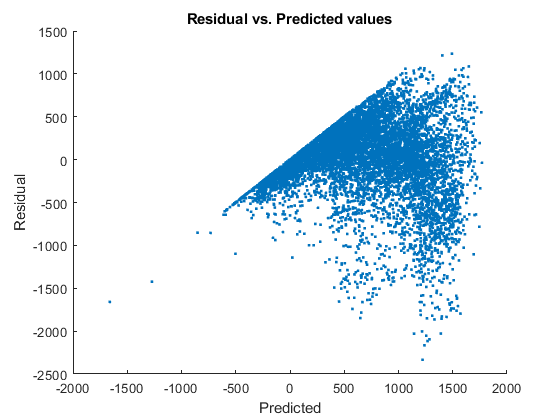

residual = predicted-datasetOutputs;
figure
scatter(predicted,residual,'.')
title('Residual vs. Predicted values')
xlabel('Predicted')
ylabel('Residual')

**Residual histogram:**

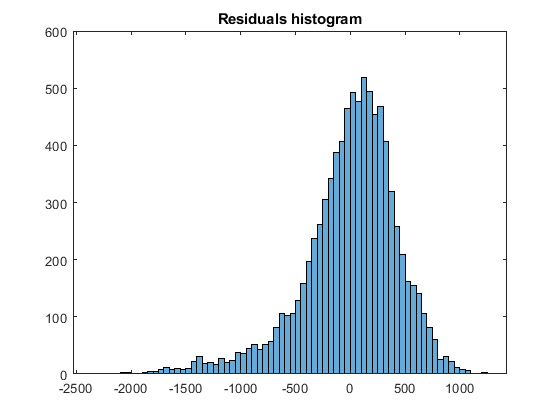

figure
histogram(residual)
title('Residuals histogram')

The scatter plot shows poor prediction performance, especially for higher values of Bikes Rented.  The predicted values do not trend with the actual values.  The ordinary R^2 value of this model is only 0.54.  The histogram of the residuals has a wide peak, with most residuals being within the range [-750, 750].  Considering that most of the data points for Bikes Rented are below 1000, these residuals are very large.

**Therefore, try a neural network model instead.**

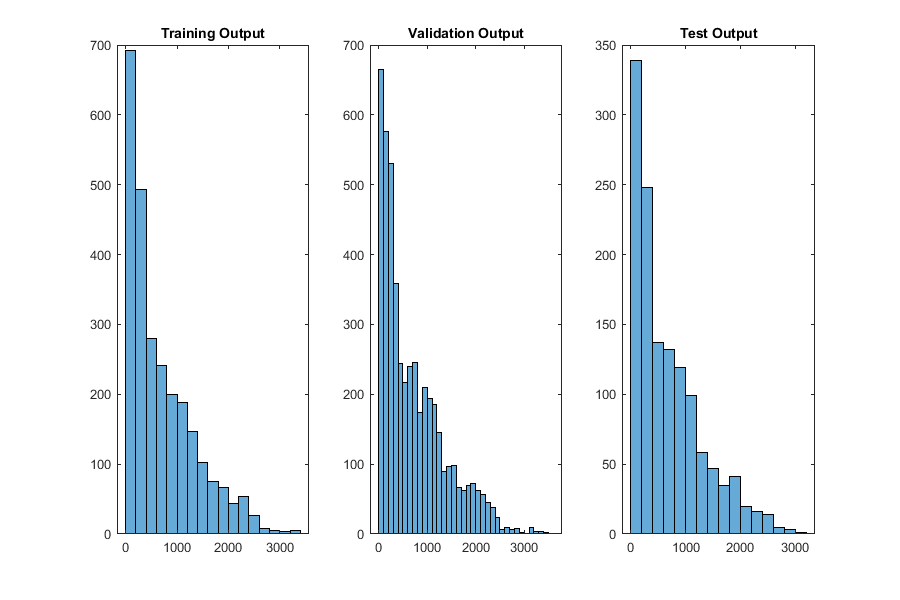

% Randomize data
nruns = size(datasetOutputs,1);
random_row_ind = randperm(nruns);
randInputs = datasetInputs(random_row_ind,:);
randOutputs = datasetOutputs(random_row_ind);

% 15% of rows
testsize = floor(0.15*nruns);

% Divide the input matrix and output vector into a train (30%), validation
% (55%), and a test set (15%)
input_train = randInputs(1:testsize*2,:);
input_val = randInputs((testsize*2+1):(nruns-testsize),:);
input_test = randInputs((nruns-testsize+1):end,:);
output_train = randOutputs(1:testsize*2,:);
output_val = randOutputs((testsize*2+1):(nruns-testsize),:);
output_test = randOutputs((nruns-testsize+1):end,:);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(1,3,1)
h1 = histogram(output_train);
title('Training Output')
subplot(1,3,2)
h2=histogram(output_val);
title('Validation Output')
subplot(1,3,3)
h3=histogram(output_test);
title('Test Output')

h1.Values

ans =    692   493   280   241   199   188   147   102    75    66    44    54    26     8     5     3     5


h2.Values

ans =    665   576   530   359   244   217   240   246   174   209   194   185   146    89    96    98    66    62    69    73    62    57    45    38    23     7    10     6     8     2     1    10     4     4     2     1


h3.Values

ans =    339   248   137   132   119    99    58    47    35    41    20    16    14     5     3     1



% Step 2: Scale training data using mapstd
% mapstd expects each row to be variable and each column to be sample
[scaled_input_train,SF] = mapstd(input_train');
scaled_input_train = scaled_input_train';

% Apply these scale factors to validation and test data
scaled_input_val = mapstd('apply',input_val',SF);
scaled_input_test = mapstd('apply',input_test',SF);
scaled_input_val = scaled_input_val';
scaled_input_test = scaled_input_test';

% Output vector does not need to be scaled

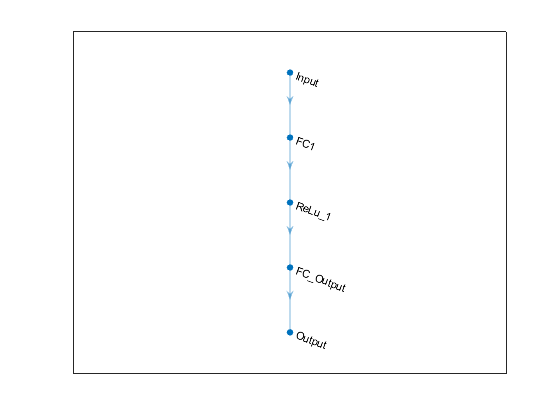

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:08 |      1074.80 |       966.47 |  577598.0625 |  467036.6563 |          0.0100 |


|       1 |          50 |       00:00:10 |       773.15 |              |  298881.6875 |              |          0.0100 |


|       1 |          82 |       00:00:11 |      1058.99 |       956.58 |  560732.3125 |  457520.4063 |          0.0100 |


|       2 |         100 |       00:00:12 |      1141.95 |              |  652030.2500 |              |          0.0100 |


|       2 |         150 |       00:00:12 |       774.63 |              |  300025.3438 |              |          0.0100 |


|       2 |         164 |       00:00:13 |       731.25 |       928.92 |  267366.8750 |  431441.8125 |          0.0100 |


|       3 |         200 |       00:00:13 |      1115.55 |              |  622223.0625 |              |          0.0100 |


|       3 |         246 |       00:00:14 |       632.45 |       862.45 |  199993.7969 |  371908.1563 |          0.0100 |


|       4 |         250 |       00:00:15 |      1204.70 |              |  725645.8750 |              |          0.0100 |


|       4 |         300 |       00:00:16 |       761.76 |              |  290139.7500 |              |          0.0100 |


|       4 |         328 |       00:00:17 |       855.66 |       755.59 |  366075.5313 |  285458.5625 |          0.0100 |


|       5 |         350 |       00:00:17 |       893.35 |              |  399037.4688 |              |          0.0100 |


|       5 |         400 |       00:00:19 |       701.98 |              |  246386.0469 |              |          0.0100 |


|       5 |         410 |       00:00:19 |       533.54 |       637.02 |  142331.2656 |  202895.0313 |          0.0100 |


|       6 |         450 |       00:00:19 |       551.43 |              |  152037.6719 |              |          0.0050 |


|       6 |         492 |       00:00:20 |       643.09 |       583.63 |  206783.6875 |  170313.7500 |          0.0050 |


|       7 |         500 |       00:00:21 |       615.59 |              |  189476.1094 |              |          0.0050 |


|       7 |         550 |       00:00:22 |       420.81 |              |   88541.3438 |              |          0.0050 |


|       7 |         574 |       00:00:23 |       416.70 |       538.70 |   86820.9766 |  145101.2813 |          0.0050 |


|       8 |         600 |       00:00:23 |       639.50 |              |  204481.5938 |              |          0.0050 |


|       8 |         650 |       00:00:24 |       412.18 |              |   84945.2266 |              |          0.0050 |


|       8 |         656 |       00:00:24 |       481.25 |       504.44 |  115802.0313 |  127230.0859 |          0.0050 |


|       9 |         700 |       00:00:25 |       485.83 |              |  118017.3047 |              |          0.0050 |


|       9 |         738 |       00:00:25 |       337.04 |       477.81 |   56798.6758 |  114149.7109 |          0.0050 |


|      10 |         750 |       00:00:26 |       418.83 |              |   87708.7578 |              |          0.0050 |


|      10 |         800 |       00:00:26 |       384.01 |              |   73733.5234 |              |          0.0050 |


|      10 |         820 |       00:00:27 |       432.02 |       459.47 |   93321.0469 |  105557.4844 |          0.0050 |


|      11 |         850 |       00:00:27 |       427.55 |              |   91398.0938 |              |          0.0025 |


|      11 |         900 |       00:00:28 |       413.54 |              |   85507.3281 |              |          0.0025 |


|      11 |         902 |       00:00:28 |       317.88 |       452.61 |   50523.0859 |  102429.0078 |          0.0025 |


|      12 |         950 |       00:00:29 |       448.59 |              |  100616.8672 |              |          0.0025 |


|      12 |         984 |       00:00:29 |       274.85 |       446.53 |   37772.5781 |   99694.5547 |          0.0025 |


|      13 |        1000 |       00:00:30 |       519.24 |              |  134805.6875 |              |          0.0025 |


|      13 |        1050 |       00:00:31 |       258.59 |              |   33435.1055 |              |          0.0025 |


|      13 |        1066 |       00:00:32 |       345.32 |       441.77 |   59623.6758 |   97582.3359 |          0.0025 |


|      14 |        1100 |       00:00:33 |       296.60 |              |   43987.1523 |              |          0.0025 |


|      14 |        1148 |       00:00:34 |       482.88 |       437.58 |  116586.4766 |   95736.3594 |          0.0025 |


|      15 |        1150 |       00:00:34 |       469.30 |              |  110121.8125 |              |          0.0025 |


|      15 |        1200 |       00:00:35 |       456.13 |              |  104026.9531 |              |          0.0025 |


|      15 |        1230 |       00:00:37 |       366.58 |       434.09 |   67189.1250 |   94218.4375 |          0.0025 |


|      16 |        1250 |       00:00:37 |       401.90 |              |   80762.8906 |              |          0.0012 |


|      16 |        1300 |       00:00:38 |       511.12 |              |  130620.5781 |              |          0.0012 |


|      16 |        1312 |       00:00:38 |       433.38 |       432.69 |   93907.9063 |   93609.6328 |          0.0012 |


|      17 |        1350 |       00:00:39 |       386.80 |              |   74806.6094 |              |          0.0012 |


|      17 |        1394 |       00:00:39 |       406.86 |       431.43 |   82768.7891 |   93064.1563 |          0.0012 |


|      18 |        1400 |       00:00:39 |       319.84 |              |   51147.3438 |              |          0.0012 |


|      18 |        1450 |       00:00:40 |       333.62 |              |   55652.7344 |              |          0.0012 |


|      18 |        1476 |       00:00:41 |       510.09 |       430.22 |  130095.3906 |   92546.0000 |          0.0012 |


|      19 |        1500 |       00:00:41 |       396.55 |              |   78627.1250 |              |          0.0012 |


|      19 |        1550 |       00:00:42 |       428.85 |              |   91954.5703 |              |          0.0012 |


|      19 |        1558 |       00:00:42 |       427.04 |       429.20 |   91183.1875 |   92106.0859 |          0.0012 |


|      20 |        1600 |       00:00:43 |       422.00 |              |   89040.8594 |              |          0.0012 |


|      20 |        1640 |       00:00:43 |       592.40 |       428.28 |  175471.1875 |   91712.6484 |          0.0012 |


|      21 |        1650 |       00:00:43 |       377.55 |              |   71272.5625 |              |          0.0006 |


|      21 |        1700 |       00:00:44 |       318.75 |              |   50800.0313 |              |          0.0006 |


|      21 |        1722 |       00:00:44 |       378.80 |       427.82 |   71746.0938 |   91516.1797 |          0.0006 |


|      22 |        1750 |       00:00:45 |       456.63 |              |  104257.4375 |              |          0.0006 |


|      22 |        1800 |       00:00:45 |       358.10 |              |   64117.8320 |              |          0.0006 |


|      22 |        1804 |       00:00:45 |       503.89 |       427.38 |  126954.4922 |   91328.3750 |          0.0006 |


|      23 |        1850 |       00:00:46 |       424.23 |              |   89984.7266 |              |          0.0006 |


|      23 |        1886 |       00:00:47 |       410.97 |       426.99 |   84450.1484 |   91160.9297 |          0.0006 |


|      24 |        1900 |       00:00:47 |       366.74 |              |   67250.0703 |              |          0.0006 |


|      24 |        1950 |       00:00:48 |       373.62 |              |   69794.8125 |              |          0.0006 |


|      24 |        1968 |       00:00:48 |       343.17 |       426.59 |   58882.5586 |   90988.8047 |          0.0006 |


|      25 |        2000 |       00:00:48 |       463.13 |              |  107246.5391 |              |          0.0006 |


|      25 |        2050 |       00:00:49 |       619.73 |       426.19 |  192034.5000 |   90818.5781 |          0.0006 |


|      26 |        2100 |       00:00:50 |       371.28 |              |   68925.0859 |              |          0.0003 |


|      26 |        2132 |       00:00:50 |       389.88 |       426.01 |   76002.0234 |   90740.3125 |          0.0003 |


|      27 |        2150 |       00:00:51 |       378.43 |              |   71605.8672 |              |          0.0003 |


|      27 |        2200 |       00:00:52 |       481.98 |              |  116153.3281 |              |          0.0003 |


|      27 |        2214 |       00:00:52 |       382.64 |       425.82 |   73207.6484 |   90660.0391 |          0.0003 |


|      28 |        2250 |       00:00:52 |       495.41 |              |  122713.2188 |              |          0.0003 |


|      28 |        2296 |       00:00:53 |       303.38 |       425.65 |   46020.8086 |   90590.0703 |          0.0003 |


|      29 |        2300 |       00:00:53 |       363.02 |              |   65893.4063 |              |          0.0003 |


|      29 |        2350 |       00:00:54 |       529.39 |              |  140125.0938 |              |          0.0003 |


|      29 |        2378 |       00:00:54 |       320.01 |       425.49 |   51204.4023 |   90518.9375 |          0.0003 |


|      30 |        2400 |       00:00:55 |       288.65 |              |   41658.6875 |              |          0.0003 |


|      30 |        2450 |       00:00:55 |       438.54 |              |   96159.1406 |              |          0.0003 |


|      30 |        2460 |       00:00:55 |       395.38 |       425.31 |   78163.0469 |   90444.4063 |          0.0003 |


|      31 |        2500 |       00:00:56 |       500.22 |              |  125109.9297 |              |          0.0002 |


|      31 |        2542 |       00:00:57 |       339.51 |       425.24 |   57631.9023 |   90413.8438 |          0.0002 |


|      32 |        2550 |       00:00:57 |       338.10 |              |   57157.2383 |              |          0.0002 |


|      32 |        2600 |       00:00:58 |       469.06 |              |  110008.3750 |              |          0.0002 |


|      32 |        2624 |       00:00:58 |       326.06 |       425.17 |   53157.9102 |   90383.9297 |          0.0002 |


|      33 |        2650 |       00:00:58 |       290.20 |              |   42107.1445 |              |          0.0002 |


|      33 |        2700 |       00:00:59 |       339.40 |              |   57594.5195 |              |          0.0002 |


|      33 |        2706 |       00:00:59 |       328.90 |       425.09 |   54086.3750 |   90350.5234 |          0.0002 |


|      34 |        2750 |       00:01:00 |       324.78 |              |   52741.4922 |              |          0.0002 |


|      34 |        2788 |       00:01:00 |       353.09 |       425.01 |   62335.2344 |   90317.8438 |          0.0002 |


|      35 |        2800 |       00:01:01 |       450.02 |              |  101257.8359 |              |          0.0002 |


|      35 |        2850 |       00:01:01 |       524.54 |              |  137572.6250 |              |          0.0002 |


|      35 |        2870 |       00:01:02 |       321.46 |       424.94 |   51668.5313 |   90286.8438 |          0.0002 |


|      36 |        2900 |       00:01:02 |       483.84 |              |  117049.5313 |              |      7.8125e-05 |


|      36 |        2950 |       00:01:03 |       316.91 |              |   50215.2656 |              |      7.8125e-05 |


|      36 |        2952 |       00:01:03 |       316.16 |       424.90 |   49979.6914 |   90271.1875 |      7.8125e-05 |


|      37 |        3000 |       00:01:03 |       476.28 |              |  113421.9766 |              |      7.8125e-05 |


|      37 |        3034 |       00:01:04 |       318.32 |       424.87 |   50663.8320 |   90256.5078 |      7.8125e-05 |


|      38 |        3050 |       00:01:04 |       430.80 |              |   92795.7188 |              |      7.8125e-05 |


|      38 |        3100 |       00:01:05 |       312.68 |              |   48885.5156 |              |      7.8125e-05 |


|      38 |        3116 |       00:01:05 |       434.08 |       424.83 |   94212.0625 |   90241.4375 |      7.8125e-05 |


|      39 |        3150 |       00:01:06 |       363.61 |              |   66104.8672 |              |      7.8125e-05 |


|      39 |        3198 |       00:01:07 |       328.44 |       424.80 |   53934.8477 |   90225.7656 |      7.8125e-05 |


|      40 |        3200 |       00:01:07 |       277.69 |              |   38556.1836 |              |      7.8125e-05 |


|      40 |        3250 |       00:01:07 |       360.43 |              |   64954.2031 |              |      7.8125e-05 |


|      40 |        3280 |       00:01:08 |       376.75 |       424.76 |   70970.1563 |   90209.7031 |      7.8125e-05 |


|      41 |        3300 |       00:01:08 |       334.03 |              |   55788.5195 |              |      3.9062e-05 |


|      41 |        3350 |       00:01:09 |       316.00 |              |   49926.9727 |              |      3.9062e-05 |


|      41 |        3362 |       00:01:09 |       507.90 |       424.74 |  128979.3281 |   90201.9844 |      3.9062e-05 |


|      42 |        3400 |       00:01:10 |       435.72 |              |   94926.4844 |              |      3.9062e-05 |


|      42 |        3444 |       00:01:11 |       408.23 |       424.72 |   83327.4141 |   90194.8125 |      3.9062e-05 |


|      43 |        3450 |       00:01:11 |       540.97 |              |  146323.1875 |              |      3.9062e-05 |


|      43 |        3500 |       00:01:12 |       506.61 |              |  128325.8516 |              |      3.9062e-05 |


|      43 |        3526 |       00:01:12 |       390.89 |       424.70 |   76397.1094 |   90187.0938 |      3.9062e-05 |


|      44 |        3550 |       00:01:13 |       403.67 |              |   81476.6172 |              |      3.9062e-05 |


|      44 |        3600 |       00:01:13 |       505.82 |              |  127928.9375 |              |      3.9062e-05 |


|      44 |        3608 |       00:01:13 |       524.81 |       424.69 |  137711.2188 |   90179.6094 |      3.9062e-05 |


|      45 |        3650 |       00:01:14 |       352.51 |              |   62131.8359 |              |      3.9062e-05 |


|      45 |        3690 |       00:01:15 |       314.08 |       424.67 |   49322.0156 |   90171.7734 |      3.9062e-05 |


|      46 |        3700 |       00:01:15 |       387.60 |              |   75118.1250 |              |      1.9531e-05 |


|      46 |        3750 |       00:01:16 |       285.26 |              |   40687.0859 |              |      1.9531e-05 |


|      46 |        3772 |       00:01:16 |       297.18 |       424.66 |   44159.4336 |   90167.8594 |      1.9531e-05 |


|      47 |        3800 |       00:01:17 |       578.26 |              |  167190.8438 |              |      1.9531e-05 |


|      47 |        3850 |       00:01:17 |       588.17 |              |  172969.7188 |              |      1.9531e-05 |


|      47 |        3854 |       00:01:18 |       448.83 |       424.65 |  100723.1953 |   90164.0234 |      1.9531e-05 |


|      48 |        3900 |       00:01:18 |       444.65 |              |   98855.5234 |              |      1.9531e-05 |


|      48 |        3936 |       00:01:19 |       451.07 |       424.64 |  101731.0547 |   90160.1094 |      1.9531e-05 |


|      49 |        3950 |       00:01:19 |       358.44 |              |   64240.7773 |              |      1.9531e-05 |


|      49 |        4000 |       00:01:19 |       307.42 |              |   47252.1055 |              |      1.9531e-05 |


|      49 |        4018 |       00:01:20 |       481.50 |       424.63 |  115921.3906 |   90156.3281 |      1.9531e-05 |


|      50 |        4050 |       00:01:20 |       503.78 |              |  126898.9688 |              |      1.9531e-05 |


|      50 |        4100 |       00:01:21 |       279.75 |       424.62 |   39128.7305 |   90152.4922 |      1.9531e-05 |


|      51 |        4150 |       00:01:22 |       547.08 |              |  149646.1719 |              |      9.7656e-06 |


|      51 |        4182 |       00:01:23 |       325.26 |       424.62 |   52896.0977 |   90150.7188 |      9.7656e-06 |


|      52 |        4200 |       00:01:23 |       351.41 |              |   61744.4453 |              |      9.7656e-06 |


|      52 |        4250 |       00:01:24 |       325.44 |              |   52955.6250 |              |      9.7656e-06 |


|      52 |        4264 |       00:01:24 |       380.63 |       424.61 |   72437.7344 |   90148.8516 |      9.7656e-06 |


|      53 |        4300 |       00:01:24 |       406.17 |              |   82487.5703 |              |      9.7656e-06 |


|      53 |        4346 |       00:01:25 |       435.17 |       424.61 |   94687.5703 |   90147.1094 |      9.7656e-06 |


|      54 |        4350 |       00:01:25 |       517.63 |              |  133968.6563 |              |      9.7656e-06 |


|      54 |        4400 |       00:01:26 |       376.05 |              |   70706.6328 |              |      9.7656e-06 |


|      54 |        4428 |       00:01:27 |       341.61 |       424.61 |   58348.2813 |   90145.2891 |      9.7656e-06 |


|      55 |        4450 |       00:01:27 |       433.48 |              |   93951.9375 |              |      9.7656e-06 |


|      55 |        4500 |       00:01:28 |       376.26 |              |   70786.8047 |              |      9.7656e-06 |


|      55 |        4510 |       00:01:28 |       480.42 |       424.60 |  115403.5625 |   90143.3750 |      9.7656e-06 |


|      56 |        4550 |       00:01:29 |       269.18 |              |   36229.8320 |              |      4.8828e-06 |


|      56 |        4592 |       00:01:29 |       407.47 |       424.60 |   83017.8203 |   90142.4609 |      4.8828e-06 |


|      57 |        4600 |       00:01:29 |       360.35 |              |   64927.3867 |              |      4.8828e-06 |


|      57 |        4650 |       00:01:30 |       317.75 |              |   50482.6563 |              |      4.8828e-06 |


|      57 |        4674 |       00:01:30 |       296.38 |       424.60 |   43919.5742 |   90141.3984 |      4.8828e-06 |


|      58 |        4700 |       00:01:31 |       336.56 |              |   56636.6172 |              |      4.8828e-06 |


|      58 |        4750 |       00:01:32 |       564.54 |              |  159351.7656 |              |      4.8828e-06 |


|      58 |        4756 |       00:01:32 |       352.46 |       424.59 |   62114.7344 |   90140.2109 |      4.8828e-06 |


|      59 |        4800 |       00:01:33 |       338.65 |              |   57340.6211 |              |      4.8828e-06 |


|      59 |        4838 |       00:01:33 |       420.96 |       424.59 |   88601.6641 |   90139.1875 |      4.8828e-06 |


|      60 |        4850 |       00:01:33 |       257.58 |              |   33173.1719 |              |      4.8828e-06 |


|      60 |        4900 |       00:01:34 |       390.33 |              |   76177.7578 |              |      4.8828e-06 |


|      60 |        4920 |       00:01:34 |       376.11 |       424.59 |   70729.4609 |   90138.2734 |      4.8828e-06 |


|      61 |        4950 |       00:01:35 |       288.93 |              |   41741.4961 |              |      2.4414e-06 |


|      61 |        5000 |       00:01:36 |       376.28 |              |   70794.6484 |              |      2.4414e-06 |


|      61 |        5002 |       00:01:36 |       408.53 |       424.59 |   83447.4688 |   90137.7734 |      2.4414e-06 |


|      62 |        5050 |       00:01:37 |       415.39 |              |   86275.6250 |              |      2.4414e-06 |


|      62 |        5084 |       00:01:37 |       482.84 |       424.59 |  116565.8984 |   90137.2500 |      2.4414e-06 |


|      63 |        5100 |       00:01:38 |       371.74 |              |   69095.4297 |              |      2.4414e-06 |


|      63 |        5150 |       00:01:38 |       401.36 |              |   80543.7656 |              |      2.4414e-06 |


|      63 |        5166 |       00:01:39 |       332.48 |       424.59 |   55270.4141 |   90136.7500 |      2.4414e-06 |


|      64 |        5200 |       00:01:39 |       358.99 |              |   64435.8516 |              |      2.4414e-06 |


|      64 |        5248 |       00:01:40 |       430.70 |       424.59 |   92753.1563 |   90136.2891 |      2.4414e-06 |


|      65 |        5250 |       00:01:40 |       345.10 |              |   59546.0820 |              |      2.4414e-06 |


|      65 |        5300 |       00:01:41 |       395.02 |              |   78020.3672 |              |      2.4414e-06 |


|      65 |        5330 |       00:01:41 |       320.53 |       424.58 |   51368.4258 |   90135.7969 |      2.4414e-06 |


|      66 |        5350 |       00:01:42 |       306.57 |              |   46993.0391 |              |      1.2207e-06 |


|      66 |        5400 |       00:01:43 |       296.24 |              |   43879.5938 |              |      1.2207e-06 |


|      66 |        5412 |       00:01:43 |       384.96 |       424.58 |   74096.0391 |   90135.5781 |      1.2207e-06 |


|      67 |        5450 |       00:01:43 |       349.11 |              |   60939.0000 |              |      1.2207e-06 |


|      67 |        5494 |       00:01:44 |       351.51 |       424.58 |   61779.4102 |   90135.3359 |      1.2207e-06 |


|      68 |        5500 |       00:01:44 |       530.14 |              |  140523.3281 |              |      1.2207e-06 |


|      68 |        5550 |       00:01:45 |       476.79 |              |  113662.3203 |              |      1.2207e-06 |


|      68 |        5576 |       00:01:45 |       542.43 |       424.58 |  147117.2344 |   90135.0859 |      1.2207e-06 |


|      69 |        5600 |       00:01:46 |       507.41 |              |  128731.4531 |              |      1.2207e-06 |


|      69 |        5650 |       00:01:47 |       437.86 |              |   95860.5625 |              |      1.2207e-06 |


|      69 |        5658 |       00:01:47 |       353.60 |       424.58 |   62515.8320 |   90134.8750 |      1.2207e-06 |


|      70 |        5700 |       00:01:47 |       448.18 |              |  100433.6641 |              |      1.2207e-06 |


|      70 |        5740 |       00:01:48 |       401.19 |       424.58 |   80475.2813 |   90134.5859 |      1.2207e-06 |


|      71 |        5750 |       00:01:48 |       371.48 |              |   68997.8594 |              |      6.1035e-07 |


|      71 |        5800 |       00:01:49 |       347.23 |              |   60283.3711 |              |      6.1035e-07 |


|      71 |        5822 |       00:01:49 |       421.30 |       424.58 |   88748.6016 |   90134.5391 |      6.1035e-07 |


|      72 |        5850 |       00:01:50 |       494.49 |              |  122259.0469 |              |      6.1035e-07 |


|      72 |        5900 |       00:01:51 |       317.45 |              |   50385.7617 |              |      6.1035e-07 |


|      72 |        5904 |       00:01:51 |       319.86 |       424.58 |   51154.0781 |   90134.4219 |      6.1035e-07 |


|      73 |        5950 |       00:01:52 |       446.49 |              |   99676.0547 |              |      6.1035e-07 |


|      73 |        5986 |       00:01:52 |       496.64 |       424.58 |  123325.0313 |   90134.3438 |      6.1035e-07 |


|      74 |        6000 |       00:01:53 |       407.86 |              |   83175.5547 |              |      6.1035e-07 |


|      74 |        6050 |       00:01:53 |       377.80 |              |   71366.3594 |              |      6.1035e-07 |


|      74 |        6068 |       00:01:54 |       333.57 |       424.58 |   55634.2852 |   90134.3047 |      6.1035e-07 |


|      75 |        6100 |       00:01:54 |       291.38 |              |   42451.1289 |              |      6.1035e-07 |


|      75 |        6150 |       00:01:55 |       431.66 |       424.58 |   93167.2656 |   90134.2266 |      6.1035e-07 |


|      76 |        6200 |       00:01:56 |       419.42 |              |   87956.2188 |              |      3.0518e-07 |


|      76 |        6232 |       00:01:56 |       333.30 |       424.58 |   55544.3516 |   90134.2109 |      3.0518e-07 |


|      77 |        6250 |       00:01:57 |       475.51 |              |  113052.5938 |              |      3.0518e-07 |


|      77 |        6300 |       00:01:57 |       370.43 |              |   68609.2734 |              |      3.0518e-07 |


|      77 |        6314 |       00:01:58 |       279.27 |       424.58 |   38994.8438 |   90134.1563 |      3.0518e-07 |


|      78 |        6350 |       00:01:58 |       435.06 |              |   94640.4219 |              |      3.0518e-07 |


|      78 |        6396 |       00:01:59 |       533.47 |       424.58 |  142296.2656 |   90134.1094 |      3.0518e-07 |


|      79 |        6400 |       00:01:59 |       565.44 |              |  159861.2031 |              |      3.0518e-07 |


|      79 |        6450 |       00:02:00 |       394.15 |              |   77675.1484 |              |      3.0518e-07 |


|      79 |        6478 |       00:02:00 |       237.60 |       424.58 |   28227.3223 |   90134.1094 |      3.0518e-07 |


|      80 |        6500 |       00:02:01 |       336.85 |              |   56735.4648 |              |      3.0518e-07 |


|      80 |        6550 |       00:02:02 |       338.07 |              |   57146.0703 |              |      3.0518e-07 |


|      80 |        6560 |       00:02:02 |       402.99 |       424.58 |   81200.6797 |   90134.1172 |      3.0518e-07 |


|      81 |        6600 |       00:02:03 |       384.46 |              |   73905.1406 |              |      1.5259e-07 |


|      81 |        6642 |       00:02:03 |       412.30 |       424.58 |   84993.9844 |   90134.0859 |      1.5259e-07 |


|      82 |        6650 |       00:02:03 |       262.44 |              |   34437.5820 |              |      1.5259e-07 |


|      82 |        6700 |       00:02:04 |       454.15 |              |  103124.3828 |              |      1.5259e-07 |


|      82 |        6724 |       00:02:05 |       344.39 |       424.58 |   59302.9063 |   90134.1094 |      1.5259e-07 |


|      83 |        6750 |       00:02:05 |       549.85 |              |  151166.1406 |              |      1.5259e-07 |


|      83 |        6800 |       00:02:06 |       404.93 |              |   81984.5547 |              |      1.5259e-07 |


|      83 |        6806 |       00:02:06 |       325.31 |       424.58 |   52912.9102 |   90134.0625 |      1.5259e-07 |


|      84 |        6850 |       00:02:06 |       373.75 |              |   69844.9453 |              |      1.5259e-07 |


|      84 |        6888 |       00:02:07 |       404.64 |       424.58 |   81865.1797 |   90134.0625 |      1.5259e-07 |


|      85 |        6900 |       00:02:07 |       335.72 |              |   56355.3320 |              |      1.5259e-07 |


|      85 |        6950 |       00:02:08 |       421.26 |              |   88730.3750 |              |      1.5259e-07 |


|      85 |        6970 |       00:02:08 |       479.01 |       424.58 |  114727.5391 |   90134.0391 |      1.5259e-07 |


|      86 |        7000 |       00:02:09 |       525.32 |              |  137982.9375 |              |      7.6294e-08 |


|      86 |        7050 |       00:02:10 |       387.90 |              |   75235.1328 |              |      7.6294e-08 |


|      86 |        7052 |       00:02:10 |       509.16 |       424.58 |  129620.8906 |   90134.0391 |      7.6294e-08 |


|      87 |        7100 |       00:02:11 |       508.82 |              |  129446.5234 |              |      7.6294e-08 |


|      87 |        7134 |       00:02:11 |       396.19 |       424.58 |   78483.1172 |   90134.0625 |      7.6294e-08 |


|      88 |        7150 |       00:02:12 |       348.47 |              |   60715.6172 |              |      7.6294e-08 |


|      88 |        7200 |       00:02:12 |       515.81 |              |  133027.5781 |              |      7.6294e-08 |


|      88 |        7216 |       00:02:12 |       486.85 |       424.58 |  118513.7422 |   90134.0391 |      7.6294e-08 |


|      89 |        7250 |       00:02:13 |       402.56 |              |   81026.1797 |              |      7.6294e-08 |


|      89 |        7298 |       00:02:14 |       392.73 |       424.58 |   77119.3750 |   90134.0234 |      7.6294e-08 |


|      90 |        7300 |       00:02:14 |       375.36 |              |   70449.3203 |              |      7.6294e-08 |


|      90 |        7350 |       00:02:15 |       427.40 |              |   91334.8203 |              |      7.6294e-08 |


|      90 |        7380 |       00:02:15 |       388.37 |       424.58 |   75414.8750 |   90134.0547 |      7.6294e-08 |


|      91 |        7400 |       00:02:16 |       566.21 |              |  160297.1563 |              |      3.8147e-08 |


|      91 |        7450 |       00:02:16 |       489.89 |              |  119995.4375 |              |      3.8147e-08 |


|      91 |        7462 |       00:02:17 |       431.13 |       424.58 |   92935.4375 |   90134.0547 |      3.8147e-08 |


|      92 |        7500 |       00:02:17 |       285.26 |              |   40686.8086 |              |      3.8147e-08 |


|      92 |        7544 |       00:02:18 |       502.66 |       424.58 |  126334.0938 |   90134.0391 |      3.8147e-08 |


|      93 |        7550 |       00:02:18 |       307.34 |              |   47229.5156 |              |      3.8147e-08 |


|      93 |        7600 |       00:02:19 |       365.66 |              |   66854.3828 |              |      3.8147e-08 |


|      93 |        7626 |       00:02:19 |       409.10 |       424.58 |   83679.6094 |   90134.0391 |      3.8147e-08 |


|      94 |        7650 |       00:02:20 |       485.12 |              |  117668.5703 |              |      3.8147e-08 |


|      94 |        7700 |       00:02:20 |       290.63 |              |   42231.5977 |              |      3.8147e-08 |


|      94 |        7708 |       00:02:21 |       532.04 |       424.58 |  141534.8906 |   90134.0078 |      3.8147e-08 |


|      95 |        7750 |       00:02:21 |       335.83 |              |   56389.3594 |              |      3.8147e-08 |


|      95 |        7790 |       00:02:22 |       301.98 |       424.58 |   45595.3867 |   90134.0469 |      3.8147e-08 |


|      96 |        7800 |       00:02:22 |       327.02 |              |   53472.2305 |              |      1.9073e-08 |


|      96 |        7850 |       00:02:23 |       377.37 |              |   71203.8984 |              |      1.9073e-08 |


|      96 |        7872 |       00:02:23 |       433.99 |       424.58 |   94172.5859 |   90134.0391 |      1.9073e-08 |


|      97 |        7900 |       00:02:24 |       426.11 |              |   90783.0391 |              |      1.9073e-08 |


|      97 |        7950 |       00:02:25 |       392.03 |              |   76842.5938 |              |      1.9073e-08 |


|      97 |        7954 |       00:02:25 |       362.00 |       424.58 |   65523.7930 |   90134.0469 |      1.9073e-08 |


|      98 |        8000 |       00:02:25 |       321.19 |              |   51582.7266 |              |      1.9073e-08 |


|      98 |        8036 |       00:02:26 |       451.92 |       424.58 |  102114.5156 |   90134.0391 |      1.9073e-08 |


|      99 |        8050 |       00:02:26 |       308.42 |              |   47561.6719 |              |      1.9073e-08 |


|      99 |        8100 |       00:02:27 |       317.10 |              |   50276.6133 |              |      1.9073e-08 |


|      99 |        8118 |       00:02:27 |       467.96 |       424.58 |  109494.7578 |   90134.0234 |      1.9073e-08 |


|======================================================================================================================|


% Neural net models
% Training Algorithm: adam
% Max Epochs: 500 (this should be more than enough to ensure convergence).
% Batch Size: 32
% Initial Learning Rate: 0.01
% Learning Rate Schedule: ‘piecewise’
% Learning Rate Drop Period: 5 epochs
% Learning Rate Drop Factor: 0.5
% Gradient Threshold: 1
% Validation Frequency = floor(size(t_train, 1) / batch_size);
% Validation Patience: 5

% set random seed for result repeatability
rng(42);

% Step 3: Single hidden layer neural network. 
% Model 1: A neural network with one hidden layer of 10 nodes.
FC_1 = 10; % number of nodes in the hidden layer

[net_10, RMSE_train_10, RMSE_val_10] = singlehiddenlayer(10, scaled_input_train, output_train, scaled_input_val, output_val);

Using a single layer of 10 hidden nodes achieved an RMSE of 425.  

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |       786.87 |       966.60 |  309579.2500 |  467158.8125 |          0.0100 |


|       1 |          50 |       00:00:06 |       917.27 |              |  420695.5313 |              |          0.0100 |


|       1 |          82 |       00:00:07 |       899.84 |       912.97 |  404855.3125 |  416755.5938 |          0.0100 |


|       2 |         100 |       00:00:07 |      1052.57 |              |  553948.6875 |              |          0.0100 |


|       2 |         150 |       00:00:08 |       712.67 |              |  253950.3594 |              |          0.0100 |


|       2 |         164 |       00:00:08 |       822.00 |       751.37 |  337840.0313 |  282279.7813 |          0.0100 |


|       3 |         200 |       00:00:08 |       824.80 |              |  340148.9688 |              |          0.0100 |


|       3 |         246 |       00:00:09 |       703.21 |       536.62 |  247254.1563 |  143978.0000 |          0.0100 |


|       4 |         250 |       00:00:09 |       259.00 |              |   33540.2617 |              |          0.0100 |


|       4 |         300 |       00:00:10 |       434.73 |              |   94492.9141 |              |          0.0100 |


|       4 |         328 |       00:00:11 |       268.28 |       440.42 |   35987.5352 |   96983.2500 |          0.0100 |


|       5 |         350 |       00:00:11 |       420.69 |              |   88491.6172 |              |          0.0100 |


|       5 |         400 |       00:00:12 |       457.89 |              |  104829.4219 |              |          0.0100 |


|       5 |         410 |       00:00:12 |       310.89 |       423.30 |   48326.5703 |   89590.6016 |          0.0100 |


|       6 |         450 |       00:00:13 |       436.21 |              |   95138.7422 |              |          0.0050 |


|       6 |         492 |       00:00:14 |       398.12 |       420.41 |   79249.0859 |   88372.0078 |          0.0050 |


|       7 |         500 |       00:00:14 |       431.90 |              |   93267.6328 |              |          0.0050 |


|       7 |         550 |       00:00:15 |       299.84 |              |   44950.5234 |              |          0.0050 |


|       7 |         574 |       00:00:15 |       455.86 |       418.29 |  103904.9766 |   87484.3438 |          0.0050 |


|       8 |         600 |       00:00:15 |       514.70 |              |  132458.6094 |              |          0.0050 |


|       8 |         650 |       00:00:16 |       520.80 |              |  135617.0000 |              |          0.0050 |


|       8 |         656 |       00:00:16 |       466.50 |       416.84 |  108810.1172 |   86877.5234 |          0.0050 |


|       9 |         700 |       00:00:17 |       463.87 |              |  107586.5469 |              |          0.0050 |


|       9 |         738 |       00:00:18 |       408.12 |       415.70 |   83282.2188 |   86401.4141 |          0.0050 |


|      10 |         750 |       00:00:18 |       357.01 |              |   63727.3203 |              |          0.0050 |


|      10 |         800 |       00:00:19 |       382.55 |              |   73173.6641 |              |          0.0050 |


|      10 |         820 |       00:00:19 |       382.24 |       414.73 |   73052.7266 |   86002.1875 |          0.0050 |


|      11 |         850 |       00:00:19 |       314.76 |              |   49536.3750 |              |          0.0025 |


|      11 |         900 |       00:00:20 |       352.68 |              |   62192.1445 |              |          0.0025 |


|      11 |         902 |       00:00:20 |       273.39 |       413.96 |   37371.1797 |   85681.5313 |          0.0025 |


|      12 |         950 |       00:00:21 |       443.74 |              |   98454.7422 |              |          0.0025 |


|      12 |         984 |       00:00:22 |       427.38 |       413.23 |   91324.8828 |   85378.3203 |          0.0025 |


|      13 |        1000 |       00:00:22 |       450.29 |              |  101379.6953 |              |          0.0025 |


|      13 |        1050 |       00:00:23 |       409.84 |              |   83984.0547 |              |          0.0025 |


|      13 |        1066 |       00:00:23 |       354.27 |       412.60 |   62754.1914 |   85119.2969 |          0.0025 |


|      14 |        1100 |       00:00:24 |       281.87 |              |   39725.0898 |              |          0.0025 |


|      14 |        1148 |       00:00:25 |       373.70 |       411.75 |   69826.3047 |   84768.6875 |          0.0025 |


|      15 |        1150 |       00:00:25 |       413.86 |              |   85640.2734 |              |          0.0025 |


|      15 |        1200 |       00:00:25 |       287.55 |              |   41342.5859 |              |          0.0025 |


|      15 |        1230 |       00:00:26 |       269.80 |       411.33 |   36397.2539 |   84595.6094 |          0.0025 |


|      16 |        1250 |       00:00:26 |       432.03 |              |   93322.9766 |              |          0.0012 |


|      16 |        1300 |       00:00:27 |       454.39 |              |  103233.4453 |              |          0.0012 |


|      16 |        1312 |       00:00:27 |       373.50 |       411.02 |   69751.8438 |   84469.6484 |          0.0012 |


|      17 |        1350 |       00:00:28 |       387.61 |              |   75122.4844 |              |          0.0012 |


|      17 |        1394 |       00:00:29 |       311.80 |       410.56 |   48610.9688 |   84280.2656 |          0.0012 |


|      18 |        1400 |       00:00:29 |       321.36 |              |   51637.1953 |              |          0.0012 |


|      18 |        1450 |       00:00:29 |       478.30 |              |  114384.6406 |              |          0.0012 |


|      18 |        1476 |       00:00:30 |       370.34 |       410.18 |   68577.1797 |   84122.5625 |          0.0012 |


|      19 |        1500 |       00:00:30 |       318.82 |              |   50821.5781 |              |          0.0012 |


|      19 |        1550 |       00:00:31 |       346.58 |              |   60060.5156 |              |          0.0012 |


|      19 |        1558 |       00:00:31 |       420.19 |       409.85 |   88278.8672 |   83989.4219 |          0.0012 |


|      20 |        1600 |       00:00:32 |       385.16 |              |   74172.8359 |              |          0.0012 |


|      20 |        1640 |       00:00:33 |       372.46 |       409.61 |   69364.5625 |   83890.7734 |          0.0012 |


|      21 |        1650 |       00:00:33 |       273.00 |              |   37264.2930 |              |          0.0006 |


|      21 |        1700 |       00:00:34 |       411.53 |              |   84678.8047 |              |          0.0006 |


|      21 |        1722 |       00:00:34 |       492.28 |       409.45 |  121168.6953 |   83823.5703 |          0.0006 |


|      22 |        1750 |       00:00:34 |       466.01 |              |  108582.5156 |              |          0.0006 |


|      22 |        1800 |       00:00:35 |       521.32 |              |  135886.4844 |              |          0.0006 |


|      22 |        1804 |       00:00:35 |       373.90 |       409.26 |   69899.4609 |   83746.7969 |          0.0006 |


|      23 |        1850 |       00:00:36 |       464.55 |              |  107904.0313 |              |          0.0006 |


|      23 |        1886 |       00:00:37 |       472.17 |       409.06 |  111471.9688 |   83665.3516 |          0.0006 |


|      24 |        1900 |       00:00:37 |       441.75 |              |   97573.4297 |              |          0.0006 |


|      24 |        1950 |       00:00:38 |       400.26 |              |   80102.6563 |              |          0.0006 |


|      24 |        1968 |       00:00:38 |       344.35 |       408.94 |   59289.2539 |   83614.4297 |          0.0006 |


|      25 |        2000 |       00:00:39 |       315.87 |              |   49887.3359 |              |          0.0006 |


|      25 |        2050 |       00:00:39 |       429.59 |       408.76 |   92273.0547 |   83542.9453 |          0.0006 |


|      26 |        2100 |       00:00:40 |       308.01 |              |   47435.9609 |              |          0.0003 |


|      26 |        2132 |       00:00:41 |       453.36 |       408.65 |  102766.8125 |   83498.7188 |          0.0003 |


|      27 |        2150 |       00:00:41 |       213.64 |              |   22821.3867 |              |          0.0003 |


|      27 |        2200 |       00:00:42 |       447.79 |              |  100258.7578 |              |          0.0003 |


|      27 |        2214 |       00:00:42 |       267.65 |       408.57 |   35819.1875 |   83465.4766 |          0.0003 |


|      28 |        2250 |       00:00:43 |       421.63 |              |   88884.5859 |              |          0.0003 |


|      28 |        2296 |       00:00:43 |       425.17 |       408.48 |   90382.6875 |   83429.6328 |          0.0003 |


|      29 |        2300 |       00:00:44 |       383.56 |              |   73560.7344 |              |          0.0003 |


|      29 |        2350 |       00:00:44 |       286.68 |              |   41091.3281 |              |          0.0003 |


|      29 |        2378 |       00:00:45 |       421.52 |       408.41 |   88838.7500 |   83400.4609 |          0.0003 |


|      30 |        2400 |       00:00:45 |       424.68 |              |   90177.2266 |              |          0.0003 |


|      30 |        2450 |       00:00:46 |       454.50 |              |  103285.6719 |              |          0.0003 |


|      30 |        2460 |       00:00:46 |       333.90 |       408.35 |   55743.3711 |   83374.3672 |          0.0003 |


|      31 |        2500 |       00:00:47 |       415.93 |              |   86498.8984 |              |          0.0002 |


|      31 |        2542 |       00:00:47 |       481.32 |       408.30 |  115833.3828 |   83353.3047 |          0.0002 |


|      32 |        2550 |       00:00:47 |       364.78 |              |   66531.0703 |              |          0.0002 |


|      32 |        2600 |       00:00:48 |       501.20 |              |  125601.5547 |              |          0.0002 |


|      32 |        2624 |       00:00:48 |       323.25 |       408.27 |   52244.3398 |   83341.7266 |          0.0002 |


|      33 |        2650 |       00:00:49 |       385.42 |              |   74273.2578 |              |          0.0002 |


|      33 |        2700 |       00:00:50 |       328.39 |              |   53918.5586 |              |          0.0002 |


|      33 |        2706 |       00:00:50 |       425.91 |       408.24 |   90699.9922 |   83329.4609 |          0.0002 |


|      34 |        2750 |       00:00:50 |       515.75 |              |  132999.5625 |              |          0.0002 |


|      34 |        2788 |       00:00:51 |       396.85 |       408.20 |   78744.4922 |   83313.2969 |          0.0002 |


|      35 |        2800 |       00:00:51 |       439.98 |              |   96791.0469 |              |          0.0002 |


|      35 |        2850 |       00:00:52 |       407.09 |              |   82860.3281 |              |          0.0002 |


|      35 |        2870 |       00:00:52 |       527.32 |       408.17 |  139030.7344 |   83302.7188 |          0.0002 |


|      36 |        2900 |       00:00:53 |       299.90 |              |   44968.6953 |              |      7.8125e-05 |


|      36 |        2950 |       00:00:54 |       436.24 |              |   95152.8516 |              |      7.8125e-05 |


|      36 |        2952 |       00:00:54 |       297.95 |       408.16 |   44387.4922 |   83295.9453 |      7.8125e-05 |


|      37 |        3000 |       00:00:55 |       399.15 |              |   79661.1719 |              |      7.8125e-05 |


|      37 |        3034 |       00:00:55 |       399.28 |       408.13 |   79710.3828 |   83286.3594 |      7.8125e-05 |


|      38 |        3050 |       00:00:56 |       463.99 |              |  107642.8984 |              |      7.8125e-05 |


|      38 |        3100 |       00:00:56 |       356.42 |              |   63519.0820 |              |      7.8125e-05 |


|      38 |        3116 |       00:00:57 |       395.50 |       408.11 |   78209.0703 |   83278.4609 |      7.8125e-05 |


|      39 |        3150 |       00:00:57 |       344.14 |              |   59216.2539 |              |      7.8125e-05 |


|      39 |        3198 |       00:00:58 |       311.45 |       408.10 |   48500.6484 |   83274.1094 |      7.8125e-05 |


|      40 |        3200 |       00:00:58 |       315.74 |              |   49844.7383 |              |      7.8125e-05 |


|      40 |        3250 |       00:00:59 |       269.54 |              |   36324.7188 |              |      7.8125e-05 |


|      40 |        3280 |       00:00:59 |       340.61 |       408.09 |   58007.8359 |   83267.4375 |      7.8125e-05 |


|      41 |        3300 |       00:01:00 |       437.49 |              |   95697.5703 |              |      3.9062e-05 |


|      41 |        3350 |       00:01:00 |       472.82 |              |  111779.2344 |              |      3.9062e-05 |


|      41 |        3362 |       00:01:00 |       404.32 |       408.08 |   81735.5625 |   83263.6250 |      3.9062e-05 |


|      42 |        3400 |       00:01:01 |       424.33 |              |   90028.5625 |              |      3.9062e-05 |


|      42 |        3444 |       00:01:02 |       385.94 |       408.07 |   74476.3672 |   83260.2031 |      3.9062e-05 |


|      43 |        3450 |       00:01:02 |       375.38 |              |   70453.2813 |              |      3.9062e-05 |


|      43 |        3500 |       00:01:03 |       351.44 |              |   61755.8516 |              |      3.9062e-05 |


|      43 |        3526 |       00:01:03 |       315.14 |       408.06 |   49656.4180 |   83256.7109 |      3.9062e-05 |


|      44 |        3550 |       00:01:04 |       267.30 |              |   35725.5938 |              |      3.9062e-05 |


|      44 |        3600 |       00:01:05 |       476.94 |              |  113735.7031 |              |      3.9062e-05 |


|      44 |        3608 |       00:01:05 |       474.95 |       408.05 |  112787.4297 |   83252.2266 |      3.9062e-05 |


|      45 |        3650 |       00:01:05 |       386.32 |              |   74621.9688 |              |      3.9062e-05 |


|      45 |        3690 |       00:01:06 |       478.95 |       408.04 |  114694.3594 |   83247.3672 |      3.9062e-05 |


|      46 |        3700 |       00:01:06 |       422.25 |              |   89148.3125 |              |      1.9531e-05 |


|      46 |        3750 |       00:01:07 |       301.23 |              |   45371.0352 |              |      1.9531e-05 |


|      46 |        3772 |       00:01:07 |       441.49 |       408.03 |   97457.6016 |   83245.2578 |      1.9531e-05 |


|      47 |        3800 |       00:01:08 |       407.85 |              |   83172.4219 |              |      1.9531e-05 |


|      47 |        3850 |       00:01:08 |       367.19 |              |   67413.2266 |              |      1.9531e-05 |


|      47 |        3854 |       00:01:09 |       511.11 |       408.03 |  130615.2109 |   83243.9844 |      1.9531e-05 |


|      48 |        3900 |       00:01:09 |       297.05 |              |   44119.0898 |              |      1.9531e-05 |


|      48 |        3936 |       00:01:10 |       439.28 |       408.02 |   96481.5781 |   83241.5547 |      1.9531e-05 |


|      49 |        3950 |       00:01:10 |       383.12 |              |   73388.9141 |              |      1.9531e-05 |


|      49 |        4000 |       00:01:11 |       390.68 |              |   76315.7656 |              |      1.9531e-05 |


|      49 |        4018 |       00:01:11 |       427.47 |       408.02 |   91363.9531 |   83239.9688 |      1.9531e-05 |


|      50 |        4050 |       00:01:12 |       407.52 |              |   83034.2500 |              |      1.9531e-05 |


|      50 |        4100 |       00:01:13 |       494.12 |       408.02 |  122077.5156 |   83238.1328 |      1.9531e-05 |


|      51 |        4150 |       00:01:13 |       345.68 |              |   59748.0703 |              |      9.7656e-06 |


|      51 |        4182 |       00:01:14 |       365.37 |       408.01 |   66747.3984 |   83237.3047 |      9.7656e-06 |


|      52 |        4200 |       00:01:14 |       495.56 |              |  122791.4453 |              |      9.7656e-06 |


|      52 |        4250 |       00:01:15 |       377.44 |              |   71229.7344 |              |      9.7656e-06 |


|      52 |        4264 |       00:01:15 |       472.87 |       408.01 |  111802.1016 |   83236.6016 |      9.7656e-06 |


|      53 |        4300 |       00:01:16 |       463.98 |              |  107638.1250 |              |      9.7656e-06 |


|      53 |        4346 |       00:01:17 |       308.85 |       408.01 |   47695.6406 |   83236.0625 |      9.7656e-06 |


|      54 |        4350 |       00:01:17 |       323.56 |              |   52346.4961 |              |      9.7656e-06 |


|      54 |        4400 |       00:01:18 |       358.44 |              |   64239.8633 |              |      9.7656e-06 |


|      54 |        4428 |       00:01:18 |       485.20 |       408.01 |  117711.0703 |   83235.3906 |      9.7656e-06 |


|      55 |        4450 |       00:01:19 |       229.92 |              |   26432.1035 |              |      9.7656e-06 |


|      55 |        4500 |       00:01:19 |       372.66 |              |   69436.3438 |              |      9.7656e-06 |


|      55 |        4510 |       00:01:20 |       440.74 |       408.01 |   97127.1406 |   83234.4297 |      9.7656e-06 |


|      56 |        4550 |       00:01:21 |       307.55 |              |   47294.6289 |              |      4.8828e-06 |


|      56 |        4592 |       00:01:21 |       416.99 |       408.00 |   86939.2344 |   83233.8203 |      4.8828e-06 |


|      57 |        4600 |       00:01:22 |       400.93 |              |   80371.5469 |              |      4.8828e-06 |


|      57 |        4650 |       00:01:23 |       365.09 |              |   66645.2344 |              |      4.8828e-06 |


|      57 |        4674 |       00:01:23 |       517.77 |       408.00 |  134042.5781 |   83233.2031 |      4.8828e-06 |


|      58 |        4700 |       00:01:24 |       371.92 |              |   69160.7266 |              |      4.8828e-06 |


|      58 |        4750 |       00:01:24 |       348.85 |              |   60847.1484 |              |      4.8828e-06 |


|      58 |        4756 |       00:01:24 |       474.88 |       408.00 |  112754.5781 |   83232.9531 |      4.8828e-06 |


|      59 |        4800 |       00:01:25 |       441.62 |              |   97512.1953 |              |      4.8828e-06 |


|      59 |        4838 |       00:01:26 |       449.58 |       408.00 |  101063.0625 |   83232.5547 |      4.8828e-06 |


|      60 |        4850 |       00:01:26 |       442.37 |              |   97844.1172 |              |      4.8828e-06 |


|      60 |        4900 |       00:01:27 |       549.48 |              |  150966.3281 |              |      4.8828e-06 |


|      60 |        4920 |       00:01:28 |       493.73 |       408.00 |  121885.0469 |   83232.1094 |      4.8828e-06 |


|      61 |        4950 |       00:01:28 |       283.74 |              |   40254.3555 |              |      2.4414e-06 |


|      61 |        5000 |       00:01:29 |       379.26 |              |   71917.8438 |              |      2.4414e-06 |


|      61 |        5002 |       00:01:29 |       478.76 |       408.00 |  114604.5781 |   83231.8281 |      2.4414e-06 |


|      62 |        5050 |       00:01:30 |       401.08 |              |   80433.7031 |              |      2.4414e-06 |


|      62 |        5084 |       00:01:31 |       334.96 |       408.00 |   56097.9453 |   83231.6641 |      2.4414e-06 |


|      63 |        5100 |       00:01:31 |       415.03 |              |   86123.1953 |              |      2.4414e-06 |


|      63 |        5150 |       00:01:31 |       332.59 |              |   55309.2813 |              |      2.4414e-06 |


|      63 |        5166 |       00:01:32 |       430.19 |       408.00 |   92532.8516 |   83231.4453 |      2.4414e-06 |


|      64 |        5200 |       00:01:32 |       369.05 |              |   68097.3750 |              |      2.4414e-06 |


|      64 |        5248 |       00:01:33 |       316.75 |       408.00 |   50166.4922 |   83231.2031 |      2.4414e-06 |


|      65 |        5250 |       00:01:33 |       419.62 |              |   88040.1094 |              |      2.4414e-06 |


|      65 |        5300 |       00:01:34 |       332.35 |              |   55228.2344 |              |      2.4414e-06 |


|      65 |        5330 |       00:01:35 |       328.21 |       408.00 |   53862.2109 |   83231.0156 |      2.4414e-06 |


|      66 |        5350 |       00:01:35 |       314.58 |              |   49479.5000 |              |      1.2207e-06 |


|      66 |        5400 |       00:01:36 |       215.28 |              |   23173.3926 |              |      1.2207e-06 |


|      66 |        5412 |       00:01:36 |       400.65 |       408.00 |   80260.1484 |   83230.9219 |      1.2207e-06 |


|      67 |        5450 |       00:01:37 |       412.16 |              |   84938.6563 |              |      1.2207e-06 |


|      67 |        5494 |       00:01:38 |       353.18 |       408.00 |   62369.8164 |   83230.7500 |      1.2207e-06 |


|      68 |        5500 |       00:01:38 |       317.45 |              |   50387.1172 |              |      1.2207e-06 |


|      68 |        5550 |       00:01:39 |       471.02 |              |  110928.0313 |              |      1.2207e-06 |


|      68 |        5576 |       00:01:39 |       448.81 |       408.00 |  100716.8672 |   83230.6641 |      1.2207e-06 |


|      69 |        5600 |       00:01:40 |       373.78 |              |   69856.7188 |              |      1.2207e-06 |


|      69 |        5650 |       00:01:40 |       361.14 |              |   65210.5273 |              |      1.2207e-06 |


|      69 |        5658 |       00:01:40 |       484.10 |       408.00 |  117178.1797 |   83230.6016 |      1.2207e-06 |


|      70 |        5700 |       00:01:41 |       517.66 |              |  133983.9219 |              |      1.2207e-06 |


|      70 |        5740 |       00:01:42 |       375.22 |       408.00 |   70393.8516 |   83230.5078 |      1.2207e-06 |


|      71 |        5750 |       00:01:42 |       455.97 |              |  103956.5547 |              |      6.1035e-07 |


|      71 |        5800 |       00:01:43 |       302.32 |              |   45699.7148 |              |      6.1035e-07 |


|      71 |        5822 |       00:01:43 |       419.16 |       408.00 |   87846.7656 |   83230.4375 |      6.1035e-07 |


|      72 |        5850 |       00:01:44 |       418.30 |              |   87486.3984 |              |      6.1035e-07 |


|      72 |        5900 |       00:01:45 |       367.16 |              |   67403.0156 |              |      6.1035e-07 |


|      72 |        5904 |       00:01:46 |       567.66 |       408.00 |  161121.3438 |   83230.4297 |      6.1035e-07 |


|      73 |        5950 |       00:01:46 |       467.53 |              |  109291.2422 |              |      6.1035e-07 |


|      73 |        5986 |       00:01:47 |       431.27 |       408.00 |   92998.8828 |   83230.3359 |      6.1035e-07 |


|      74 |        6000 |       00:01:47 |       356.74 |              |   63632.9844 |              |      6.1035e-07 |


|      74 |        6050 |       00:01:48 |       437.69 |              |   95786.5234 |              |      6.1035e-07 |


|      74 |        6068 |       00:01:48 |       247.41 |       408.00 |   30606.8984 |   83230.2969 |      6.1035e-07 |


|      75 |        6100 |       00:01:49 |       326.32 |              |   53243.4648 |              |      6.1035e-07 |


|      75 |        6150 |       00:01:49 |       415.84 |       408.00 |   86461.7031 |   83230.2266 |      6.1035e-07 |


|      76 |        6200 |       00:01:50 |       420.01 |              |   88202.7344 |              |      3.0518e-07 |


|      76 |        6232 |       00:01:51 |       323.00 |       408.00 |   52162.8945 |   83230.2188 |      3.0518e-07 |


|      77 |        6250 |       00:01:51 |       310.94 |              |   48342.4922 |              |      3.0518e-07 |


|      77 |        6300 |       00:01:52 |       482.84 |              |  116565.2031 |              |      3.0518e-07 |


|      77 |        6314 |       00:01:52 |       378.38 |       408.00 |   71585.1016 |   83230.2031 |      3.0518e-07 |


|      78 |        6350 |       00:01:53 |       383.86 |              |   73676.1484 |              |      3.0518e-07 |


|      78 |        6396 |       00:01:53 |       396.41 |       408.00 |   78568.5938 |   83230.1797 |      3.0518e-07 |


|      79 |        6400 |       00:01:53 |       598.01 |              |  178808.5938 |              |      3.0518e-07 |


|      79 |        6450 |       00:01:54 |       380.53 |              |   72399.7109 |              |      3.0518e-07 |


|      79 |        6478 |       00:01:55 |       392.39 |       408.00 |   76986.1563 |   83230.1953 |      3.0518e-07 |


|      80 |        6500 |       00:01:55 |       403.60 |              |   81446.4297 |              |      3.0518e-07 |


|      80 |        6550 |       00:01:56 |       331.92 |              |   55084.5391 |              |      3.0518e-07 |


|      80 |        6560 |       00:01:56 |       308.54 |       408.00 |   47597.6523 |   83230.1875 |      3.0518e-07 |


|      81 |        6600 |       00:01:57 |       261.52 |              |   34195.8438 |              |      1.5259e-07 |


|      81 |        6642 |       00:01:58 |       260.44 |       408.00 |   33914.8359 |   83230.1484 |      1.5259e-07 |


|      82 |        6650 |       00:01:58 |       298.35 |              |   44507.8516 |              |      1.5259e-07 |


|      82 |        6700 |       00:01:59 |       353.66 |              |   62538.1523 |              |      1.5259e-07 |


|      82 |        6724 |       00:01:59 |       457.14 |       408.00 |  104489.3984 |   83230.1563 |      1.5259e-07 |


|      83 |        6750 |       00:02:00 |       358.72 |              |   64340.9727 |              |      1.5259e-07 |


|      83 |        6800 |       00:02:00 |       328.10 |              |   53823.4375 |              |      1.5259e-07 |


|      83 |        6806 |       00:02:01 |       393.29 |       408.00 |   77337.5703 |   83230.1016 |      1.5259e-07 |


|      84 |        6850 |       00:02:01 |       487.86 |              |  119001.7422 |              |      1.5259e-07 |


|      84 |        6888 |       00:02:02 |       373.93 |       408.00 |   69911.8438 |   83230.1563 |      1.5259e-07 |


|      85 |        6900 |       00:02:02 |       439.03 |              |   96375.1328 |              |      1.5259e-07 |


|      85 |        6950 |       00:02:03 |       384.24 |              |   73818.4922 |              |      1.5259e-07 |


|      85 |        6970 |       00:02:03 |       399.38 |       408.00 |   79754.1797 |   83230.1016 |      1.5259e-07 |


|      86 |        7000 |       00:02:04 |       294.47 |              |   43357.4414 |              |      7.6294e-08 |


|      86 |        7050 |       00:02:05 |       467.59 |              |  109321.7578 |              |      7.6294e-08 |


|      86 |        7052 |       00:02:05 |       444.27 |       408.00 |   98688.1328 |   83230.1250 |      7.6294e-08 |


|      87 |        7100 |       00:02:05 |       427.88 |              |   91540.8594 |              |      7.6294e-08 |


|      87 |        7134 |       00:02:06 |       320.75 |       408.00 |   51441.3828 |   83230.1484 |      7.6294e-08 |


|      88 |        7150 |       00:02:06 |       448.02 |              |  100358.9219 |              |      7.6294e-08 |


|      88 |        7200 |       00:02:07 |       374.79 |              |   70232.3984 |              |      7.6294e-08 |


|      88 |        7216 |       00:02:08 |       489.25 |       408.00 |  119681.8984 |   83230.1016 |      7.6294e-08 |


|======================================================================================================================|


% Model 2: A neural network with one hidden layer of 50 nodes.

% FC_1 = 50;
% RMSE_train_50 = RMSE_train;
% RMSE_val_50 = RMSE_val;

[net_50, RMSE_train_50, RMSE_val_50] = singlehiddenlayer(50, scaled_input_train, output_train, scaled_input_val, output_val);

Using 50 nodes in the single layer achieved a similar RMSE, 408.

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |      1006.08 |       966.03 |  506094.7500 |  466605.4375 |          0.0100 |


|       1 |          50 |       00:00:06 |       903.62 |              |  408267.9063 |              |          0.0100 |


|       1 |          82 |       00:00:07 |       739.90 |       843.70 |  273723.2500 |  355911.6250 |          0.0100 |


|       2 |         100 |       00:00:07 |       860.27 |              |  370033.8438 |              |          0.0100 |


|       2 |         150 |       00:00:08 |       604.24 |              |  182553.3750 |              |          0.0100 |


|       2 |         164 |       00:00:08 |       567.33 |       554.94 |  160929.5938 |  153981.5469 |          0.0100 |


|       3 |         200 |       00:00:09 |       427.88 |              |   91541.8281 |              |          0.0100 |


|       3 |         246 |       00:00:10 |       561.30 |       431.80 |  157530.2500 |   93227.6484 |          0.0100 |


|       4 |         250 |       00:00:10 |       444.99 |              |   99006.8984 |              |          0.0100 |


|       4 |         300 |       00:00:10 |       524.85 |              |  137734.4063 |              |          0.0100 |


|       4 |         328 |       00:00:11 |       485.48 |       419.91 |  117846.7188 |   88161.9609 |          0.0100 |


|       5 |         350 |       00:00:11 |       358.35 |              |   64206.8477 |              |          0.0100 |


|       5 |         400 |       00:00:12 |       480.87 |              |  115620.2266 |              |          0.0100 |


|       5 |         410 |       00:00:12 |       524.19 |       416.48 |  137388.0156 |   86726.9375 |          0.0100 |


|       6 |         450 |       00:00:13 |       378.51 |              |   71636.7266 |              |          0.0050 |


|       6 |         492 |       00:00:14 |       502.87 |       414.25 |  126440.9922 |   85802.3203 |          0.0050 |


|       7 |         500 |       00:00:14 |       454.17 |              |  103133.7109 |              |          0.0050 |


|       7 |         550 |       00:00:14 |       350.79 |              |   61528.1484 |              |          0.0050 |


|       7 |         574 |       00:00:15 |       395.46 |       413.24 |   78192.3359 |   85384.7188 |          0.0050 |


|       8 |         600 |       00:00:15 |       392.38 |              |   76981.7813 |              |          0.0050 |


|       8 |         650 |       00:00:16 |       518.52 |              |  134432.0781 |              |          0.0050 |


|       8 |         656 |       00:00:16 |       474.18 |       411.90 |  112424.8516 |   84830.6484 |          0.0050 |


|       9 |         700 |       00:00:17 |       318.37 |              |   50680.1445 |              |          0.0050 |


|       9 |         738 |       00:00:17 |       534.68 |       411.33 |  142940.1250 |   84597.7422 |          0.0050 |


|      10 |         750 |       00:00:18 |       382.05 |              |   72981.8125 |              |          0.0050 |


|      10 |         800 |       00:00:18 |       321.96 |              |   51828.2031 |              |          0.0050 |


|      10 |         820 |       00:00:19 |       464.59 |       410.09 |  107921.4609 |   84088.7109 |          0.0050 |


|      11 |         850 |       00:00:19 |       327.49 |              |   53623.9336 |              |          0.0025 |


|      11 |         900 |       00:00:20 |       406.45 |              |   82602.0859 |              |          0.0025 |


|      11 |         902 |       00:00:20 |       420.49 |       409.59 |   88403.8516 |   83881.4063 |          0.0025 |


|      12 |         950 |       00:00:21 |       358.38 |              |   64216.9023 |              |          0.0025 |


|      12 |         984 |       00:00:21 |       472.06 |       409.05 |  111422.5078 |   83662.4453 |          0.0025 |


|      13 |        1000 |       00:00:22 |       415.20 |              |   86194.3047 |              |          0.0025 |


|      13 |        1050 |       00:00:22 |       421.13 |              |   88677.2344 |              |          0.0025 |


|      13 |        1066 |       00:00:23 |       519.79 |       408.66 |  135093.3438 |   83500.6172 |          0.0025 |


|      14 |        1100 |       00:00:23 |       426.36 |              |   90890.0547 |              |          0.0025 |


|      14 |        1148 |       00:00:24 |       378.08 |       408.09 |   71472.7969 |   83268.8672 |          0.0025 |


|      15 |        1150 |       00:00:24 |       417.47 |              |   87139.2734 |              |          0.0025 |


|      15 |        1200 |       00:00:25 |       368.70 |              |   67968.5469 |              |          0.0025 |


|      15 |        1230 |       00:00:25 |       436.29 |       407.40 |   95175.6016 |   82989.0469 |          0.0025 |


|      16 |        1250 |       00:00:25 |       225.69 |              |   25468.2441 |              |          0.0012 |


|      16 |        1300 |       00:00:26 |       264.80 |              |   35059.0859 |              |          0.0012 |


|      16 |        1312 |       00:00:26 |       472.12 |       407.19 |  111447.4609 |   82900.4453 |          0.0012 |


|      17 |        1350 |       00:00:27 |       234.61 |              |   27520.9609 |              |          0.0012 |


|      17 |        1394 |       00:00:28 |       323.45 |       406.82 |   52311.4258 |   82752.8516 |          0.0012 |


|      18 |        1400 |       00:00:28 |       428.00 |              |   91592.0313 |              |          0.0012 |


|      18 |        1450 |       00:00:29 |       262.54 |              |   34462.7383 |              |          0.0012 |


|      18 |        1476 |       00:00:29 |       338.97 |       406.51 |   57450.0234 |   82625.9219 |          0.0012 |


|      19 |        1500 |       00:00:30 |       496.99 |              |  123499.8750 |              |          0.0012 |


|      19 |        1550 |       00:00:31 |       477.78 |              |  114136.8516 |              |          0.0012 |


|      19 |        1558 |       00:00:31 |       285.10 |       406.12 |   40640.3789 |   82468.2031 |          0.0012 |


|      20 |        1600 |       00:00:32 |       243.59 |              |   29668.3516 |              |          0.0012 |


|      20 |        1640 |       00:00:32 |       252.67 |       405.82 |   31920.3320 |   82344.2188 |          0.0012 |


|      21 |        1650 |       00:00:33 |       254.76 |              |   32451.9023 |              |          0.0006 |


|      21 |        1700 |       00:00:33 |       430.18 |              |   92527.7031 |              |          0.0006 |


|      21 |        1722 |       00:00:34 |       434.15 |       405.68 |   94245.1016 |   82289.0391 |          0.0006 |


|      22 |        1750 |       00:00:34 |       391.15 |              |   76499.5703 |              |          0.0006 |


|      22 |        1800 |       00:00:35 |       394.29 |              |   77731.0000 |              |          0.0006 |


|      22 |        1804 |       00:00:35 |       539.33 |       405.58 |  145440.4688 |   82245.9766 |          0.0006 |


|      23 |        1850 |       00:00:36 |       406.17 |              |   82485.9844 |              |          0.0006 |


|      23 |        1886 |       00:00:36 |       539.80 |       405.45 |  145693.4531 |   82196.6641 |          0.0006 |


|      24 |        1900 |       00:00:36 |       491.75 |              |  120911.3672 |              |          0.0006 |


|      24 |        1950 |       00:00:37 |       255.41 |              |   32616.6152 |              |          0.0006 |


|      24 |        1968 |       00:00:38 |       296.46 |       405.29 |   43944.0820 |   82128.3125 |          0.0006 |


|      25 |        2000 |       00:00:38 |       326.70 |              |   53367.1719 |              |          0.0006 |


|      25 |        2050 |       00:00:39 |       300.50 |       405.20 |   45149.2109 |   82094.5625 |          0.0006 |


|      26 |        2100 |       00:00:39 |       410.54 |              |   84270.7500 |              |          0.0003 |


|      26 |        2132 |       00:00:40 |       322.60 |       405.12 |   52036.5703 |   82062.5781 |          0.0003 |


|      27 |        2150 |       00:00:40 |       523.57 |              |  137065.2344 |              |          0.0003 |


|      27 |        2200 |       00:00:41 |       265.09 |              |   35137.1016 |              |          0.0003 |


|      27 |        2214 |       00:00:41 |       356.63 |       405.05 |   63592.2578 |   82033.7031 |          0.0003 |


|      28 |        2250 |       00:00:42 |       265.73 |              |   35306.9531 |              |          0.0003 |


|      28 |        2296 |       00:00:43 |       530.73 |       404.99 |  140839.3438 |   82009.3906 |          0.0003 |


|      29 |        2300 |       00:00:43 |       403.05 |              |   81224.9141 |              |          0.0003 |


|      29 |        2350 |       00:00:44 |       346.65 |              |   60082.3750 |              |          0.0003 |


|      29 |        2378 |       00:00:44 |       482.65 |       404.93 |  116474.2500 |   81985.0469 |          0.0003 |


|      30 |        2400 |       00:00:45 |       487.50 |              |  118829.8516 |              |          0.0003 |


|      30 |        2450 |       00:00:46 |       457.08 |              |  104461.1875 |              |          0.0003 |


|      30 |        2460 |       00:00:46 |       332.30 |       404.83 |   55210.3945 |   81943.7969 |          0.0003 |


|      31 |        2500 |       00:00:47 |       477.81 |              |  114149.7109 |              |          0.0002 |


|      31 |        2542 |       00:00:47 |       230.08 |       404.81 |   26467.6621 |   81936.1016 |          0.0002 |


|      32 |        2550 |       00:00:47 |       442.97 |              |   98109.7109 |              |          0.0002 |


|      32 |        2600 |       00:00:48 |       324.21 |              |   52556.7031 |              |          0.0002 |


|      32 |        2624 |       00:00:48 |       464.48 |       404.78 |  107870.2188 |   81924.7188 |          0.0002 |


|      33 |        2650 |       00:00:49 |       273.01 |              |   37266.9297 |              |          0.0002 |


|      33 |        2700 |       00:00:49 |       314.39 |              |   49421.6094 |              |          0.0002 |


|      33 |        2706 |       00:00:50 |       384.55 |       404.76 |   73939.8984 |   81914.6641 |          0.0002 |


|      34 |        2750 |       00:00:50 |       321.09 |              |   51549.3203 |              |          0.0002 |


|      34 |        2788 |       00:00:51 |       401.20 |       404.70 |   80481.5781 |   81892.1406 |          0.0002 |


|      35 |        2800 |       00:00:51 |       393.09 |              |   77259.6797 |              |          0.0002 |


|      35 |        2850 |       00:00:52 |       336.02 |              |   56455.8750 |              |          0.0002 |


|      35 |        2870 |       00:00:52 |       325.72 |       404.66 |   53045.1406 |   81874.3438 |          0.0002 |


|      36 |        2900 |       00:00:53 |       382.36 |              |   73101.0078 |              |      7.8125e-05 |


|      36 |        2950 |       00:00:54 |       284.84 |              |   40568.0898 |              |      7.8125e-05 |


|      36 |        2952 |       00:00:54 |       437.18 |       404.64 |   95563.2266 |   81867.5625 |      7.8125e-05 |


|      37 |        3000 |       00:00:54 |       381.05 |              |   72598.7031 |              |      7.8125e-05 |


|      37 |        3034 |       00:00:55 |       331.72 |       404.63 |   55019.2148 |   81863.0234 |      7.8125e-05 |


|      38 |        3050 |       00:00:55 |       271.76 |              |   36927.6875 |              |      7.8125e-05 |


|      38 |        3100 |       00:00:56 |       344.35 |              |   59289.9648 |              |      7.8125e-05 |


|      38 |        3116 |       00:00:56 |       437.02 |       404.62 |   95492.2734 |   81859.6875 |      7.8125e-05 |


|      39 |        3150 |       00:00:57 |       397.82 |              |   79129.7813 |              |      7.8125e-05 |


|      39 |        3198 |       00:00:58 |       425.09 |       404.60 |   90350.1641 |   81851.4844 |      7.8125e-05 |


|      40 |        3200 |       00:00:58 |       579.63 |              |  167988.2500 |              |      7.8125e-05 |


|      40 |        3250 |       00:00:59 |       356.17 |              |   63427.2617 |              |      7.8125e-05 |


|      40 |        3280 |       00:00:59 |       327.41 |       404.59 |   53598.6289 |   81845.8359 |      7.8125e-05 |


|      41 |        3300 |       00:00:59 |       467.27 |              |  109171.2656 |              |      3.9062e-05 |


|      41 |        3350 |       00:01:00 |       441.15 |              |   97304.7266 |              |      3.9062e-05 |


|      41 |        3362 |       00:01:01 |       393.62 |       404.59 |   77467.3672 |   81844.8984 |      3.9062e-05 |


|      42 |        3400 |       00:01:01 |       535.98 |              |  143638.3594 |              |      3.9062e-05 |


|      42 |        3444 |       00:01:02 |       254.29 |       404.58 |   32331.7402 |   81842.3828 |      3.9062e-05 |


|      43 |        3450 |       00:01:02 |       492.87 |              |  121461.5000 |              |      3.9062e-05 |


|      43 |        3500 |       00:01:03 |       493.93 |              |  121983.1953 |              |      3.9062e-05 |


|      43 |        3526 |       00:01:04 |       294.74 |       404.57 |   43436.2891 |   81839.3125 |      3.9062e-05 |


|      44 |        3550 |       00:01:04 |       344.84 |              |   59457.1719 |              |      3.9062e-05 |


|      44 |        3600 |       00:01:05 |       406.83 |              |   82755.4063 |              |      3.9062e-05 |


|      44 |        3608 |       00:01:05 |       295.26 |       404.57 |   43590.6992 |   81837.6641 |      3.9062e-05 |


|      45 |        3650 |       00:01:06 |       231.63 |              |   26826.2754 |              |      3.9062e-05 |


|      45 |        3690 |       00:01:06 |       406.33 |       404.56 |   82552.6250 |   81834.6250 |      3.9062e-05 |


|      46 |        3700 |       00:01:07 |       418.73 |              |   87665.7891 |              |      1.9531e-05 |


|      46 |        3750 |       00:01:07 |       399.55 |              |   79819.7422 |              |      1.9531e-05 |


|      46 |        3772 |       00:01:08 |       380.78 |       404.56 |   72497.6563 |   81833.8516 |      1.9531e-05 |


|      47 |        3800 |       00:01:08 |       333.31 |              |   55546.5078 |              |      1.9531e-05 |


|      47 |        3850 |       00:01:09 |       399.37 |              |   79750.1797 |              |      1.9531e-05 |


|      47 |        3854 |       00:01:09 |       327.85 |       404.55 |   53744.0977 |   81831.5781 |      1.9531e-05 |


|      48 |        3900 |       00:01:10 |       372.00 |              |   69193.6719 |              |      1.9531e-05 |


|      48 |        3936 |       00:01:11 |       380.39 |       404.55 |   72346.6484 |   81829.3672 |      1.9531e-05 |


|      49 |        3950 |       00:01:11 |       415.79 |              |   86441.3438 |              |      1.9531e-05 |


|      49 |        4000 |       00:01:12 |       377.87 |              |   71391.9766 |              |      1.9531e-05 |


|      49 |        4018 |       00:01:12 |       357.85 |       404.55 |   64029.6953 |   81828.3750 |      1.9531e-05 |


|      50 |        4050 |       00:01:13 |       298.07 |              |   44423.0273 |              |      1.9531e-05 |


|      50 |        4100 |       00:01:14 |       331.99 |       404.54 |   55110.2344 |   81826.8047 |      1.9531e-05 |


|      51 |        4150 |       00:01:14 |       368.67 |              |   67960.2813 |              |      9.7656e-06 |


|      51 |        4182 |       00:01:15 |       331.11 |       404.54 |   54818.1055 |   81826.1406 |      9.7656e-06 |


|      52 |        4200 |       00:01:15 |       425.33 |              |   90453.5391 |              |      9.7656e-06 |


|      52 |        4250 |       00:01:16 |       469.26 |              |  110103.4297 |              |      9.7656e-06 |


|      52 |        4264 |       00:01:16 |       574.89 |       404.54 |  165246.3906 |   81825.1719 |      9.7656e-06 |


|      53 |        4300 |       00:01:17 |       483.85 |              |  117053.7266 |              |      9.7656e-06 |


|      53 |        4346 |       00:01:18 |       474.21 |       404.54 |  112435.8672 |   81824.4219 |      9.7656e-06 |


|      54 |        4350 |       00:01:18 |       350.81 |              |   61533.9141 |              |      9.7656e-06 |


|      54 |        4400 |       00:01:18 |       336.41 |              |   56587.2852 |              |      9.7656e-06 |


|      54 |        4428 |       00:01:19 |       377.27 |       404.53 |   71166.3828 |   81823.1250 |      9.7656e-06 |


|      55 |        4450 |       00:01:19 |       333.32 |              |   55550.5820 |              |      9.7656e-06 |


|      55 |        4500 |       00:01:20 |       387.12 |              |   74931.6641 |              |      9.7656e-06 |


|      55 |        4510 |       00:01:21 |       344.54 |       404.53 |   59352.1875 |   81822.7266 |      9.7656e-06 |


|      56 |        4550 |       00:01:21 |       425.31 |              |   90443.7969 |              |      4.8828e-06 |


|      56 |        4592 |       00:01:22 |       522.63 |       404.53 |  136573.5000 |   81822.4531 |      4.8828e-06 |


|      57 |        4600 |       00:01:22 |       240.35 |              |   28883.1387 |              |      4.8828e-06 |


|      57 |        4650 |       00:01:23 |       378.18 |              |   71510.6875 |              |      4.8828e-06 |


|      57 |        4674 |       00:01:23 |       368.59 |       404.53 |   67928.0000 |   81822.0625 |      4.8828e-06 |


|      58 |        4700 |       00:01:24 |       282.14 |              |   39801.8086 |              |      4.8828e-06 |


|      58 |        4750 |       00:01:24 |       290.62 |              |   42230.3359 |              |      4.8828e-06 |


|      58 |        4756 |       00:01:25 |       331.02 |       404.53 |   54788.5000 |   81821.8750 |      4.8828e-06 |


|      59 |        4800 |       00:01:25 |       438.49 |              |   96134.7969 |              |      4.8828e-06 |


|      59 |        4838 |       00:01:26 |       493.76 |       404.53 |  121898.5391 |   81821.3750 |      4.8828e-06 |


|      60 |        4850 |       00:01:26 |       438.62 |              |   96193.6797 |              |      4.8828e-06 |


|      60 |        4900 |       00:01:27 |       463.26 |              |  107305.3594 |              |      4.8828e-06 |


|      60 |        4920 |       00:01:27 |       475.68 |       404.53 |  113133.9375 |   81820.9688 |      4.8828e-06 |


|      61 |        4950 |       00:01:28 |       462.92 |              |  107148.8203 |              |      2.4414e-06 |


|      61 |        5000 |       00:01:29 |       284.93 |              |   40592.9727 |              |      2.4414e-06 |


|      61 |        5002 |       00:01:29 |       304.60 |       404.53 |   46390.6172 |   81820.6563 |      2.4414e-06 |


|      62 |        5050 |       00:01:29 |       298.61 |              |   44583.0781 |              |      2.4414e-06 |


|      62 |        5084 |       00:01:30 |       452.94 |       404.53 |  102576.5938 |   81820.3828 |      2.4414e-06 |


|      63 |        5100 |       00:01:31 |       332.60 |              |   55312.5430 |              |      2.4414e-06 |


|      63 |        5150 |       00:01:32 |       313.29 |              |   49076.6484 |              |      2.4414e-06 |


|      63 |        5166 |       00:01:32 |       279.83 |       404.52 |   39152.0313 |   81820.2031 |      2.4414e-06 |


|      64 |        5200 |       00:01:33 |       338.06 |              |   57140.7969 |              |      2.4414e-06 |


|      64 |        5248 |       00:01:33 |       399.76 |       404.52 |   79903.5547 |   81819.9766 |      2.4414e-06 |


|      65 |        5250 |       00:01:33 |       254.43 |              |   32367.4648 |              |      2.4414e-06 |


|      65 |        5300 |       00:01:34 |       363.89 |              |   66206.5625 |              |      2.4414e-06 |


|      65 |        5330 |       00:01:35 |       325.58 |       404.52 |   53002.5430 |   81819.8047 |      2.4414e-06 |


|      66 |        5350 |       00:01:35 |       330.59 |              |   54645.7813 |              |      1.2207e-06 |


|      66 |        5400 |       00:01:36 |       375.23 |              |   70397.0156 |              |      1.2207e-06 |


|      66 |        5412 |       00:01:36 |       307.72 |       404.52 |   47346.1914 |   81819.7266 |      1.2207e-06 |


|      67 |        5450 |       00:01:37 |       432.66 |              |   93595.5703 |              |      1.2207e-06 |


|      67 |        5494 |       00:01:38 |       433.46 |       404.52 |   93942.9922 |   81819.5625 |      1.2207e-06 |


|      68 |        5500 |       00:01:38 |       415.85 |              |   86465.0703 |              |      1.2207e-06 |


|      68 |        5550 |       00:01:39 |       359.50 |              |   64621.7422 |              |      1.2207e-06 |


|      68 |        5576 |       00:01:39 |       354.08 |       404.52 |   62687.2891 |   81819.6328 |      1.2207e-06 |


|      69 |        5600 |       00:01:39 |       385.82 |              |   74427.0234 |              |      1.2207e-06 |


|      69 |        5650 |       00:01:40 |       275.62 |              |   37984.1719 |              |      1.2207e-06 |


|      69 |        5658 |       00:01:41 |       290.00 |       404.52 |   42049.1016 |   81819.4219 |      1.2207e-06 |


|      70 |        5700 |       00:01:42 |       350.40 |              |   61388.8359 |              |      1.2207e-06 |


|      70 |        5740 |       00:01:42 |       392.52 |       404.52 |   77035.2891 |   81819.3125 |      1.2207e-06 |


|      71 |        5750 |       00:01:43 |       443.90 |              |   98524.6719 |              |      6.1035e-07 |


|      71 |        5800 |       00:01:43 |       289.75 |              |   41976.8555 |              |      6.1035e-07 |


|      71 |        5822 |       00:01:44 |       308.09 |       404.52 |   47461.1758 |   81819.2813 |      6.1035e-07 |


|      72 |        5850 |       00:01:44 |       298.30 |              |   44492.3633 |              |      6.1035e-07 |


|      72 |        5900 |       00:01:45 |       398.97 |              |   79588.5156 |              |      6.1035e-07 |


|      72 |        5904 |       00:01:45 |       298.97 |       404.52 |   44691.1758 |   81819.2500 |      6.1035e-07 |


|      73 |        5950 |       00:01:46 |       409.73 |              |   83938.1094 |              |      6.1035e-07 |


|      73 |        5986 |       00:01:47 |       345.60 |       404.52 |   59718.6211 |   81819.1953 |      6.1035e-07 |


|      74 |        6000 |       00:01:47 |       466.99 |              |  109040.3047 |              |      6.1035e-07 |


|      74 |        6050 |       00:01:48 |       557.83 |              |  155585.8906 |              |      6.1035e-07 |


|      74 |        6068 |       00:01:48 |       399.66 |       404.52 |   79865.6250 |   81819.1641 |      6.1035e-07 |


|      75 |        6100 |       00:01:49 |       367.71 |              |   67606.3125 |              |      6.1035e-07 |


|      75 |        6150 |       00:01:50 |       338.46 |       404.52 |   57277.6484 |   81819.0781 |      6.1035e-07 |


|      76 |        6200 |       00:01:51 |       510.73 |              |  130421.9063 |              |      3.0518e-07 |


|      76 |        6232 |       00:01:52 |       398.26 |       404.52 |   79303.8984 |   81819.0859 |      3.0518e-07 |


|      77 |        6250 |       00:01:52 |       335.75 |              |   56364.8086 |              |      3.0518e-07 |


|      77 |        6300 |       00:01:53 |       363.74 |              |   66153.6953 |              |      3.0518e-07 |


|      77 |        6314 |       00:01:53 |       384.04 |       404.52 |   73743.8359 |   81819.0625 |      3.0518e-07 |


|      78 |        6350 |       00:01:54 |       571.24 |              |  163158.0781 |              |      3.0518e-07 |


|      78 |        6396 |       00:01:55 |       458.11 |       404.52 |  104933.2422 |   81819.0078 |      3.0518e-07 |


|      79 |        6400 |       00:01:55 |       314.71 |              |   49519.8359 |              |      3.0518e-07 |


|      79 |        6450 |       00:01:56 |       495.75 |              |  122884.1875 |              |      3.0518e-07 |


|      79 |        6478 |       00:01:56 |       404.83 |       404.52 |   81944.0234 |   81819.0391 |      3.0518e-07 |


|      80 |        6500 |       00:01:57 |       374.70 |              |   70201.7344 |              |      3.0518e-07 |


|      80 |        6550 |       00:01:58 |       355.41 |              |   63159.4102 |              |      3.0518e-07 |


|      80 |        6560 |       00:01:58 |       298.72 |       404.52 |   44618.0898 |   81819.0547 |      3.0518e-07 |


|      81 |        6600 |       00:01:59 |       468.43 |              |  109711.0000 |              |      1.5259e-07 |


|      81 |        6642 |       00:01:59 |       492.54 |       404.52 |  121297.3750 |   81819.0000 |      1.5259e-07 |


|      82 |        6650 |       00:02:00 |       443.83 |              |   98493.5234 |              |      1.5259e-07 |


|      82 |        6700 |       00:02:00 |       323.92 |              |   52463.0781 |              |      1.5259e-07 |


|      82 |        6724 |       00:02:01 |       350.42 |       404.52 |   61397.1094 |   81819.0156 |      1.5259e-07 |


|      83 |        6750 |       00:02:01 |       295.61 |              |   43693.6797 |              |      1.5259e-07 |


|      83 |        6800 |       00:02:02 |       412.56 |              |   85102.3047 |              |      1.5259e-07 |


|      83 |        6806 |       00:02:02 |       506.36 |       404.52 |  128201.8594 |   81819.0313 |      1.5259e-07 |


|      84 |        6850 |       00:02:03 |       403.00 |              |   81204.7813 |              |      1.5259e-07 |


|      84 |        6888 |       00:02:04 |       497.90 |       404.52 |  123954.5859 |   81819.0156 |      1.5259e-07 |


|      85 |        6900 |       00:02:04 |       373.99 |              |   69936.0781 |              |      1.5259e-07 |


|      85 |        6950 |       00:02:05 |       415.99 |              |   86525.5234 |              |      1.5259e-07 |


|      85 |        6970 |       00:02:05 |       392.26 |       404.52 |   76932.0469 |   81818.9922 |      1.5259e-07 |


|      86 |        7000 |       00:02:06 |       200.42 |              |   20084.3672 |              |      7.6294e-08 |


|      86 |        7050 |       00:02:07 |       476.78 |              |  113660.7266 |              |      7.6294e-08 |


|      86 |        7052 |       00:02:07 |       430.15 |       404.52 |   92515.4219 |   81818.9922 |      7.6294e-08 |


|      87 |        7100 |       00:02:08 |       450.88 |              |  101648.3359 |              |      7.6294e-08 |


|      87 |        7134 |       00:02:08 |       401.49 |       404.52 |   80595.9844 |   81819.0469 |      7.6294e-08 |


|      88 |        7150 |       00:02:09 |       401.70 |              |   80682.1250 |              |      7.6294e-08 |


|      88 |        7200 |       00:02:09 |       265.06 |              |   35128.3164 |              |      7.6294e-08 |


|      88 |        7216 |       00:02:10 |       303.65 |       404.52 |   46102.5781 |   81819.0000 |      7.6294e-08 |


|      89 |        7250 |       00:02:10 |       326.79 |              |   53397.2070 |              |      7.6294e-08 |


|      89 |        7298 |       00:02:12 |       487.93 |       404.52 |  119039.4297 |   81818.9922 |      7.6294e-08 |


|      90 |        7300 |       00:02:12 |       380.66 |              |   72451.8594 |              |      7.6294e-08 |


|      90 |        7350 |       00:02:13 |       463.95 |              |  107622.5547 |              |      7.6294e-08 |


|      90 |        7380 |       00:02:13 |       442.49 |       404.52 |   97899.1484 |   81819.0078 |      7.6294e-08 |


|======================================================================================================================|


% Model 3: A neural network with one hidden layer of 100 nodes.
% 
% FC_1 = 100;
% RMSE_train_100 = RMSE_train;
% RMSE_val_100 = RMSE_val;

[net_100, RMSE_train_100, RMSE_val_100] = singlehiddenlayer(100, scaled_input_train, output_train, scaled_input_val, output_val);

Again a similar RMSE, 405, using 100 nodes in the single hidden layer.

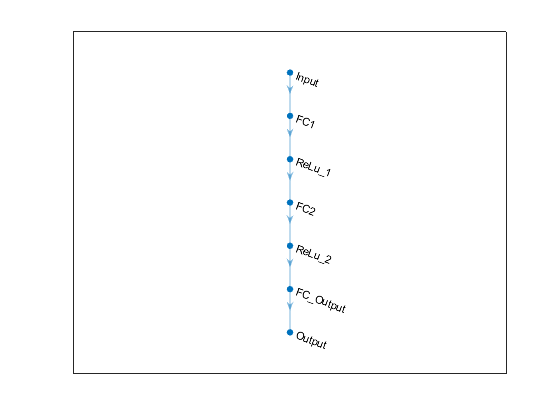

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:07 |       970.15 |       965.62 |  470593.6875 |  466206.5938 |          0.0100 |


|       1 |          41 |       00:00:08 |       613.25 |       601.24 |  188040.1719 |  180743.6250 |          0.0100 |


|       2 |          50 |       00:00:08 |       523.30 |              |  136921.9375 |              |          0.0100 |


|       2 |          82 |       00:00:09 |       340.89 |       426.64 |   58104.2773 |   91011.7188 |          0.0100 |


|       3 |         100 |       00:00:10 |       511.58 |              |  130856.2266 |              |          0.0100 |


|       3 |         123 |       00:00:10 |       419.28 |       413.44 |   87899.3281 |   85467.3438 |          0.0100 |


|       4 |         150 |       00:00:11 |       391.79 |              |   76751.4375 |              |          0.0100 |


|       4 |         164 |       00:00:11 |       428.11 |       409.11 |   91640.7188 |   83684.9375 |          0.0100 |


|       5 |         200 |       00:00:12 |       359.30 |              |   64546.4531 |              |          0.0100 |


|       5 |         205 |       00:00:12 |       394.20 |       405.16 |   77695.8359 |   82075.9922 |          0.0100 |


|       6 |         246 |       00:00:13 |       397.88 |       404.59 |   79155.8984 |   81846.2266 |          0.0100 |


|       7 |         250 |       00:00:13 |       485.74 |              |  117972.0781 |              |          0.0100 |


|       7 |         287 |       00:00:14 |       438.77 |       396.56 |   96257.5313 |   78629.0859 |          0.0100 |


|       8 |         300 |       00:00:15 |       457.51 |              |  104658.8984 |              |          0.0100 |


|       8 |         328 |       00:00:15 |       413.57 |       397.84 |   85519.9375 |   79140.1563 |          0.0100 |


|       9 |         350 |       00:00:15 |       386.43 |              |   74665.6172 |              |          0.0100 |


|       9 |         369 |       00:00:16 |       313.14 |       393.78 |   49028.8047 |   77533.2734 |          0.0100 |


|      10 |         400 |       00:00:17 |       451.56 |              |  101955.1094 |              |          0.0100 |


|      10 |         410 |       00:00:18 |       361.47 |       390.89 |   65331.1797 |   76396.2109 |          0.0100 |


|      11 |         450 |       00:00:19 |       445.26 |              |   99128.3125 |              |          0.0100 |


|      11 |         451 |       00:00:19 |       442.20 |       392.22 |   97769.4844 |   76918.2891 |          0.0100 |


|      12 |         492 |       00:00:20 |       429.15 |       388.63 |   92086.3438 |   75518.1406 |          0.0100 |


|      13 |         500 |       00:00:20 |       390.53 |              |   76256.9766 |              |          0.0100 |


|      13 |         533 |       00:00:21 |       315.01 |       385.26 |   49614.5820 |   74211.9688 |          0.0100 |


|      14 |         550 |       00:00:21 |       362.37 |              |   65654.2969 |              |          0.0100 |


|      14 |         574 |       00:00:22 |       347.29 |       384.84 |   60306.3906 |   74049.1797 |          0.0100 |


|      15 |         600 |       00:00:22 |       328.48 |              |   53950.6133 |              |          0.0100 |


|      15 |         615 |       00:00:23 |       338.10 |       381.51 |   57155.3984 |   72776.6641 |          0.0100 |


|      16 |         650 |       00:00:24 |       324.23 |              |   52562.5391 |              |          0.0100 |


|      16 |         656 |       00:00:24 |       327.84 |       378.99 |   53739.6016 |   71816.8906 |          0.0100 |


|      17 |         697 |       00:00:25 |       316.44 |       380.15 |   50068.6992 |   72257.8203 |          0.0100 |


|      18 |         700 |       00:00:25 |       402.47 |              |   80990.9531 |              |          0.0100 |


|      18 |         738 |       00:00:26 |       478.44 |       375.27 |  114451.6328 |   70412.6797 |          0.0100 |


|      19 |         750 |       00:00:26 |       366.02 |              |   66984.3438 |              |          0.0100 |


|      19 |         779 |       00:00:27 |       309.11 |       371.52 |   47774.2188 |   69012.5078 |          0.0100 |


|      20 |         800 |       00:00:27 |       411.00 |              |   84461.0625 |              |          0.0100 |


|      20 |         820 |       00:00:28 |       284.75 |       367.18 |   40541.2266 |   67409.4453 |          0.0100 |


|      21 |         850 |       00:00:28 |       308.85 |              |   47693.1719 |              |          0.0100 |


|      21 |         861 |       00:00:29 |       400.47 |       364.94 |   80186.1406 |   66590.7813 |          0.0100 |


|      22 |         900 |       00:00:30 |       342.11 |              |   58517.9805 |              |          0.0100 |


|      22 |         902 |       00:00:30 |       284.63 |       362.60 |   40507.0313 |   65740.2578 |          0.0100 |


|      23 |         943 |       00:00:31 |       449.53 |       366.51 |  101040.4609 |   67164.5313 |          0.0100 |


|      24 |         950 |       00:00:31 |       240.15 |              |   28835.8457 |              |          0.0100 |


|      24 |         984 |       00:00:32 |       218.50 |       356.09 |   23871.1094 |   63401.3789 |          0.0100 |


|      25 |        1000 |       00:00:32 |       249.74 |              |   31185.9258 |              |          0.0100 |


|      25 |        1025 |       00:00:33 |       389.19 |       353.17 |   75734.5859 |   62362.8242 |          0.0100 |


|      26 |        1050 |       00:00:33 |       444.39 |              |   98739.9219 |              |          0.0100 |


|      26 |        1066 |       00:00:34 |       431.47 |       349.66 |   93084.6250 |   61131.7109 |          0.0100 |


|      27 |        1100 |       00:00:35 |       336.61 |              |   56652.1055 |              |          0.0100 |


|      27 |        1107 |       00:00:35 |       335.47 |       347.94 |   56270.9883 |   60529.5078 |          0.0100 |


|      28 |        1148 |       00:00:36 |       330.19 |       348.32 |   54511.4492 |   60664.5078 |          0.0100 |


|      29 |        1150 |       00:00:36 |       251.54 |              |   31635.1387 |              |          0.0100 |


|      29 |        1189 |       00:00:36 |       310.13 |       347.68 |   48089.3828 |   60441.2383 |          0.0100 |


|      30 |        1200 |       00:00:37 |       294.37 |              |   43327.0313 |              |          0.0100 |


|      30 |        1230 |       00:00:37 |       293.08 |       342.96 |   42949.1758 |   58809.3320 |          0.0100 |


|      31 |        1250 |       00:00:38 |       286.55 |              |   41055.5039 |              |          0.0075 |


|      31 |        1271 |       00:00:38 |       326.38 |       344.96 |   53263.5313 |   59497.0586 |          0.0075 |


|      32 |        1300 |       00:00:39 |       303.48 |              |   46050.5938 |              |          0.0075 |


|      32 |        1312 |       00:00:39 |       312.51 |       347.08 |   48831.0547 |   60230.8125 |          0.0075 |


|      33 |        1350 |       00:00:40 |       347.02 |              |   60209.7617 |              |          0.0075 |


|      33 |        1353 |       00:00:41 |       245.92 |       344.37 |   30238.7734 |   59294.4648 |          0.0075 |


|      34 |        1394 |       00:00:42 |       264.02 |       339.94 |   34853.2188 |   57780.6445 |          0.0075 |


|      35 |        1400 |       00:00:42 |       318.00 |              |   50562.7148 |              |          0.0075 |


|      35 |        1435 |       00:00:43 |       329.95 |       336.99 |   54434.8594 |   56781.7031 |          0.0075 |


|      36 |        1450 |       00:00:43 |       298.03 |              |   44412.1250 |              |          0.0075 |


|      36 |        1476 |       00:00:44 |       345.65 |       336.14 |   59737.1680 |   56495.8320 |          0.0075 |


|      37 |        1500 |       00:00:45 |       316.75 |              |   50166.5000 |              |          0.0075 |


|      37 |        1517 |       00:00:45 |       270.41 |       341.68 |   36561.2813 |   58373.3477 |          0.0075 |


|      38 |        1550 |       00:00:46 |       336.94 |              |   56765.5703 |              |          0.0075 |


|      38 |        1558 |       00:00:46 |       251.61 |       337.66 |   31654.2695 |   57005.9023 |          0.0075 |


|      39 |        1599 |       00:00:47 |       291.62 |       336.28 |   42519.9883 |   56542.4180 |          0.0075 |


|      40 |        1600 |       00:00:47 |       329.24 |              |   54198.9688 |              |          0.0075 |


|      40 |        1640 |       00:00:48 |       250.48 |       334.52 |   31369.6543 |   55950.5664 |          0.0075 |


|      41 |        1650 |       00:00:48 |       234.74 |              |   27550.4316 |              |          0.0075 |


|      41 |        1681 |       00:00:49 |       245.35 |       338.33 |   30097.4297 |   57232.3789 |          0.0075 |


|      42 |        1700 |       00:00:49 |       322.76 |              |   52087.7266 |              |          0.0075 |


|      42 |        1722 |       00:00:50 |       254.41 |       333.15 |   32361.9375 |   55494.4414 |          0.0075 |


|      43 |        1750 |       00:00:51 |       204.68 |              |   20946.7617 |              |          0.0075 |


|      43 |        1763 |       00:00:51 |       300.72 |       332.54 |   45217.6211 |   55292.8711 |          0.0075 |


|      44 |        1800 |       00:00:52 |       354.63 |              |   62881.0703 |              |          0.0075 |


|      44 |        1804 |       00:00:52 |       343.61 |       335.21 |   59032.8594 |   56181.4922 |          0.0075 |


|      45 |        1845 |       00:00:53 |       286.85 |       336.78 |   41142.7305 |   56710.9414 |          0.0075 |


|      46 |        1850 |       00:00:53 |       243.78 |              |   29715.2031 |              |          0.0075 |


|      46 |        1886 |       00:00:54 |       278.55 |       332.79 |   38795.7578 |   55375.1445 |          0.0075 |


|      47 |        1900 |       00:00:55 |       279.70 |              |   39114.6680 |              |          0.0075 |


|      47 |        1927 |       00:00:55 |       378.90 |       332.23 |   71781.6094 |   55189.1680 |          0.0075 |


|      48 |        1950 |       00:00:56 |       178.62 |              |   15952.8242 |              |          0.0075 |


|      48 |        1968 |       00:00:56 |       322.12 |       332.22 |   51881.0938 |   55186.6289 |          0.0075 |


|      49 |        2000 |       00:00:57 |       278.56 |              |   38796.7969 |              |          0.0075 |


|      49 |        2009 |       00:00:57 |       308.44 |       330.23 |   47568.2305 |   54525.9297 |          0.0075 |


|      50 |        2050 |       00:00:58 |       309.65 |       327.82 |   47941.5195 |   53732.9141 |          0.0075 |


|      51 |        2091 |       00:00:59 |       291.60 |       326.92 |   42516.2891 |   53438.1992 |          0.0075 |


|      52 |        2100 |       00:00:59 |       295.22 |              |   43577.6250 |              |          0.0075 |


|      52 |        2132 |       00:01:00 |       172.60 |       328.42 |   14895.7861 |   53929.9219 |          0.0075 |


|      53 |        2150 |       00:01:00 |       285.70 |              |   40812.3672 |              |          0.0075 |


|      53 |        2173 |       00:01:01 |       183.00 |       326.99 |   16744.2500 |   53459.8867 |          0.0075 |


|      54 |        2200 |       00:01:02 |       210.74 |              |   22205.8652 |              |          0.0075 |


|      54 |        2214 |       00:01:02 |       392.52 |       323.01 |   77035.2578 |   52168.2383 |          0.0075 |


|      55 |        2250 |       00:01:03 |       320.65 |              |   51407.3359 |              |          0.0075 |


|      55 |        2255 |       00:01:03 |       308.24 |       323.41 |   47506.6875 |   52296.0352 |          0.0075 |


|      56 |        2296 |       00:01:04 |       327.12 |       325.18 |   53502.3750 |   52870.4609 |          0.0075 |


|      57 |        2300 |       00:01:04 |       261.06 |              |   34075.7344 |              |          0.0075 |


|      57 |        2337 |       00:01:05 |       306.64 |       322.13 |   47013.0117 |   51884.3789 |          0.0075 |


|      58 |        2350 |       00:01:05 |       322.62 |              |   52041.8867 |              |          0.0075 |


|      58 |        2378 |       00:01:06 |       333.12 |       326.56 |   55485.1797 |   53320.4336 |          0.0075 |


|      59 |        2400 |       00:01:07 |       341.21 |              |   58212.7578 |              |          0.0075 |


|      59 |        2419 |       00:01:07 |       251.02 |       318.02 |   31505.7246 |   50567.8711 |          0.0075 |


|      60 |        2450 |       00:01:08 |       255.32 |              |   32593.8262 |              |          0.0075 |


|      60 |        2460 |       00:01:08 |       231.42 |       325.47 |   26778.7559 |   52965.3516 |          0.0075 |


|      61 |        2500 |       00:01:09 |       284.67 |              |   40518.0703 |              |          0.0056 |


|      61 |        2501 |       00:01:09 |       278.01 |       316.86 |   38645.1914 |   50198.8828 |          0.0056 |


|      62 |        2542 |       00:01:10 |       317.56 |       315.09 |   50420.6680 |   49641.6719 |          0.0056 |


|      63 |        2550 |       00:01:10 |       273.42 |              |   37379.1836 |              |          0.0056 |


|      63 |        2583 |       00:01:11 |       340.29 |       317.50 |   57900.2500 |   50402.8281 |          0.0056 |


|      64 |        2600 |       00:01:11 |       288.01 |              |   41475.7578 |              |          0.0056 |


|      64 |        2624 |       00:01:13 |       326.54 |       316.40 |   53315.1484 |   50053.1406 |          0.0056 |


|      65 |        2650 |       00:01:13 |       307.36 |              |   47234.2188 |              |          0.0056 |


|      65 |        2665 |       00:01:13 |       271.18 |       315.53 |   36769.0781 |   49778.5859 |          0.0056 |


|      66 |        2700 |       00:01:14 |       300.33 |              |   45098.6914 |              |          0.0056 |


|      66 |        2706 |       00:01:15 |       222.29 |       313.27 |   24705.7734 |   49069.7070 |          0.0056 |


|      67 |        2747 |       00:01:16 |       326.23 |       312.34 |   53212.8828 |   48777.3047 |          0.0056 |


|      68 |        2750 |       00:01:16 |       228.48 |              |   26100.7012 |              |          0.0056 |


|      68 |        2788 |       00:01:17 |       219.87 |       317.45 |   24171.0898 |   50386.7617 |          0.0056 |


|      69 |        2800 |       00:01:17 |       296.47 |              |   43946.8125 |              |          0.0056 |


|      69 |        2829 |       00:01:18 |       271.61 |       311.91 |   36884.9297 |   48643.3477 |          0.0056 |


|      70 |        2850 |       00:01:18 |       260.28 |              |   33871.5742 |              |          0.0056 |


|      70 |        2870 |       00:01:19 |       328.08 |       314.22 |   53819.2734 |   49365.5742 |          0.0056 |


|      71 |        2900 |       00:01:20 |       251.05 |              |   31513.8867 |              |          0.0056 |


|      71 |        2911 |       00:01:20 |       259.03 |       311.42 |   33549.1719 |   48492.1406 |          0.0056 |


|      72 |        2950 |       00:01:21 |       222.64 |              |   24783.8242 |              |          0.0056 |


|      72 |        2952 |       00:01:21 |       236.00 |       308.82 |   27847.0273 |   47684.8555 |          0.0056 |


|      73 |        2993 |       00:01:22 |       286.40 |       308.04 |   41012.2891 |   47442.8555 |          0.0056 |


|      74 |        3000 |       00:01:22 |       223.30 |              |   24931.6309 |              |          0.0056 |


|      74 |        3034 |       00:01:23 |       295.31 |       309.48 |   43603.3359 |   47889.5195 |          0.0056 |


|      75 |        3050 |       00:01:23 |       222.28 |              |   24704.4395 |              |          0.0056 |


|      75 |        3075 |       00:01:24 |       293.58 |       309.00 |   43094.0938 |   47739.9766 |          0.0056 |


|      76 |        3100 |       00:01:25 |       240.93 |              |   29024.6406 |              |          0.0056 |


|      76 |        3116 |       00:01:25 |       318.09 |       313.22 |   50589.0977 |   49054.5156 |          0.0056 |


|      77 |        3150 |       00:01:26 |       278.02 |              |   38648.8672 |              |          0.0056 |


|      77 |        3157 |       00:01:26 |       255.36 |       307.60 |   32603.1875 |   47310.2148 |          0.0056 |


|      78 |        3198 |       00:01:27 |       192.29 |       305.31 |   18487.8281 |   46606.6836 |          0.0056 |


|      79 |        3200 |       00:01:27 |       266.92 |              |   35623.9297 |              |          0.0056 |


|      79 |        3239 |       00:01:28 |       213.32 |       307.74 |   22752.5352 |   47351.3477 |          0.0056 |


|      80 |        3250 |       00:01:28 |       229.55 |              |   26347.4551 |              |          0.0056 |


|      80 |        3280 |       00:01:29 |       306.37 |       302.77 |   46929.8906 |   45835.8477 |          0.0056 |


|      81 |        3300 |       00:01:29 |       242.98 |              |   29519.7813 |              |          0.0056 |


|      81 |        3321 |       00:01:30 |       252.90 |       303.46 |   31980.2402 |   46043.6016 |          0.0056 |


|      82 |        3350 |       00:01:31 |       270.72 |              |   36643.7266 |              |          0.0056 |


|      82 |        3362 |       00:01:31 |       244.08 |       300.62 |   29788.2031 |   45184.7500 |          0.0056 |


|      83 |        3400 |       00:01:32 |       281.80 |              |   39704.9688 |              |          0.0056 |


|      83 |        3403 |       00:01:32 |       250.70 |       307.44 |   31424.1406 |   47261.1641 |          0.0056 |


|      84 |        3444 |       00:01:33 |       208.55 |       303.87 |   21745.9844 |   46168.0000 |          0.0056 |


|      85 |        3450 |       00:01:33 |       281.70 |              |   39677.2578 |              |          0.0056 |


|      85 |        3485 |       00:01:34 |       227.55 |       300.70 |   25888.7773 |   45209.2305 |          0.0056 |


|      86 |        3500 |       00:01:34 |       234.67 |              |   27533.9941 |              |          0.0056 |


|      86 |        3526 |       00:01:35 |       255.98 |       299.67 |   32761.8555 |   44901.4570 |          0.0056 |


|      87 |        3550 |       00:01:35 |       202.94 |              |   20591.8086 |              |          0.0056 |


|      87 |        3567 |       00:01:36 |       260.52 |       298.35 |   33935.9727 |   44507.4375 |          0.0056 |


|      88 |        3600 |       00:01:36 |       299.25 |              |   44775.5586 |              |          0.0056 |


|      88 |        3608 |       00:01:36 |       221.06 |       298.61 |   24434.0410 |   44583.0078 |          0.0056 |


|      89 |        3649 |       00:01:37 |       252.87 |       296.06 |   31971.2480 |   43824.3516 |          0.0056 |


|      90 |        3650 |       00:01:37 |       229.64 |              |   26368.1191 |              |          0.0056 |


|      90 |        3690 |       00:01:38 |       223.24 |       296.18 |   24917.9160 |   43860.2227 |          0.0056 |


|      91 |        3700 |       00:01:38 |       278.53 |              |   38788.7070 |              |          0.0042 |


|      91 |        3731 |       00:01:39 |       255.26 |       295.04 |   32578.6289 |   43523.1445 |          0.0042 |


|      92 |        3750 |       00:01:39 |       230.19 |              |   26494.1465 |              |          0.0042 |


|      92 |        3772 |       00:01:40 |       248.99 |       293.60 |   30997.0723 |   43100.4570 |          0.0042 |


|      93 |        3800 |       00:01:41 |       287.87 |              |   41434.8203 |              |          0.0042 |


|      93 |        3813 |       00:01:41 |       230.45 |       294.67 |   26553.8750 |   43414.4609 |          0.0042 |


|      94 |        3850 |       00:01:42 |       244.42 |              |   29871.6992 |              |          0.0042 |


|      94 |        3854 |       00:01:42 |       135.49 |       291.59 |    9179.3975 |   42511.8672 |          0.0042 |


|      95 |        3895 |       00:01:43 |       278.95 |       293.90 |   38907.1836 |   43187.3398 |          0.0042 |


|      96 |        3900 |       00:01:43 |       255.81 |              |   32718.9375 |              |          0.0042 |


|      96 |        3936 |       00:01:44 |       255.35 |       293.60 |   32601.9395 |   43101.8008 |          0.0042 |


|      97 |        3950 |       00:01:45 |       273.90 |              |   37511.1445 |              |          0.0042 |


|      97 |        3977 |       00:01:45 |       237.86 |       292.34 |   28289.1094 |   42732.1289 |          0.0042 |


|      98 |        4000 |       00:01:46 |       255.71 |              |   32693.7949 |              |          0.0042 |


|      98 |        4018 |       00:01:46 |       264.15 |       293.10 |   34887.8281 |   42955.1367 |          0.0042 |


|      99 |        4050 |       00:01:47 |       278.25 |              |   38712.4727 |              |          0.0042 |


|      99 |        4059 |       00:01:47 |       254.76 |       290.57 |   32450.3145 |   42214.8594 |          0.0042 |


|     100 |        4100 |       00:01:48 |       239.97 |       291.85 |   28793.0996 |   42589.2305 |          0.0042 |


|     101 |        4141 |       00:01:49 |       236.56 |       295.72 |   27979.9805 |   43724.7734 |          0.0042 |


|     102 |        4150 |       00:01:49 |       270.44 |              |   36567.6328 |              |          0.0042 |


|     102 |        4182 |       00:01:50 |       274.49 |       294.14 |   37672.6445 |   43258.3203 |          0.0042 |


|     103 |        4200 |       00:01:50 |       235.60 |              |   27753.0684 |              |          0.0042 |


|     103 |        4223 |       00:01:51 |       207.19 |       288.44 |   21463.8203 |   41597.5430 |          0.0042 |


|     104 |        4250 |       00:01:51 |       231.09 |              |   26701.9414 |              |          0.0042 |


|     104 |        4264 |       00:01:51 |       296.50 |       290.24 |   43955.7617 |   42118.7734 |          0.0042 |


|     105 |        4300 |       00:01:52 |       247.66 |              |   30667.6035 |              |          0.0042 |


|     105 |        4305 |       00:01:52 |       207.64 |       289.23 |   21556.7363 |   41827.2695 |          0.0042 |


|     106 |        4346 |       00:01:53 |       233.99 |       287.61 |   27376.4141 |   41359.9531 |          0.0042 |


|     107 |        4350 |       00:01:53 |       258.20 |              |   33334.3906 |              |          0.0042 |


|     107 |        4387 |       00:01:54 |       178.13 |       291.47 |   15864.5195 |   42478.4844 |          0.0042 |


|     108 |        4400 |       00:01:55 |       238.76 |              |   28502.3281 |              |          0.0042 |


|     108 |        4428 |       00:01:55 |       298.43 |       288.19 |   44529.8750 |   41527.7266 |          0.0042 |


|     109 |        4450 |       00:01:56 |       244.95 |              |   30000.8008 |              |          0.0042 |


|     109 |        4469 |       00:01:56 |       318.52 |       287.64 |   50727.5547 |   41367.0352 |          0.0042 |


|     110 |        4500 |       00:01:57 |       225.57 |              |   25441.0586 |              |          0.0042 |


|     110 |        4510 |       00:01:57 |       271.90 |       286.98 |   36964.4063 |   41177.8281 |          0.0042 |


|     111 |        4550 |       00:01:58 |       221.92 |              |   24624.3164 |              |          0.0042 |


|     111 |        4551 |       00:01:58 |       180.63 |       289.03 |   16313.7197 |   41768.1172 |          0.0042 |


|     112 |        4592 |       00:01:59 |       198.26 |       285.40 |   19654.1914 |   40727.5273 |          0.0042 |


|     113 |        4600 |       00:01:59 |       216.04 |              |   23336.1758 |              |          0.0042 |


|     113 |        4633 |       00:02:00 |       258.39 |       285.74 |   33383.8164 |   40822.3242 |          0.0042 |


|     114 |        4650 |       00:02:01 |       234.33 |              |   27455.8535 |              |          0.0042 |


|     114 |        4674 |       00:02:01 |       200.37 |       284.38 |   20073.2266 |   40435.4844 |          0.0042 |


|     115 |        4700 |       00:02:02 |       208.09 |              |   21650.7539 |              |          0.0042 |


|     115 |        4715 |       00:02:02 |       220.31 |       285.38 |   24269.1680 |   40720.4219 |          0.0042 |


|     116 |        4750 |       00:02:03 |       211.51 |              |   22369.1914 |              |          0.0042 |


|     116 |        4756 |       00:02:03 |       258.39 |       283.97 |   33383.6953 |   40320.8828 |          0.0042 |


|     117 |        4797 |       00:02:05 |       235.66 |       286.31 |   27767.0449 |   40985.9219 |          0.0042 |


|     118 |        4800 |       00:02:05 |       182.58 |              |   16667.8086 |              |          0.0042 |


|     118 |        4838 |       00:02:06 |       322.28 |       287.32 |   51932.4727 |   41277.3828 |          0.0042 |


|     119 |        4850 |       00:02:06 |       206.96 |              |   21417.1719 |              |          0.0042 |


|     119 |        4879 |       00:02:07 |       181.04 |       284.06 |   16388.6055 |   40345.8359 |          0.0042 |


|     120 |        4900 |       00:02:07 |       235.18 |              |   27655.7051 |              |          0.0042 |


|     120 |        4920 |       00:02:08 |       236.49 |       284.18 |   27963.8438 |   40377.7383 |          0.0042 |


|     121 |        4950 |       00:02:08 |       206.62 |              |   21346.8984 |              |          0.0032 |


|     121 |        4961 |       00:02:08 |       228.60 |       283.12 |   26128.9063 |   40078.2656 |          0.0032 |


|     122 |        5000 |       00:02:09 |       214.48 |              |   22999.8555 |              |          0.0032 |


|     122 |        5002 |       00:02:09 |       290.10 |       284.80 |   42079.5625 |   40556.3594 |          0.0032 |


|     123 |        5043 |       00:02:10 |       201.83 |       283.03 |   20368.0566 |   40052.3711 |          0.0032 |


|     124 |        5050 |       00:02:10 |       167.58 |              |   14041.5430 |              |          0.0032 |


|     124 |        5084 |       00:02:11 |       232.34 |       285.35 |   26991.9316 |   40711.0469 |          0.0032 |


|     125 |        5100 |       00:02:11 |       202.02 |              |   20406.9922 |              |          0.0032 |


|     125 |        5125 |       00:02:12 |       246.76 |       283.29 |   30446.0234 |   40126.0508 |          0.0032 |


|     126 |        5150 |       00:02:12 |       246.53 |              |   30387.3906 |              |          0.0032 |


|     126 |        5166 |       00:02:13 |       245.88 |       281.45 |   30228.2793 |   39607.7109 |          0.0032 |


|     127 |        5200 |       00:02:14 |       257.25 |              |   33089.2500 |              |          0.0032 |


|     127 |        5207 |       00:02:14 |       286.85 |       281.72 |   41141.3594 |   39683.5625 |          0.0032 |


|     128 |        5248 |       00:02:16 |       194.76 |       280.43 |   18965.1875 |   39321.6172 |          0.0032 |


|     129 |        5250 |       00:02:16 |       172.58 |              |   14892.6348 |              |          0.0032 |


|     129 |        5289 |       00:02:17 |       220.49 |       286.12 |   24307.8242 |   40932.8242 |          0.0032 |


|     130 |        5300 |       00:02:17 |       215.46 |              |   23211.0313 |              |          0.0032 |


|     130 |        5330 |       00:02:18 |       218.97 |       281.07 |   23973.1758 |   39500.0469 |          0.0032 |


|     131 |        5350 |       00:02:18 |       243.15 |              |   29560.6680 |              |          0.0032 |


|     131 |        5371 |       00:02:19 |       195.96 |       283.36 |   19199.5898 |   40147.2031 |          0.0032 |


|     132 |        5400 |       00:02:19 |       191.84 |              |   18401.8613 |              |          0.0032 |


|     132 |        5412 |       00:02:20 |       232.11 |       282.59 |   26936.4277 |   39929.9023 |          0.0032 |


|     133 |        5450 |       00:02:20 |       216.88 |              |   23517.8203 |              |          0.0032 |


|     133 |        5453 |       00:02:20 |       200.96 |       280.40 |   20191.6094 |   39311.5273 |          0.0032 |


|     134 |        5494 |       00:02:21 |       195.04 |       281.16 |   19019.6094 |   39526.7891 |          0.0032 |


|     135 |        5500 |       00:02:21 |       278.91 |              |   38895.2539 |              |          0.0032 |


|     135 |        5535 |       00:02:22 |       188.01 |       282.68 |   17674.1113 |   39954.7852 |          0.0032 |


|     136 |        5550 |       00:02:22 |       194.46 |              |   18907.5293 |              |          0.0032 |


|     136 |        5576 |       00:02:23 |       273.28 |       280.18 |   37340.8750 |   39251.4180 |          0.0032 |


|     137 |        5600 |       00:02:24 |       201.74 |              |   20348.8887 |              |          0.0032 |


|     137 |        5617 |       00:02:24 |       216.50 |       280.18 |   23436.6211 |   39250.0859 |          0.0032 |


|     138 |        5650 |       00:02:25 |       151.74 |              |   11512.6650 |              |          0.0032 |


|     138 |        5658 |       00:02:25 |       218.69 |       277.80 |   23913.4375 |   38586.6758 |          0.0032 |


|     139 |        5699 |       00:02:26 |       244.94 |       278.53 |   29998.7520 |   38789.2578 |          0.0032 |


|     140 |        5700 |       00:02:26 |       189.87 |              |   18025.1484 |              |          0.0032 |


|     140 |        5740 |       00:02:27 |       173.30 |       280.44 |   15016.3486 |   39324.6250 |          0.0032 |


|     141 |        5750 |       00:02:27 |       243.58 |              |   29665.1895 |              |          0.0032 |


|     141 |        5781 |       00:02:28 |       233.22 |       280.88 |   27195.4961 |   39446.5859 |          0.0032 |


|     142 |        5800 |       00:02:29 |       207.87 |              |   21604.9336 |              |          0.0032 |


|     142 |        5822 |       00:02:29 |       281.68 |       279.21 |   39671.1406 |   38979.2344 |          0.0032 |


|     143 |        5850 |       00:02:30 |       253.52 |              |   32137.0371 |              |          0.0032 |


|     143 |        5863 |       00:02:31 |       200.84 |       282.67 |   20168.8926 |   39951.0742 |          0.0032 |


|======================================================================================================================|


% Step 4: Deeper network: two hidden layers; 1st has 100 nodes and 2nd has 50
% nodes. ReLu activation after each hidden layer. Same training options as
% before. 

[net_twohiddenlayers, RMSE_train_twohiddenlayers, RMSE_val_twohiddenlayers] = twohiddenlayers(100, 50, scaled_input_train, output_train, scaled_input_val, output_val);

Using a two hidden layer neural net achieved an RMSE of 283. 

ans = '1, 1 start'

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:07 |      1005.34 |       965.65 |  505353.0625 |  466242.0313 |          0.0100 |


|       1 |          41 |       00:00:08 |       546.08 |       531.74 |  149102.6563 |  141372.0625 |          0.0100 |


|       2 |          50 |       00:00:08 |       472.98 |              |  111853.9219 |              |          0.0100 |


|       2 |          82 |       00:00:09 |       462.83 |       421.03 |  107105.9375 |   88633.3203 |          0.0100 |


|       3 |         100 |       00:00:10 |       328.92 |              |   54093.4805 |              |          0.0100 |


|       3 |         123 |       00:00:10 |       353.80 |       415.92 |   62588.1914 |   86494.6953 |          0.0100 |


|       4 |         150 |       00:00:11 |       408.06 |              |   83255.3672 |              |          0.0100 |


|       4 |         164 |       00:00:11 |       413.63 |       405.27 |   85545.7031 |   82120.4844 |          0.0100 |


|       5 |         200 |       00:00:12 |       403.56 |              |   81429.7969 |              |          0.0100 |


|       5 |         205 |       00:00:12 |       395.64 |       401.40 |   78264.9531 |   80559.9609 |          0.0100 |


|       6 |         246 |       00:00:13 |       466.77 |       397.30 |  108935.5781 |   78925.5156 |          0.0100 |


|       7 |         250 |       00:00:14 |       374.55 |              |   70142.5547 |              |          0.0100 |


|       7 |         287 |       00:00:14 |       445.07 |       398.81 |   99044.7422 |   79524.5703 |          0.0100 |


|       8 |         300 |       00:00:15 |       487.28 |              |  118720.0313 |              |          0.0100 |


|       8 |         328 |       00:00:15 |       319.45 |       394.86 |   51023.4727 |   77958.6016 |          0.0100 |


|       9 |         350 |       00:00:16 |       319.32 |              |   50982.9531 |              |          0.0100 |


|       9 |         369 |       00:00:17 |       328.52 |       396.71 |   53964.3281 |   78689.5781 |          0.0100 |


|      10 |         400 |       00:00:18 |       312.58 |              |   48854.5781 |              |          0.0100 |


|      10 |         410 |       00:00:18 |       311.28 |       393.64 |   48448.1055 |   77474.5703 |          0.0100 |


|      11 |         450 |       00:00:19 |       301.80 |              |   45542.7813 |              |          0.0100 |


|      11 |         451 |       00:00:19 |       334.45 |       389.57 |   55927.7227 |   75883.9609 |          0.0100 |


|      12 |         492 |       00:00:20 |       386.21 |       389.22 |   74580.7656 |   75744.7500 |          0.0100 |


|      13 |         500 |       00:00:20 |       489.26 |              |  119687.5625 |              |          0.0100 |


|      13 |         533 |       00:00:21 |       363.80 |       385.04 |   66176.8984 |   74127.7031 |          0.0100 |


|      14 |         550 |       00:00:21 |       406.82 |              |   82751.9688 |              |          0.0100 |


|      14 |         574 |       00:00:22 |       296.72 |       385.97 |   44022.5938 |   74486.8047 |          0.0100 |


|      15 |         600 |       00:00:23 |       342.46 |              |   58638.9609 |              |          0.0100 |


|      15 |         615 |       00:00:23 |       344.09 |       382.28 |   59197.9297 |   73070.3594 |          0.0100 |


|      16 |         650 |       00:00:24 |       326.15 |              |   53188.0430 |              |          0.0100 |


|      16 |         656 |       00:00:24 |       357.73 |       380.51 |   63985.5234 |   72394.5859 |          0.0100 |


|      17 |         697 |       00:00:25 |       392.34 |       381.60 |   76963.9297 |   72810.0234 |          0.0100 |


|      18 |         700 |       00:00:25 |       284.93 |              |   40593.0508 |              |          0.0100 |


|      18 |         738 |       00:00:27 |       336.67 |       378.47 |   56672.4922 |   71618.5781 |          0.0100 |


|      19 |         750 |       00:00:27 |       386.37 |              |   74642.0469 |              |          0.0100 |


|      19 |         779 |       00:00:28 |       388.61 |       373.10 |   75509.1875 |   69603.5000 |          0.0100 |


|      20 |         800 |       00:00:29 |       371.13 |              |   68868.0156 |              |          0.0100 |


|      20 |         820 |       00:00:29 |       247.15 |       368.53 |   30542.1836 |   67906.0625 |          0.0100 |


|      21 |         850 |       00:00:30 |       327.02 |              |   53469.4844 |              |          0.0100 |


|      21 |         861 |       00:00:30 |       299.45 |       366.70 |   44836.0977 |   67232.7813 |          0.0100 |


|      22 |         900 |       00:00:31 |       434.32 |              |   94317.6250 |              |          0.0100 |


|      22 |         902 |       00:00:31 |       320.52 |       363.75 |   51367.9531 |   66158.7031 |          0.0100 |


|      23 |         943 |       00:00:32 |       336.27 |       360.16 |   56537.9805 |   64859.3555 |          0.0100 |


|      24 |         950 |       00:00:32 |       390.10 |              |   76088.5391 |              |          0.0100 |


|      24 |         984 |       00:00:33 |       315.59 |       354.46 |   49799.6953 |   62820.0859 |          0.0100 |


|      25 |        1000 |       00:00:34 |       321.73 |              |   51754.7734 |              |          0.0100 |


|      25 |        1025 |       00:00:35 |       329.66 |       353.29 |   54338.3984 |   62406.6289 |          0.0100 |


|      26 |        1050 |       00:00:35 |       341.75 |              |   58397.0273 |              |          0.0100 |


|      26 |        1066 |       00:00:36 |       382.77 |       350.79 |   73257.6406 |   61526.6367 |          0.0100 |


|      27 |        1100 |       00:00:36 |       302.22 |              |   45668.6250 |              |          0.0100 |


|      27 |        1107 |       00:00:37 |       314.38 |       351.51 |   49418.7539 |   61778.3047 |          0.0100 |


|      28 |        1148 |       00:00:38 |       311.68 |       346.39 |   48573.4922 |   59992.4531 |          0.0100 |


|      29 |        1150 |       00:00:38 |       315.30 |              |   49708.2578 |              |          0.0100 |


|      29 |        1189 |       00:00:39 |       304.25 |       342.50 |   46283.6563 |   58653.8203 |          0.0100 |


|      30 |        1200 |       00:00:39 |       247.59 |              |   30649.5859 |              |          0.0100 |


|      30 |        1230 |       00:00:40 |       291.53 |       340.63 |   42495.1797 |   58013.8008 |          0.0100 |


|      31 |        1250 |       00:00:41 |       264.54 |              |   34991.3242 |              |          0.0075 |


|      31 |        1271 |       00:00:41 |       314.57 |       338.46 |   49476.8359 |   57279.0039 |          0.0075 |


|      32 |        1300 |       00:00:42 |       235.87 |              |   27817.8672 |              |          0.0075 |


|      32 |        1312 |       00:00:42 |       352.05 |       338.79 |   61970.5156 |   57387.7344 |          0.0075 |


|      33 |        1350 |       00:00:43 |       354.36 |              |   62785.1484 |              |          0.0075 |


|      33 |        1353 |       00:00:43 |       306.93 |       340.07 |   47102.5547 |   57824.7773 |          0.0075 |


|      34 |        1394 |       00:00:44 |       214.87 |       336.94 |   23084.5430 |   56764.6641 |          0.0075 |


|      35 |        1400 |       00:00:44 |       327.41 |              |   53600.0469 |              |          0.0075 |


|      35 |        1435 |       00:00:46 |       383.83 |       337.52 |   73663.4531 |   56960.4531 |          0.0075 |


|      36 |        1450 |       00:00:46 |       253.17 |              |   32048.6836 |              |          0.0075 |


|      36 |        1476 |       00:00:47 |       309.19 |       335.51 |   47799.0078 |   56283.5586 |          0.0075 |


|      37 |        1500 |       00:00:48 |       321.50 |              |   51680.4453 |              |          0.0075 |


|      37 |        1517 |       00:00:48 |       311.05 |       332.97 |   48376.7461 |   55434.0273 |          0.0075 |


|      38 |        1550 |       00:00:49 |       277.32 |              |   38453.9375 |              |          0.0075 |


|      38 |        1558 |       00:00:49 |       317.19 |       332.05 |   50303.7422 |   55128.4336 |          0.0075 |


|      39 |        1599 |       00:00:50 |       318.56 |       334.50 |   50740.2461 |   55945.9961 |          0.0075 |


|      40 |        1600 |       00:00:50 |       283.99 |              |   40324.6563 |              |          0.0075 |


|      40 |        1640 |       00:00:51 |       261.68 |       329.94 |   34237.2969 |   54430.7930 |          0.0075 |


|      41 |        1650 |       00:00:51 |       310.35 |              |   48158.1094 |              |          0.0075 |


|      41 |        1681 |       00:00:52 |       232.94 |       329.21 |   27131.1387 |   54189.2617 |          0.0075 |


|      42 |        1700 |       00:00:52 |       272.20 |              |   37046.8438 |              |          0.0075 |


|      42 |        1722 |       00:00:53 |       311.18 |       333.71 |   48417.4922 |   55680.6094 |          0.0075 |


|      43 |        1750 |       00:00:54 |       342.87 |              |   58778.3359 |              |          0.0075 |


|      43 |        1763 |       00:00:55 |       269.77 |       328.36 |   36388.1445 |   53910.8398 |          0.0075 |


|      44 |        1800 |       00:00:55 |       267.02 |              |   35648.9375 |              |          0.0075 |


|      44 |        1804 |       00:00:55 |       315.01 |       331.98 |   49616.5078 |   55106.1875 |          0.0075 |


|      45 |        1845 |       00:00:56 |       312.28 |       329.04 |   48758.0625 |   54132.3281 |          0.0075 |


|      46 |        1850 |       00:00:56 |       348.68 |              |   60787.6328 |              |          0.0075 |


|      46 |        1886 |       00:00:58 |       332.39 |       326.28 |   55240.0117 |   53228.9102 |          0.0075 |


|      47 |        1900 |       00:00:58 |       278.25 |              |   38711.7617 |              |          0.0075 |


|      47 |        1927 |       00:00:58 |       262.76 |       323.67 |   34520.5430 |   52381.5352 |          0.0075 |


|      48 |        1950 |       00:00:59 |       236.81 |              |   28039.1426 |              |          0.0075 |


|      48 |        1968 |       00:00:59 |       375.90 |       322.69 |   70651.5547 |   52062.8516 |          0.0075 |


|      49 |        2000 |       00:01:00 |       292.05 |              |   42646.4258 |              |          0.0075 |


|      49 |        2009 |       00:01:00 |       261.73 |       328.05 |   34251.2266 |   53806.8789 |          0.0075 |


|      50 |        2050 |       00:01:01 |       244.24 |       323.56 |   29826.2578 |   52345.2188 |          0.0075 |


|      51 |        2091 |       00:01:02 |       256.81 |       321.92 |   32974.5234 |   51816.9453 |          0.0075 |


|      52 |        2100 |       00:01:02 |       241.82 |              |   29238.8574 |              |          0.0075 |


|      52 |        2132 |       00:01:03 |       318.45 |       319.46 |   50704.9531 |   51027.2891 |          0.0075 |


|      53 |        2150 |       00:01:04 |       350.95 |              |   61582.5664 |              |          0.0075 |


|      53 |        2173 |       00:01:05 |       253.14 |       317.75 |   32040.0371 |   50482.0938 |          0.0075 |


|      54 |        2200 |       00:01:06 |       363.06 |              |   65906.5781 |              |          0.0075 |


|      54 |        2214 |       00:01:06 |       296.17 |       317.46 |   43859.3359 |   50390.8711 |          0.0075 |


|      55 |        2250 |       00:01:07 |       270.90 |              |   36694.1641 |              |          0.0075 |


|      55 |        2255 |       00:01:07 |       242.92 |       317.65 |   29505.9629 |   50451.0039 |          0.0075 |


|      56 |        2296 |       00:01:08 |       331.77 |       316.47 |   55037.0313 |   50075.2266 |          0.0075 |


|      57 |        2300 |       00:01:08 |       295.76 |              |   43736.3594 |              |          0.0075 |


|      57 |        2337 |       00:01:09 |       330.75 |       314.13 |   54699.0156 |   49340.3008 |          0.0075 |


|      58 |        2350 |       00:01:09 |       264.39 |              |   34951.9102 |              |          0.0075 |


|      58 |        2378 |       00:01:10 |       234.42 |       316.46 |   27476.6426 |   50072.8516 |          0.0075 |


|      59 |        2400 |       00:01:10 |       202.78 |              |   20559.4961 |              |          0.0075 |


|      59 |        2419 |       00:01:11 |       251.31 |       314.22 |   31577.5273 |   49366.3086 |          0.0075 |


|      60 |        2450 |       00:01:11 |       312.32 |              |   48772.3633 |              |          0.0075 |


|      60 |        2460 |       00:01:11 |       338.08 |       314.36 |   57149.5234 |   49410.6563 |          0.0075 |


|      61 |        2500 |       00:01:12 |       250.54 |              |   31385.3711 |              |          0.0056 |


|      61 |        2501 |       00:01:12 |       248.89 |       312.17 |   30973.4023 |   48725.7461 |          0.0056 |


|      62 |        2542 |       00:01:13 |       266.63 |       314.95 |   35544.5156 |   49596.5586 |          0.0056 |


|      63 |        2550 |       00:01:13 |       237.99 |              |   28318.9844 |              |          0.0056 |


|      63 |        2583 |       00:01:14 |       290.28 |       311.06 |   42130.6836 |   48377.8359 |          0.0056 |


|      64 |        2600 |       00:01:14 |       270.24 |              |   36515.9883 |              |          0.0056 |


|      64 |        2624 |       00:01:16 |       310.09 |       315.99 |   48077.9453 |   49925.3477 |          0.0056 |


|      65 |        2650 |       00:01:16 |       344.18 |              |   59230.6641 |              |          0.0056 |


|      65 |        2665 |       00:01:17 |       271.62 |       312.43 |   36887.9219 |   48806.6523 |          0.0056 |


|      66 |        2700 |       00:01:18 |       278.21 |              |   38699.4805 |              |          0.0056 |


|      66 |        2706 |       00:01:18 |       328.52 |       313.02 |   53964.0195 |   48989.3320 |          0.0056 |


|      67 |        2747 |       00:01:19 |       250.91 |       307.91 |   31479.1387 |   47405.7969 |          0.0056 |


|      68 |        2750 |       00:01:19 |       213.02 |              |   22688.0137 |              |          0.0056 |


|      68 |        2788 |       00:01:20 |       241.88 |       308.10 |   29252.3027 |   47462.9766 |          0.0056 |


|      69 |        2800 |       00:01:20 |       255.44 |              |   32625.5977 |              |          0.0056 |


|      69 |        2829 |       00:01:21 |       177.86 |       307.55 |   15817.3154 |   47293.7305 |          0.0056 |


|      70 |        2850 |       00:01:21 |       302.18 |              |   45656.2383 |              |          0.0056 |


|      70 |        2870 |       00:01:22 |       268.67 |       307.01 |   36090.9219 |   47129.0625 |          0.0056 |


|      71 |        2900 |       00:01:22 |       317.90 |              |   50530.4414 |              |          0.0056 |


|      71 |        2911 |       00:01:23 |       253.43 |       304.65 |   32112.7480 |   46406.7031 |          0.0056 |


|      72 |        2950 |       00:01:24 |       301.23 |              |   45368.8555 |              |          0.0056 |


|      72 |        2952 |       00:01:24 |       177.78 |       304.97 |   15802.8516 |   46503.2930 |          0.0056 |


|      73 |        2993 |       00:01:25 |       204.95 |       304.69 |   21003.0547 |   46416.8320 |          0.0056 |


|      74 |        3000 |       00:01:25 |       238.38 |              |   28413.5879 |              |          0.0056 |


|      74 |        3034 |       00:01:26 |       308.53 |       303.70 |   47596.2109 |   46115.4023 |          0.0056 |


|      75 |        3050 |       00:01:27 |       253.52 |              |   32136.3945 |              |          0.0056 |


|      75 |        3075 |       00:01:28 |       243.82 |       307.18 |   29724.5078 |   47179.1172 |          0.0056 |


|      76 |        3100 |       00:01:28 |       272.91 |              |   37241.1289 |              |          0.0056 |


|      76 |        3116 |       00:01:29 |       313.62 |       303.32 |   49179.2188 |   46001.8594 |          0.0056 |


|      77 |        3150 |       00:01:29 |       297.15 |              |   44148.2344 |              |          0.0056 |


|      77 |        3157 |       00:01:30 |       308.35 |       304.24 |   47538.3477 |   46281.7383 |          0.0056 |


|      78 |        3198 |       00:01:31 |       323.66 |       300.65 |   52377.5586 |   45195.4570 |          0.0056 |


|      79 |        3200 |       00:01:31 |       189.51 |              |   17956.2441 |              |          0.0056 |


|      79 |        3239 |       00:01:32 |       315.12 |       304.79 |   49650.2969 |   46447.6406 |          0.0056 |


|      80 |        3250 |       00:01:32 |       310.73 |              |   48275.0820 |              |          0.0056 |


|      80 |        3280 |       00:01:33 |       365.20 |       301.50 |   66686.0000 |   45451.4961 |          0.0056 |


|      81 |        3300 |       00:01:33 |       243.61 |              |   29671.7188 |              |          0.0056 |


|      81 |        3321 |       00:01:34 |       278.92 |       300.93 |   38898.0977 |   45279.4844 |          0.0056 |


|      82 |        3350 |       00:01:34 |       313.77 |              |   49225.5352 |              |          0.0056 |


|      82 |        3362 |       00:01:35 |       172.04 |       299.96 |   14798.6953 |   44987.5352 |          0.0056 |


|      83 |        3400 |       00:01:35 |       235.13 |              |   27644.0215 |              |          0.0056 |


|      83 |        3403 |       00:01:35 |       261.38 |       308.07 |   34159.0469 |   47452.7969 |          0.0056 |


|      84 |        3444 |       00:01:36 |       251.48 |       309.97 |   31620.7207 |   48041.2695 |          0.0056 |


|      85 |        3450 |       00:01:36 |       203.98 |              |   20803.4219 |              |          0.0056 |


|      85 |        3485 |       00:01:38 |       237.87 |       301.14 |   28290.1367 |   45342.2539 |          0.0056 |


|      86 |        3500 |       00:01:38 |       249.02 |              |   31005.4570 |              |          0.0056 |


|      86 |        3526 |       00:01:39 |       287.33 |       300.27 |   41278.3164 |   45081.1523 |          0.0056 |


|      87 |        3550 |       00:01:40 |       296.16 |              |   43856.6641 |              |          0.0056 |


|      87 |        3567 |       00:01:40 |       253.40 |       298.19 |   32106.3398 |   44458.2266 |          0.0056 |


|      88 |        3600 |       00:01:41 |       193.38 |              |   18697.7461 |              |          0.0056 |


|      88 |        3608 |       00:01:41 |       254.80 |       299.14 |   32460.4160 |   44741.3984 |          0.0056 |


|      89 |        3649 |       00:01:42 |       296.73 |       299.04 |   44025.2031 |   44711.6641 |          0.0056 |


|      90 |        3650 |       00:01:42 |       163.23 |              |   13322.3105 |              |          0.0056 |


|      90 |        3690 |       00:01:43 |       215.50 |       297.36 |   23219.3516 |   44212.3906 |          0.0056 |


|      91 |        3700 |       00:01:43 |       246.91 |              |   30482.2402 |              |          0.0042 |


|      91 |        3731 |       00:01:44 |       273.03 |       296.30 |   37272.7656 |   43896.9258 |          0.0042 |


|      92 |        3750 |       00:01:44 |       239.26 |              |   28623.2188 |              |          0.0042 |


|      92 |        3772 |       00:01:45 |       254.64 |       295.52 |   32421.1250 |   43664.5859 |          0.0042 |


|      93 |        3800 |       00:01:46 |       203.84 |              |   20775.3125 |              |          0.0042 |


|      93 |        3813 |       00:01:46 |       187.38 |       296.87 |   17554.8828 |   44066.0703 |          0.0042 |


|      94 |        3850 |       00:01:47 |       257.09 |              |   33048.5078 |              |          0.0042 |


|      94 |        3854 |       00:01:47 |       183.37 |       296.39 |   16811.5664 |   43922.5234 |          0.0042 |


|      95 |        3895 |       00:01:48 |       278.77 |       296.28 |   38856.0078 |   43890.8867 |          0.0042 |


|      96 |        3900 |       00:01:48 |       199.13 |              |   19825.8926 |              |          0.0042 |


|      96 |        3936 |       00:01:49 |       275.61 |       295.95 |   37980.8789 |   43792.9570 |          0.0042 |


|      97 |        3950 |       00:01:50 |       220.92 |              |   24402.6680 |              |          0.0042 |


|      97 |        3977 |       00:01:50 |       310.53 |       296.80 |   48213.4844 |   44045.0117 |          0.0042 |


|======================================================================================================================|


this_net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'Input'}
    OutputNames: {'Output'}


this_RMSE_train = single
246.3051

this_RMSE_val = single
296.7996

ans = '1, 1 end'

ans = '1, 2 start'

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:06 |       860.62 |       965.74 |  370331.0625 |  466330.5000 |          0.0100 |


|       1 |          41 |       00:00:08 |       428.92 |       536.77 |   91986.5000 |  144062.7969 |          0.0100 |


|       2 |          50 |       00:00:09 |       491.07 |              |  120577.1797 |              |          0.0100 |


|       2 |          82 |       00:00:10 |       391.13 |       422.43 |   76493.1797 |   89223.0156 |          0.0100 |


|       3 |         100 |       00:00:11 |       427.86 |              |   91533.8594 |              |          0.0100 |


|       3 |         123 |       00:00:11 |       338.76 |       409.97 |   57378.6523 |   84038.5703 |          0.0100 |


|       4 |         150 |       00:00:12 |       354.20 |              |   62728.2813 |              |          0.0100 |


|       4 |         164 |       00:00:12 |       264.12 |       403.18 |   34878.9297 |   81275.3516 |          0.0100 |


|       5 |         200 |       00:00:13 |       298.17 |              |   44452.9102 |              |          0.0100 |


|       5 |         205 |       00:00:13 |       338.34 |       400.87 |   57238.6250 |   80348.5000 |          0.0100 |


|       6 |         246 |       00:00:14 |       362.87 |       402.39 |   65837.9688 |   80957.8047 |          0.0100 |


|       7 |         250 |       00:00:15 |       363.06 |              |   65906.1797 |              |          0.0100 |


|       7 |         287 |       00:00:16 |       285.60 |       395.25 |   40782.4336 |   78111.5313 |          0.0100 |


|       8 |         300 |       00:00:16 |       374.98 |              |   70306.7031 |              |          0.0100 |


|       8 |         328 |       00:00:17 |       401.93 |       392.74 |   80774.3828 |   77120.4375 |          0.0100 |


|       9 |         350 |       00:00:18 |       391.79 |              |   76748.2813 |              |          0.0100 |


|       9 |         369 |       00:00:18 |       506.75 |       393.79 |  128397.2344 |   77534.0859 |          0.0100 |


|      10 |         400 |       00:00:20 |       284.54 |              |   40482.3125 |              |          0.0100 |


|      10 |         410 |       00:00:20 |       287.79 |       389.20 |   41411.0234 |   75739.8359 |          0.0100 |


|      11 |         450 |       00:00:21 |       373.21 |              |   69643.0859 |              |          0.0100 |


|      11 |         451 |       00:00:21 |       335.98 |       386.92 |   56442.6211 |   74855.3594 |          0.0100 |


|      12 |         492 |       00:00:22 |       345.56 |       385.23 |   59704.3125 |   74200.1563 |          0.0100 |


|      13 |         500 |       00:00:22 |       334.98 |              |   56106.0859 |              |          0.0100 |


|      13 |         533 |       00:00:23 |       287.07 |       383.09 |   41204.0156 |   73379.2969 |          0.0100 |


|      14 |         550 |       00:00:24 |       372.43 |              |   69351.9531 |              |          0.0100 |


|      14 |         574 |       00:00:25 |       366.96 |       384.00 |   67330.9609 |   73726.9688 |          0.0100 |


|      15 |         600 |       00:00:25 |       337.72 |              |   57026.4219 |              |          0.0100 |


|      15 |         615 |       00:00:26 |       358.53 |       379.13 |   64272.3438 |   71871.3203 |          0.0100 |


|      16 |         650 |       00:00:26 |       289.30 |              |   41847.8359 |              |          0.0100 |


|      16 |         656 |       00:00:26 |       409.75 |       390.94 |   83948.3906 |   76418.4609 |          0.0100 |


|      17 |         697 |       00:00:28 |       502.21 |       376.88 |  126109.2031 |   71018.1250 |          0.0100 |


|      18 |         700 |       00:00:28 |       378.75 |              |   71725.1719 |              |          0.0100 |


|      18 |         738 |       00:00:29 |       360.58 |       374.33 |   65007.4063 |   70059.7188 |          0.0100 |


|      19 |         750 |       00:00:30 |       375.46 |              |   70483.7734 |              |          0.0100 |


|      19 |         779 |       00:00:30 |       394.77 |       372.45 |   77920.8906 |   69361.0156 |          0.0100 |


|      20 |         800 |       00:00:31 |       326.14 |              |   53183.0898 |              |          0.0100 |


|      20 |         820 |       00:00:31 |       271.73 |       370.62 |   36918.7852 |   68680.4453 |          0.0100 |


|      21 |         850 |       00:00:32 |       340.78 |              |   58065.6836 |              |          0.0100 |


|      21 |         861 |       00:00:32 |       279.74 |       366.23 |   39127.9727 |   67063.1016 |          0.0100 |


|      22 |         900 |       00:00:33 |       317.06 |              |   50264.5547 |              |          0.0100 |


|      22 |         902 |       00:00:33 |       310.17 |       366.45 |   48104.2500 |   67142.4531 |          0.0100 |


|      23 |         943 |       00:00:34 |       305.18 |       363.66 |   46566.9766 |   66125.4141 |          0.0100 |


|      24 |         950 |       00:00:34 |       377.90 |              |   71405.2813 |              |          0.0100 |


|      24 |         984 |       00:00:36 |       339.44 |       357.24 |   57610.3398 |   63810.5898 |          0.0100 |


|      25 |        1000 |       00:00:36 |       347.20 |              |   60275.4375 |              |          0.0100 |


|      25 |        1025 |       00:00:37 |       284.70 |       354.35 |   40527.4063 |   62781.9297 |          0.0100 |


|      26 |        1050 |       00:00:38 |       305.41 |              |   46636.9219 |              |          0.0100 |


|      26 |        1066 |       00:00:38 |       397.74 |       350.44 |   79097.7188 |   61404.9063 |          0.0100 |


|      27 |        1100 |       00:00:39 |       410.11 |              |   84096.4922 |              |          0.0100 |


|      27 |        1107 |       00:00:40 |       240.68 |       343.81 |   28964.2266 |   59102.5508 |          0.0100 |


|      28 |        1148 |       00:00:40 |       299.89 |       340.78 |   44968.2031 |   58063.9727 |          0.0100 |


|      29 |        1150 |       00:00:41 |       314.43 |              |   49433.7578 |              |          0.0100 |


|      29 |        1189 |       00:00:42 |       248.82 |       343.21 |   30954.5977 |   58896.7383 |          0.0100 |


|      30 |        1200 |       00:00:42 |       322.15 |              |   51890.1211 |              |          0.0100 |


|      30 |        1230 |       00:00:43 |       291.81 |       334.23 |   42575.8359 |   55856.5117 |          0.0100 |


|      31 |        1250 |       00:00:43 |       306.03 |              |   46827.2227 |              |          0.0075 |


|      31 |        1271 |       00:00:44 |       272.31 |       330.71 |   37075.5859 |   54684.4883 |          0.0075 |


|      32 |        1300 |       00:00:44 |       357.34 |              |   63844.6328 |              |          0.0075 |


|      32 |        1312 |       00:00:44 |       239.04 |       330.58 |   28569.0371 |   54640.8398 |          0.0075 |


|      33 |        1350 |       00:00:45 |       273.31 |              |   37349.2695 |              |          0.0075 |


|      33 |        1353 |       00:00:45 |       293.27 |       326.51 |   43003.3516 |   53304.5703 |          0.0075 |


|      34 |        1394 |       00:00:47 |       326.37 |       330.90 |   53260.1953 |   54747.1328 |          0.0075 |


|      35 |        1400 |       00:00:47 |       312.95 |              |   48968.3633 |              |          0.0075 |


|      35 |        1435 |       00:00:48 |       348.14 |       327.02 |   60600.1445 |   53471.0781 |          0.0075 |


|      36 |        1450 |       00:00:48 |       191.16 |              |   18271.2969 |              |          0.0075 |


|      36 |        1476 |       00:00:50 |       306.08 |       325.80 |   46842.9766 |   53071.2031 |          0.0075 |


|      37 |        1500 |       00:00:50 |       257.67 |              |   33197.9688 |              |          0.0075 |


|      37 |        1517 |       00:00:51 |       225.92 |       322.10 |   25519.3496 |   51873.7070 |          0.0075 |


|      38 |        1550 |       00:00:52 |       292.33 |              |   42727.3320 |              |          0.0075 |


|      38 |        1558 |       00:00:52 |       245.48 |       319.35 |   30131.3555 |   50992.8594 |          0.0075 |


|      39 |        1599 |       00:00:53 |       257.16 |       319.02 |   33066.0352 |   50885.7852 |          0.0075 |


|      40 |        1600 |       00:00:53 |       241.12 |              |   29068.8984 |              |          0.0075 |


|      40 |        1640 |       00:00:55 |       223.21 |       317.38 |   24912.0586 |   50366.4961 |          0.0075 |


|      41 |        1650 |       00:00:55 |       283.66 |              |   40230.7852 |              |          0.0075 |


|      41 |        1681 |       00:00:56 |       274.53 |       315.49 |   37684.1484 |   49767.2813 |          0.0075 |


|      42 |        1700 |       00:00:56 |       260.86 |              |   34024.1680 |              |          0.0075 |


|      42 |        1722 |       00:00:57 |       235.79 |       316.76 |   27798.4824 |   50169.1211 |          0.0075 |


|      43 |        1750 |       00:00:57 |       264.61 |              |   35009.1367 |              |          0.0075 |


|      43 |        1763 |       00:00:58 |       216.70 |       309.34 |   23480.3008 |   47846.7031 |          0.0075 |


|      44 |        1800 |       00:00:58 |       213.12 |              |   22710.8438 |              |          0.0075 |


|      44 |        1804 |       00:00:58 |       260.85 |       310.97 |   34020.8828 |   48351.1914 |          0.0075 |


|      45 |        1845 |       00:01:00 |       293.13 |       314.26 |   42964.0508 |   49379.0273 |          0.0075 |


|      46 |        1850 |       00:01:00 |       355.83 |              |   63309.2617 |              |          0.0075 |


|      46 |        1886 |       00:01:01 |       308.10 |       314.33 |   47461.2852 |   49402.0820 |          0.0075 |


|      47 |        1900 |       00:01:02 |       329.54 |              |   54297.3047 |              |          0.0075 |


|      47 |        1927 |       00:01:02 |       247.27 |       310.72 |   30570.1621 |   48272.8008 |          0.0075 |


|      48 |        1950 |       00:01:03 |       244.32 |              |   29845.8867 |              |          0.0075 |


|      48 |        1968 |       00:01:03 |       249.14 |       309.88 |   31035.7109 |   48013.7031 |          0.0075 |


|======================================================================================================================|


this_net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'Input'}
    OutputNames: {'Output'}


this_RMSE_train = single
269.8378

this_RMSE_val = single
309.8829

ans = '1, 2 end'

ans = '1, 3 start'

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:10 |       827.78 |       965.81 |  342609.9688 |  466393.9063 |          0.0100 |


|       1 |          41 |       00:00:12 |       459.64 |       559.34 |  105635.1328 |  156428.6406 |          0.0100 |


|       2 |          50 |       00:00:12 |       422.64 |              |   89311.7500 |              |          0.0100 |


|       2 |          82 |       00:00:14 |       462.49 |       425.68 |  106948.5625 |   90602.9453 |          0.0100 |


|       3 |         100 |       00:00:15 |       443.27 |              |   98242.4141 |              |          0.0100 |


|       3 |         123 |       00:00:16 |       327.49 |       413.42 |   53625.8359 |   85456.6875 |          0.0100 |


|       4 |         150 |       00:00:17 |       337.39 |              |   56917.0938 |              |          0.0100 |


|       4 |         164 |       00:00:17 |       493.19 |       411.09 |  121619.8125 |   84497.6641 |          0.0100 |


|       5 |         200 |       00:00:19 |       389.24 |              |   75753.6406 |              |          0.0100 |


|       5 |         205 |       00:00:19 |       401.95 |       405.65 |   80783.6328 |   82274.9844 |          0.0100 |


|       6 |         246 |       00:00:21 |       430.66 |       407.29 |   92736.0313 |   82942.9766 |          0.0100 |


|       7 |         250 |       00:00:21 |       376.38 |              |   70831.4531 |              |          0.0100 |


|       7 |         287 |       00:00:23 |       424.57 |       399.37 |   90130.0625 |   79749.1172 |          0.0100 |


|       8 |         300 |       00:00:23 |       416.08 |              |   86561.9375 |              |          0.0100 |


|       8 |         328 |       00:00:25 |       448.35 |       402.25 |  100509.6406 |   80903.1484 |          0.0100 |


|       9 |         350 |       00:00:25 |       398.62 |              |   79447.7188 |              |          0.0100 |


|       9 |         369 |       00:00:26 |       406.18 |       395.82 |   82492.7813 |   78336.5156 |          0.0100 |


|      10 |         400 |       00:00:28 |       339.03 |              |   57471.7539 |              |          0.0100 |


|      10 |         410 |       00:00:28 |       385.32 |       395.44 |   74234.1797 |   78185.5000 |          0.0100 |


|      11 |         450 |       00:00:30 |       363.19 |              |   65954.5391 |              |          0.0100 |


|      11 |         451 |       00:00:30 |       442.97 |       392.33 |   98109.2813 |   76959.6250 |          0.0100 |


|      12 |         492 |       00:00:32 |       414.98 |       391.30 |   86103.2656 |   76557.3672 |          0.0100 |


|      13 |         500 |       00:00:32 |       370.62 |              |   68678.1875 |              |          0.0100 |


|      13 |         533 |       00:00:34 |       378.07 |       388.09 |   71469.2266 |   75307.8047 |          0.0100 |


|      14 |         550 |       00:00:34 |       364.25 |              |   66338.1250 |              |          0.0100 |


|      14 |         574 |       00:00:36 |       379.30 |       391.26 |   71935.6719 |   76543.3516 |          0.0100 |


|      15 |         600 |       00:00:36 |       353.75 |              |   62570.3906 |              |          0.0100 |


|      15 |         615 |       00:00:36 |       388.07 |       385.87 |   75298.3438 |   74447.9375 |          0.0100 |


|      16 |         650 |       00:00:38 |       365.25 |              |   66702.1094 |              |          0.0100 |


|      16 |         656 |       00:00:38 |       445.67 |       387.51 |   99310.1094 |   75083.1172 |          0.0100 |


|      17 |         697 |       00:00:40 |       390.97 |       384.90 |   76430.6484 |   74073.5000 |          0.0100 |


|      18 |         700 |       00:00:40 |       353.50 |              |   62480.7695 |              |          0.0100 |


|      18 |         738 |       00:00:42 |       422.37 |       384.77 |   89196.3750 |   74024.8359 |          0.0100 |


|      19 |         750 |       00:00:42 |       348.85 |              |   60848.0273 |              |          0.0100 |


|      19 |         779 |       00:00:43 |       367.56 |       382.76 |   67550.0000 |   73254.1250 |          0.0100 |


|      20 |         800 |       00:00:45 |       350.95 |              |   61582.0313 |              |          0.0100 |


|      20 |         820 |       00:00:45 |       463.35 |       382.13 |  107347.6094 |   73011.4688 |          0.0100 |


|      21 |         850 |       00:00:46 |       325.85 |              |   53089.3477 |              |          0.0100 |


|      21 |         861 |       00:00:47 |       293.24 |       382.10 |   42994.9922 |   72998.7891 |          0.0100 |


|      22 |         900 |       00:00:48 |       328.23 |              |   53865.9258 |              |          0.0100 |


|      22 |         902 |       00:00:48 |       435.89 |       379.26 |   95002.0469 |   71919.6563 |          0.0100 |


|      23 |         943 |       00:00:50 |       450.72 |       381.24 |  101574.5625 |   72671.4297 |          0.0100 |


|      24 |         950 |       00:00:50 |       374.18 |              |   70004.4531 |              |          0.0100 |


|      24 |         984 |       00:00:51 |       336.85 |       376.68 |   56735.5391 |   70944.1094 |          0.0100 |


|      25 |        1000 |       00:00:51 |       335.40 |              |   56245.4063 |              |          0.0100 |


|      25 |        1025 |       00:00:53 |       462.42 |       378.85 |  106916.3906 |   71762.0625 |          0.0100 |


|      26 |        1050 |       00:00:53 |       375.05 |              |   70331.0469 |              |          0.0100 |


|      26 |        1066 |       00:00:55 |       362.15 |       380.52 |   65575.7656 |   72398.9063 |          0.0100 |


|      27 |        1100 |       00:00:55 |       440.49 |              |   97014.6094 |              |          0.0100 |


|      27 |        1107 |       00:00:56 |       456.98 |       379.33 |  104414.6719 |   71946.5938 |          0.0100 |


|      28 |        1148 |       00:00:57 |       296.49 |       374.68 |   43951.7305 |   70194.0938 |          0.0100 |


|      29 |        1150 |       00:00:58 |       329.24 |              |   54200.6602 |              |          0.0100 |


|      29 |        1189 |       00:00:59 |       313.64 |       375.15 |   49183.6797 |   70366.9531 |          0.0100 |


|      30 |        1200 |       00:01:00 |       359.48 |              |   64611.8359 |              |          0.0100 |


|      30 |        1230 |       00:01:01 |       406.62 |       371.96 |   82669.5859 |   69176.5469 |          0.0100 |


|      31 |        1250 |       00:01:02 |       389.45 |              |   75835.6641 |              |          0.0075 |


|      31 |        1271 |       00:01:03 |       287.46 |       373.81 |   41315.9141 |   69865.8203 |          0.0075 |


|      32 |        1300 |       00:01:04 |       251.34 |              |   31586.9453 |              |          0.0075 |


|      32 |        1312 |       00:01:04 |       302.19 |       371.01 |   45660.0547 |   68822.5000 |          0.0075 |


|      33 |        1350 |       00:01:05 |       415.81 |              |   86447.2031 |              |          0.0075 |


|      33 |        1353 |       00:01:05 |       290.64 |       367.03 |   42235.3906 |   67355.2188 |          0.0075 |


|      34 |        1394 |       00:01:07 |       277.59 |       365.93 |   38529.1211 |   66952.3516 |          0.0075 |


|      35 |        1400 |       00:01:07 |       310.93 |              |   48339.0625 |              |          0.0075 |


|      35 |        1435 |       00:01:09 |       392.96 |       365.97 |   77208.9375 |   66968.7500 |          0.0075 |


|      36 |        1450 |       00:01:09 |       306.97 |              |   47115.7422 |              |          0.0075 |


|      36 |        1476 |       00:01:10 |       354.62 |       363.83 |   62876.9063 |   66186.1328 |          0.0075 |


|      37 |        1500 |       00:01:11 |       323.91 |              |   52460.2188 |              |          0.0075 |


|      37 |        1517 |       00:01:13 |       357.65 |       360.72 |   63955.3516 |   65060.3242 |          0.0075 |


|      38 |        1550 |       00:01:13 |       277.71 |              |   38560.8281 |              |          0.0075 |


|      38 |        1558 |       00:01:14 |       321.67 |       355.15 |   51735.8438 |   63064.5469 |          0.0075 |


|      39 |        1599 |       00:01:15 |       255.88 |       355.93 |   32737.7246 |   63343.2773 |          0.0075 |


|      40 |        1600 |       00:01:16 |       274.14 |              |   37575.3906 |              |          0.0075 |


|      40 |        1640 |       00:01:16 |       397.35 |       350.96 |   78945.3047 |   61586.0313 |          0.0075 |


|      41 |        1650 |       00:01:18 |       243.48 |              |   29640.0742 |              |          0.0075 |


|      41 |        1681 |       00:01:18 |       325.07 |       348.59 |   52834.5469 |   60758.4219 |          0.0075 |


|      42 |        1700 |       00:01:20 |       327.09 |              |   53494.8086 |              |          0.0075 |


|      42 |        1722 |       00:01:21 |       336.09 |       352.57 |   56479.7266 |   62152.7813 |          0.0075 |


|      43 |        1750 |       00:01:22 |       330.44 |              |   54596.1367 |              |          0.0075 |


|      43 |        1763 |       00:01:22 |       269.62 |       347.19 |   36346.2461 |   60270.7109 |          0.0075 |


|      44 |        1800 |       00:01:24 |       383.85 |              |   73670.8906 |              |          0.0075 |


|      44 |        1804 |       00:01:24 |       262.49 |       343.20 |   34450.7930 |   58893.1367 |          0.0075 |


|      45 |        1845 |       00:01:26 |       279.15 |       343.42 |   38961.9141 |   58968.1445 |          0.0075 |


|      46 |        1850 |       00:01:26 |       289.53 |              |   41913.5391 |              |          0.0075 |


|      46 |        1886 |       00:01:28 |       222.59 |       338.16 |   24772.4199 |   57176.1211 |          0.0075 |


|      47 |        1900 |       00:01:28 |       273.12 |              |   37298.5195 |              |          0.0075 |


|      47 |        1927 |       00:01:29 |       293.14 |       335.50 |   42964.3086 |   56280.3750 |          0.0075 |


|      48 |        1950 |       00:01:30 |       274.38 |              |   37640.9063 |              |          0.0075 |


|      48 |        1968 |       00:01:31 |       298.85 |       334.87 |   44654.9453 |   56070.1953 |          0.0075 |


|      49 |        2000 |       00:01:32 |       339.61 |              |   57666.7148 |              |          0.0075 |


|      49 |        2009 |       00:01:33 |       307.31 |       332.36 |   47219.5664 |   55230.7266 |          0.0075 |


|      50 |        2050 |       00:01:33 |       253.50 |       328.14 |   32132.1836 |   53839.4922 |          0.0075 |


|      51 |        2091 |       00:01:35 |       251.36 |       328.02 |   31591.3594 |   53799.4180 |          0.0075 |


|      52 |        2100 |       00:01:37 |       294.50 |              |   43363.8945 |              |          0.0075 |


|      52 |        2132 |       00:01:37 |       306.06 |       325.74 |   46836.2188 |   53054.5234 |          0.0075 |


|      53 |        2150 |       00:01:40 |       286.33 |              |   40993.1172 |              |          0.0075 |


|      53 |        2173 |       00:01:40 |       323.42 |       328.95 |   52299.8281 |   54102.9922 |          0.0075 |


|      54 |        2200 |       00:01:42 |       293.96 |              |   43207.1484 |              |          0.0075 |


|      54 |        2214 |       00:01:42 |       297.64 |       324.44 |   44294.4961 |   52629.1602 |          0.0075 |


|      55 |        2250 |       00:01:44 |       311.99 |              |   48668.2266 |              |          0.0075 |


|      55 |        2255 |       00:01:44 |       264.70 |       320.79 |   35032.4375 |   51453.7148 |          0.0075 |


|      56 |        2296 |       00:01:49 |       253.98 |       320.18 |   32253.3750 |   51256.8398 |          0.0075 |


|      57 |        2300 |       00:01:49 |       314.69 |              |   49515.4922 |              |          0.0075 |


|      57 |        2337 |       00:01:51 |       247.71 |       321.13 |   30680.8711 |   51562.3555 |          0.0075 |


|      58 |        2350 |       00:01:52 |       279.83 |              |   39151.5352 |              |          0.0075 |


|      58 |        2378 |       00:01:53 |       278.14 |       320.45 |   38680.0586 |   51344.8516 |          0.0075 |


|      59 |        2400 |       00:01:54 |       253.10 |              |   32030.9180 |              |          0.0075 |


|      59 |        2419 |       00:01:54 |       342.06 |       317.70 |   58503.7109 |   50466.1367 |          0.0075 |


|      60 |        2450 |       00:01:56 |       312.24 |              |   48746.3281 |              |          0.0075 |


|      60 |        2460 |       00:01:56 |       345.93 |       316.38 |   59834.1641 |   50047.3828 |          0.0075 |


|      61 |        2500 |       00:01:58 |       314.29 |              |   49388.3359 |              |          0.0056 |


|      61 |        2501 |       00:01:58 |       247.52 |       312.87 |   30632.1875 |   48942.7383 |          0.0056 |


|      62 |        2542 |       00:02:00 |       256.84 |       312.86 |   32983.1367 |   48940.6797 |          0.0056 |


|      63 |        2550 |       00:02:00 |       269.91 |              |   36426.6836 |              |          0.0056 |


|      63 |        2583 |       00:02:02 |       313.95 |       312.12 |   49283.2969 |   48708.3398 |          0.0056 |


|      64 |        2600 |       00:02:02 |       323.16 |              |   52216.8125 |              |          0.0056 |


|      64 |        2624 |       00:02:03 |       229.41 |       310.63 |   26315.5195 |   48244.8438 |          0.0056 |


|      65 |        2650 |       00:02:04 |       248.81 |              |   30952.1172 |              |          0.0056 |


|      65 |        2665 |       00:02:05 |       327.74 |       310.55 |   53706.5391 |   48221.0703 |          0.0056 |


|      66 |        2700 |       00:02:07 |       268.07 |              |   35931.9336 |              |          0.0056 |


|      66 |        2706 |       00:02:07 |       290.89 |       312.07 |   42307.8477 |   48692.3047 |          0.0056 |


|      67 |        2747 |       00:02:09 |       342.80 |       307.33 |   58755.6250 |   47225.2617 |          0.0056 |


|      68 |        2750 |       00:02:09 |       261.65 |              |   34229.3867 |              |          0.0056 |


|      68 |        2788 |       00:02:11 |       222.12 |       307.32 |   24669.5742 |   47222.2422 |          0.0056 |


|      69 |        2800 |       00:02:11 |       267.13 |              |   35678.9727 |              |          0.0056 |


|      69 |        2829 |       00:02:13 |       276.02 |       307.31 |   38092.4609 |   47218.2383 |          0.0056 |


|      70 |        2850 |       00:02:14 |       282.02 |              |   39767.9844 |              |          0.0056 |


|      70 |        2870 |       00:02:15 |       218.81 |       304.94 |   23937.9258 |   46495.7227 |          0.0056 |


|      71 |        2900 |       00:02:16 |       253.51 |              |   32133.8223 |              |          0.0056 |


|      71 |        2911 |       00:02:17 |       211.41 |       306.31 |   22347.3125 |   46913.8789 |          0.0056 |


|      72 |        2950 |       00:02:19 |       231.39 |              |   26771.0781 |              |          0.0056 |


|      72 |        2952 |       00:02:19 |       282.79 |       304.22 |   39983.9766 |   46274.7422 |          0.0056 |


|      73 |        2993 |       00:02:21 |       235.79 |       303.92 |   27798.4180 |   46182.2070 |          0.0056 |


|      74 |        3000 |       00:02:21 |       294.19 |              |   43273.3789 |              |          0.0056 |


|      74 |        3034 |       00:02:21 |       218.58 |       303.76 |   23889.2305 |   46134.6797 |          0.0056 |


|      75 |        3050 |       00:02:23 |       225.45 |              |   25413.7578 |              |          0.0056 |


|      75 |        3075 |       00:02:23 |       168.52 |       303.49 |   14200.1904 |   46053.5938 |          0.0056 |


|      76 |        3100 |       00:02:25 |       307.08 |              |   47148.6445 |              |          0.0056 |


|      76 |        3116 |       00:02:25 |       285.67 |       302.54 |   40804.9102 |   45765.0313 |          0.0056 |


|      77 |        3150 |       00:02:27 |       310.20 |              |   48110.5898 |              |          0.0056 |


|      77 |        3157 |       00:02:27 |       260.13 |       303.06 |   33834.7109 |   45923.2813 |          0.0056 |


|      78 |        3198 |       00:02:29 |       191.84 |       300.86 |   18401.2266 |   45257.7695 |          0.0056 |


|      79 |        3200 |       00:02:29 |       164.49 |              |   13527.9395 |              |          0.0056 |


|      79 |        3239 |       00:02:31 |       271.75 |       303.52 |   36924.8828 |   46062.7773 |          0.0056 |


|      80 |        3250 |       00:02:32 |       308.47 |              |   47575.5820 |              |          0.0056 |


|      80 |        3280 |       00:02:33 |       267.98 |       300.50 |   35907.6641 |   45149.2852 |          0.0056 |


|      81 |        3300 |       00:02:33 |       254.11 |              |   32286.6992 |              |          0.0056 |


|      81 |        3321 |       00:02:35 |       287.24 |       299.49 |   41253.1211 |   44846.9023 |          0.0056 |


|      82 |        3350 |       00:02:35 |       188.01 |              |   17674.1816 |              |          0.0056 |


|      82 |        3362 |       00:02:37 |       269.02 |       300.39 |   36186.1328 |   45118.2109 |          0.0056 |


|      83 |        3400 |       00:02:39 |       281.53 |              |   39629.4922 |              |          0.0056 |


|      83 |        3403 |       00:02:39 |       230.12 |       298.40 |   26477.1484 |   44522.0742 |          0.0056 |


|      84 |        3444 |       00:02:41 |       242.02 |       298.58 |   29287.9746 |   44576.4375 |          0.0056 |


|      85 |        3450 |       00:02:41 |       304.67 |              |   46410.4141 |              |          0.0056 |


|      85 |        3485 |       00:02:41 |       309.01 |       298.97 |   47742.9453 |   44690.8906 |          0.0056 |


|      86 |        3500 |       00:02:42 |       291.82 |              |   42580.6602 |              |          0.0056 |


|      86 |        3526 |       00:02:43 |       256.78 |       298.50 |   32966.9023 |   44551.1172 |          0.0056 |


|      87 |        3550 |       00:02:44 |       187.64 |              |   17605.2227 |              |          0.0056 |


|      87 |        3567 |       00:02:44 |       261.68 |       296.50 |   34237.0781 |   43956.5156 |          0.0056 |


|      88 |        3600 |       00:02:46 |       250.50 |              |   31376.3516 |              |          0.0056 |


|      88 |        3608 |       00:02:46 |       260.70 |       298.90 |   33981.0000 |   44670.7305 |          0.0056 |


|      89 |        3649 |       00:02:48 |       275.94 |       294.77 |   38070.0703 |   43445.4883 |          0.0056 |


|      90 |        3650 |       00:02:48 |       196.81 |              |   19367.8047 |              |          0.0056 |


|      90 |        3690 |       00:02:50 |       296.57 |       297.45 |   43977.0273 |   44238.8477 |          0.0056 |


|      91 |        3700 |       00:02:50 |       236.88 |              |   28057.0605 |              |          0.0042 |


|      91 |        3731 |       00:02:52 |       242.53 |       293.83 |   29410.9355 |   43167.9648 |          0.0042 |


|      92 |        3750 |       00:02:52 |       232.47 |              |   27021.7656 |              |          0.0042 |


|      92 |        3772 |       00:02:54 |       218.16 |       297.22 |   23796.4375 |   44169.6055 |          0.0042 |


|      93 |        3800 |       00:02:54 |       305.13 |              |   46552.5547 |              |          0.0042 |


|      93 |        3813 |       00:02:55 |       317.51 |       293.23 |   50407.8320 |   42992.0156 |          0.0042 |


|      94 |        3850 |       00:02:56 |       218.43 |              |   23856.0449 |              |          0.0042 |


|      94 |        3854 |       00:02:56 |       235.58 |       291.09 |   27749.0039 |   42366.6133 |          0.0042 |


|      95 |        3895 |       00:02:58 |       325.49 |       290.39 |   52972.9766 |   42162.6250 |          0.0042 |


|      96 |        3900 |       00:02:58 |       254.68 |              |   32431.3281 |              |          0.0042 |


|      96 |        3936 |       00:03:00 |       209.19 |       292.26 |   21879.9941 |   42707.4805 |          0.0042 |


|      97 |        3950 |       00:03:01 |       306.51 |              |   46975.3906 |              |          0.0042 |


|      97 |        3977 |       00:03:01 |       257.12 |       291.37 |   33055.4531 |   42448.5430 |          0.0042 |


|      98 |        4000 |       00:03:03 |       196.06 |              |   19220.4180 |              |          0.0042 |


|      98 |        4018 |       00:03:03 |       319.86 |       290.77 |   51156.5898 |   42274.4922 |          0.0042 |


|      99 |        4050 |       00:03:05 |       298.27 |              |   44483.0781 |              |          0.0042 |


|      99 |        4059 |       00:03:05 |       234.31 |       291.96 |   27450.3672 |   42621.5195 |          0.0042 |


|     100 |        4100 |       00:03:07 |       233.10 |       289.93 |   27167.8145 |   42031.1445 |          0.0042 |


|     101 |        4141 |       00:03:09 |       245.07 |       289.82 |   30029.4023 |   41996.8711 |          0.0042 |


|     102 |        4150 |       00:03:09 |       247.52 |              |   30631.9844 |              |          0.0042 |


|     102 |        4182 |       00:03:10 |       174.35 |       291.65 |   15199.2559 |   42529.6289 |          0.0042 |


|     103 |        4200 |       00:03:11 |       213.31 |              |   22750.3906 |              |          0.0042 |


|     103 |        4223 |       00:03:12 |       263.84 |       290.59 |   34806.9414 |   42221.4375 |          0.0042 |


|     104 |        4250 |       00:03:12 |       235.23 |              |   27665.9609 |              |          0.0042 |


|     104 |        4264 |       00:03:14 |       228.93 |       289.81 |   26203.5215 |   41994.0352 |          0.0042 |


|     105 |        4300 |       00:03:15 |       191.80 |              |   18393.3164 |              |          0.0042 |


|     105 |        4305 |       00:03:16 |       246.49 |       289.26 |   30377.7207 |   41836.6641 |          0.0042 |


|     106 |        4346 |       00:03:18 |       300.40 |       288.89 |   45119.5352 |   41727.8320 |          0.0042 |


|     107 |        4350 |       00:03:18 |       255.78 |              |   32711.9063 |              |          0.0042 |


|     107 |        4387 |       00:03:18 |       260.45 |       290.21 |   33918.3594 |   42109.9141 |          0.0042 |


|     108 |        4400 |       00:03:19 |       252.90 |              |   31979.7891 |              |          0.0042 |


|     108 |        4428 |       00:03:20 |       213.31 |       289.86 |   22749.6328 |   42009.9453 |          0.0042 |


|     109 |        4450 |       00:03:21 |       232.13 |              |   26941.4609 |              |          0.0042 |


|     109 |        4469 |       00:03:21 |       219.30 |       288.09 |   24045.9629 |   41498.5469 |          0.0042 |


|     110 |        4500 |       00:03:23 |       220.47 |              |   24303.5430 |              |          0.0042 |


|     110 |        4510 |       00:03:23 |       181.82 |       287.39 |   16529.7793 |   41296.9805 |          0.0042 |


|     111 |        4550 |       00:03:25 |       276.85 |              |   38322.3008 |              |          0.0042 |


|     111 |        4551 |       00:03:25 |       212.27 |       286.10 |   22529.5742 |   40926.7930 |          0.0042 |


|     112 |        4592 |       00:03:26 |       298.02 |       289.02 |   44406.7891 |   41767.3164 |          0.0042 |


|     113 |        4600 |       00:03:26 |       232.28 |              |   26977.4707 |              |          0.0042 |


|     113 |        4633 |       00:03:28 |       204.79 |       286.38 |   20970.3770 |   41005.5938 |          0.0042 |


|     114 |        4650 |       00:03:28 |       218.71 |              |   23917.3926 |              |          0.0042 |


|     114 |        4674 |       00:03:30 |       273.43 |       292.04 |   37381.9844 |   42642.3594 |          0.0042 |


|     115 |        4700 |       00:03:31 |       261.75 |              |   34256.9102 |              |          0.0042 |


|     115 |        4715 |       00:03:32 |       299.53 |       286.30 |   44860.5586 |   40984.3359 |          0.0042 |


|     116 |        4750 |       00:03:34 |       252.62 |              |   31907.4355 |              |          0.0042 |


|     116 |        4756 |       00:03:34 |       309.09 |       285.08 |   47767.6719 |   40634.6875 |          0.0042 |


|     117 |        4797 |       00:03:36 |       252.12 |       289.92 |   31783.0820 |   42026.5977 |          0.0042 |


|     118 |        4800 |       00:03:36 |       240.68 |              |   28962.3320 |              |          0.0042 |


|     118 |        4838 |       00:03:37 |       219.87 |       286.74 |   24170.7793 |   41110.3750 |          0.0042 |


|     119 |        4850 |       00:03:38 |       212.17 |              |   22507.6133 |              |          0.0042 |


|     119 |        4879 |       00:03:39 |       293.17 |       287.68 |   42973.7227 |   41381.1523 |          0.0042 |


|     120 |        4900 |       00:03:40 |       226.99 |              |   25762.1055 |              |          0.0042 |


|     120 |        4920 |       00:03:41 |       228.73 |       286.26 |   26158.4219 |   40973.5313 |          0.0042 |


|     121 |        4950 |       00:03:42 |       172.31 |              |   14844.5615 |              |          0.0032 |


|     121 |        4961 |       00:03:42 |       242.24 |       284.25 |   29340.2285 |   40398.6719 |          0.0032 |


|     122 |        5000 |       00:03:44 |       237.07 |              |   28101.5508 |              |          0.0032 |


|     122 |        5002 |       00:03:44 |       334.70 |       284.58 |   56012.0859 |   40492.3984 |          0.0032 |


|     123 |        5043 |       00:03:46 |       270.72 |       285.38 |   36645.9063 |   40719.6875 |          0.0032 |


|     124 |        5050 |       00:03:46 |       230.44 |              |   26550.6191 |              |          0.0032 |


|     124 |        5084 |       00:03:48 |       181.43 |       285.00 |   16457.6602 |   40613.6719 |          0.0032 |


|     125 |        5100 |       00:03:48 |       186.62 |              |   17413.0039 |              |          0.0032 |


|     125 |        5125 |       00:03:50 |       236.88 |       285.22 |   28055.3320 |   40675.3125 |          0.0032 |


|     126 |        5150 |       00:03:50 |       210.64 |              |   22184.3242 |              |          0.0032 |


|     126 |        5166 |       00:03:52 |       286.51 |       284.69 |   41043.8750 |   40522.9375 |          0.0032 |


|======================================================================================================================|


this_net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'Input'}
    OutputNames: {'Output'}


this_RMSE_train = single
234.4111

this_RMSE_val = single
284.6856

ans = '1, 3 end'

ans = '2, 1 start'

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:15 |       797.13 |       965.86 |  317711.6250 |  466440.7813 |          0.0100 |


|       1 |          41 |       00:00:17 |       646.05 |       569.87 |  208691.0000 |  162378.0938 |          0.0100 |


|       2 |          50 |       00:00:17 |       590.33 |              |  174246.5469 |              |          0.0100 |


|       2 |          82 |       00:00:19 |       486.69 |       422.58 |  118432.2266 |   89287.4141 |          0.0100 |


|       3 |         100 |       00:00:20 |       412.41 |              |   85040.8906 |              |          0.0100 |


|       3 |         123 |       00:00:21 |       433.28 |       412.92 |   93865.1328 |   85251.1094 |          0.0100 |


|       4 |         150 |       00:00:23 |       360.26 |              |   64894.1523 |              |          0.0100 |


|       4 |         164 |       00:00:24 |       300.66 |       408.22 |   45197.0313 |   83321.5469 |          0.0100 |


|       5 |         200 |       00:00:26 |       349.79 |              |   61176.9961 |              |          0.0100 |


|       5 |         205 |       00:00:26 |       426.44 |       408.16 |   90925.1719 |   83296.7344 |          0.0100 |


|       6 |         246 |       00:00:29 |       384.39 |       401.31 |   73876.6953 |   80523.7109 |          0.0100 |


|       7 |         250 |       00:00:29 |       372.24 |              |   69282.1719 |              |          0.0100 |


|       7 |         287 |       00:00:31 |       344.64 |       398.72 |   59388.6094 |   79489.3125 |          0.0100 |


|       8 |         300 |       00:00:32 |       439.02 |              |   96367.8125 |              |          0.0100 |


|       8 |         328 |       00:00:33 |       446.26 |       399.94 |   99572.4453 |   79975.5625 |          0.0100 |


|       9 |         350 |       00:00:34 |       323.89 |              |   52453.3477 |              |          0.0100 |


|       9 |         369 |       00:00:35 |       418.01 |       397.67 |   87365.1719 |   79069.1094 |          0.0100 |


|      10 |         400 |       00:00:36 |       348.42 |              |   60696.5781 |              |          0.0100 |


|      10 |         410 |       00:00:38 |       330.13 |       394.18 |   54493.9336 |   77689.2891 |          0.0100 |


|      11 |         450 |       00:00:40 |       313.81 |              |   49236.8203 |              |          0.0100 |


|      11 |         451 |       00:00:40 |       385.15 |       394.94 |   74169.8594 |   77988.4531 |          0.0100 |


|      12 |         492 |       00:00:43 |       284.21 |       388.85 |   40386.8516 |   75602.9141 |          0.0100 |


|      13 |         500 |       00:00:43 |       317.31 |              |   50344.3711 |              |          0.0100 |


|      13 |         533 |       00:00:43 |       346.16 |       389.68 |   59913.5078 |   75925.0313 |          0.0100 |


|      14 |         550 |       00:00:46 |       442.27 |              |   97802.5703 |              |          0.0100 |


|      14 |         574 |       00:00:46 |       367.81 |       387.71 |   67642.0078 |   75157.9609 |          0.0100 |


|      15 |         600 |       00:00:48 |       382.97 |              |   73332.3281 |              |          0.0100 |


|      15 |         615 |       00:00:48 |       372.74 |       383.35 |   69466.7031 |   73480.1953 |          0.0100 |


|      16 |         650 |       00:00:51 |       352.50 |              |   62127.0156 |              |          0.0100 |


|      16 |         656 |       00:00:51 |       322.45 |       384.90 |   51987.4609 |   74075.5938 |          0.0100 |


|      17 |         697 |       00:00:53 |       390.95 |       385.54 |   76420.1953 |   74318.8672 |          0.0100 |


|      18 |         700 |       00:00:53 |       299.31 |              |   44793.6250 |              |          0.0100 |


|      18 |         738 |       00:00:55 |       363.29 |       385.59 |   65990.5703 |   74339.5469 |          0.0100 |


|      19 |         750 |       00:00:55 |       315.26 |              |   49695.9531 |              |          0.0100 |


|      19 |         779 |       00:00:57 |       384.29 |       378.65 |   73838.5156 |   71689.7656 |          0.0100 |


|      20 |         800 |       00:00:57 |       348.88 |              |   60859.6250 |              |          0.0100 |


|      20 |         820 |       00:00:59 |       351.33 |       377.68 |   61714.8672 |   71322.5156 |          0.0100 |


|      21 |         850 |       00:01:01 |       371.84 |              |   69132.8281 |              |          0.0100 |


|      21 |         861 |       00:01:02 |       330.00 |       376.19 |   54449.9766 |   70758.4141 |          0.0100 |


|      22 |         900 |       00:01:03 |       387.79 |              |   75190.1094 |              |          0.0100 |


|      22 |         902 |       00:01:03 |       362.40 |       375.46 |   65665.3750 |   70485.1172 |          0.0100 |


|      23 |         943 |       00:01:06 |       332.97 |       378.28 |   55433.2734 |   71547.9375 |          0.0100 |


|      24 |         950 |       00:01:06 |       419.87 |              |   88144.7188 |              |          0.0100 |


|      24 |         984 |       00:01:08 |       400.42 |       365.48 |   80169.5000 |   66788.8203 |          0.0100 |


|      25 |        1000 |       00:01:08 |       234.03 |              |   27385.4063 |              |          0.0100 |


|      25 |        1025 |       00:01:08 |       401.25 |       367.10 |   80502.0938 |   67381.5859 |          0.0100 |


|      26 |        1050 |       00:01:11 |       345.95 |              |   59839.6133 |              |          0.0100 |


|      26 |        1066 |       00:01:11 |       338.71 |       356.82 |   57361.4961 |   63661.5938 |          0.0100 |


|      27 |        1100 |       00:01:13 |       281.19 |              |   39533.9609 |              |          0.0100 |


|      27 |        1107 |       00:01:13 |       368.26 |       353.76 |   67806.6797 |   62572.5547 |          0.0100 |


|      28 |        1148 |       00:01:16 |       379.30 |       353.31 |   71933.0547 |   62414.4727 |          0.0100 |


|      29 |        1150 |       00:01:16 |       445.20 |              |   99103.6328 |              |          0.0100 |


|      29 |        1189 |       00:01:19 |       397.62 |       346.63 |   79050.2344 |   60074.6406 |          0.0100 |


|      30 |        1200 |       00:01:20 |       341.49 |              |   58306.1914 |              |          0.0100 |


|      30 |        1230 |       00:01:21 |       260.19 |       342.28 |   33848.2891 |   58576.4570 |          0.0100 |


|      31 |        1250 |       00:01:23 |       379.92 |              |   72168.9375 |              |          0.0075 |


|      31 |        1271 |       00:01:23 |       364.47 |       338.54 |   66418.8594 |   57303.6992 |          0.0075 |


|      32 |        1300 |       00:01:26 |       280.76 |              |   39411.8008 |              |          0.0075 |


|      32 |        1312 |       00:01:26 |       303.98 |       338.77 |   46201.4102 |   57382.3359 |          0.0075 |


|      33 |        1350 |       00:01:28 |       284.63 |              |   40507.9688 |              |          0.0075 |


|      33 |        1353 |       00:01:28 |       319.19 |       338.43 |   50940.3906 |   57268.1758 |          0.0075 |


|      34 |        1394 |       00:01:30 |       303.50 |       332.83 |   46055.1563 |   55387.8359 |          0.0075 |


|      35 |        1400 |       00:01:30 |       341.54 |              |   58324.8398 |              |          0.0075 |


|      35 |        1435 |       00:01:33 |       329.25 |       329.92 |   54204.3594 |   54422.2344 |          0.0075 |


|      36 |        1450 |       00:01:33 |       327.38 |              |   53588.2656 |              |          0.0075 |


|      36 |        1476 |       00:01:35 |       303.81 |       329.95 |   46149.9961 |   54432.7852 |          0.0075 |


|      37 |        1500 |       00:01:35 |       378.23 |              |   71529.6172 |              |          0.0075 |


|      37 |        1517 |       00:01:37 |       362.55 |       331.46 |   65722.8203 |   54931.6328 |          0.0075 |


|      38 |        1550 |       00:01:38 |       249.07 |              |   31017.4355 |              |          0.0075 |


|      38 |        1558 |       00:01:39 |       286.78 |       323.31 |   41122.4297 |   52264.7891 |          0.0075 |


|      39 |        1599 |       00:01:42 |       317.42 |       323.76 |   50379.1328 |   52408.9102 |          0.0075 |


|      40 |        1600 |       00:01:42 |       315.05 |              |   49628.0391 |              |          0.0075 |


|      40 |        1640 |       00:01:44 |       234.82 |       318.89 |   27569.7637 |   50844.7266 |          0.0075 |


|      41 |        1650 |       00:01:44 |       188.85 |              |   17832.1074 |              |          0.0075 |


|      41 |        1681 |       00:01:46 |       263.88 |       317.83 |   34815.5781 |   50506.6055 |          0.0075 |


|      42 |        1700 |       00:01:46 |       339.86 |              |   57751.9297 |              |          0.0075 |


|      42 |        1722 |       00:01:48 |       266.16 |       317.40 |   35420.8711 |   50370.7031 |          0.0075 |


|      43 |        1750 |       00:01:48 |       286.04 |              |   40910.2578 |              |          0.0075 |


|      43 |        1763 |       00:01:48 |       347.71 |       313.63 |   60449.4258 |   49181.2031 |          0.0075 |


|      44 |        1800 |       00:01:51 |       290.83 |              |   42291.3906 |              |          0.0075 |


|      44 |        1804 |       00:01:51 |       284.20 |       312.98 |   40385.2188 |   48976.9844 |          0.0075 |


|      45 |        1845 |       00:01:54 |       257.84 |       315.77 |   33241.9531 |   49855.6172 |          0.0075 |


|      46 |        1850 |       00:01:54 |       278.89 |              |   38890.1445 |              |          0.0075 |


|      46 |        1886 |       00:01:56 |       266.74 |       310.82 |   35575.5313 |   48304.4766 |          0.0075 |


|      47 |        1900 |       00:01:59 |       265.78 |              |   35319.9414 |              |          0.0075 |


|      47 |        1927 |       00:02:00 |       289.77 |       307.44 |   41983.5000 |   47260.4180 |          0.0075 |


|      48 |        1950 |       00:02:02 |       262.36 |              |   34415.2227 |              |          0.0075 |


|      48 |        1968 |       00:02:02 |       288.36 |       308.44 |   41575.7461 |   47566.3594 |          0.0075 |


|      49 |        2000 |       00:02:04 |       309.30 |              |   47833.2734 |              |          0.0075 |


|      49 |        2009 |       00:02:05 |       235.85 |       304.66 |   27811.5313 |   46407.9844 |          0.0075 |


|      50 |        2050 |       00:02:07 |       243.02 |       307.51 |   29529.7070 |   47282.2500 |          0.0075 |


|      51 |        2091 |       00:02:10 |       306.44 |       305.99 |   46951.6016 |   46815.1211 |          0.0075 |


|      52 |        2100 |       00:02:10 |       251.53 |              |   31633.1992 |              |          0.0075 |


|      52 |        2132 |       00:02:12 |       257.02 |       306.27 |   33028.4844 |   46899.6133 |          0.0075 |


|      53 |        2150 |       00:02:12 |       223.30 |              |   24930.9473 |              |          0.0075 |


|      53 |        2173 |       00:02:14 |       224.48 |       303.16 |   25195.0703 |   45953.7188 |          0.0075 |


|      54 |        2200 |       00:02:15 |       323.09 |              |   52192.4258 |              |          0.0075 |


|      54 |        2214 |       00:02:17 |       240.21 |       297.85 |   28850.1934 |   44356.7539 |          0.0075 |


|      55 |        2250 |       00:02:19 |       284.19 |              |   40383.1016 |              |          0.0075 |


|      55 |        2255 |       00:02:19 |       194.15 |       302.96 |   18847.0645 |   45890.9492 |          0.0075 |


|      56 |        2296 |       00:02:22 |       219.86 |       300.35 |   24168.4336 |   45104.9375 |          0.0075 |


|      57 |        2300 |       00:02:22 |       221.14 |              |   24452.2910 |              |          0.0075 |


|      57 |        2337 |       00:02:24 |       267.25 |       305.50 |   35712.3203 |   46663.9922 |          0.0075 |


|      58 |        2350 |       00:02:24 |       279.46 |              |   39049.2656 |              |          0.0075 |


|      58 |        2378 |       00:02:27 |       270.37 |       298.77 |   36549.9414 |   44632.7305 |          0.0075 |


|      59 |        2400 |       00:02:27 |       290.00 |              |   42051.0938 |              |          0.0075 |


|      59 |        2419 |       00:02:29 |       270.24 |       297.69 |   36514.3945 |   44311.0430 |          0.0075 |


|      60 |        2450 |       00:02:32 |       232.89 |              |   27118.3281 |              |          0.0075 |


|      60 |        2460 |       00:02:32 |       251.61 |       296.19 |   31654.2031 |   43863.5859 |          0.0075 |


|      61 |        2500 |       00:02:35 |       205.07 |              |   21026.9141 |              |          0.0056 |


|      61 |        2501 |       00:02:35 |       281.86 |       295.25 |   39723.3164 |   43587.5586 |          0.0056 |


|      62 |        2542 |       00:02:37 |       298.11 |       296.10 |   44433.6250 |   43836.3789 |          0.0056 |


|      63 |        2550 |       00:02:37 |       322.82 |              |   52105.3398 |              |          0.0056 |


|      63 |        2583 |       00:02:38 |       300.54 |       298.09 |   45161.7656 |   44428.2656 |          0.0056 |


|      64 |        2600 |       00:02:40 |       315.88 |              |   49888.8516 |              |          0.0056 |


|      64 |        2624 |       00:02:40 |       311.96 |       300.82 |   48658.2813 |   45247.2852 |          0.0056 |


|      65 |        2650 |       00:02:42 |       264.91 |              |   35088.1563 |              |          0.0056 |


|      65 |        2665 |       00:02:42 |       228.67 |       296.09 |   26144.8711 |   43833.4063 |          0.0056 |


|      66 |        2700 |       00:02:44 |       268.80 |              |   36127.0078 |              |          0.0056 |


|      66 |        2706 |       00:02:44 |       253.87 |       293.93 |   32224.1641 |   43197.0117 |          0.0056 |


|      67 |        2747 |       00:02:47 |       257.06 |       292.03 |   33039.2188 |   42639.8789 |          0.0056 |


|      68 |        2750 |       00:02:47 |       316.25 |              |   50006.8008 |              |          0.0056 |


|      68 |        2788 |       00:02:49 |       233.12 |       294.84 |   27172.4199 |   43466.1602 |          0.0056 |


|      69 |        2800 |       00:02:49 |       211.14 |              |   22289.2910 |              |          0.0056 |


|      69 |        2829 |       00:02:51 |       257.23 |       295.46 |   33082.6016 |   43647.5117 |          0.0056 |


|      70 |        2850 |       00:02:51 |       232.94 |              |   27130.4297 |              |          0.0056 |


|      70 |        2870 |       00:02:54 |       219.38 |       293.36 |   24063.4805 |   43030.1836 |          0.0056 |


|      71 |        2900 |       00:02:54 |       272.84 |              |   37221.0234 |              |          0.0056 |


|      71 |        2911 |       00:02:56 |       227.25 |       291.54 |   25821.4375 |   42498.3164 |          0.0056 |


|      72 |        2950 |       00:02:56 |       247.76 |              |   30691.3789 |              |          0.0056 |


|      72 |        2952 |       00:02:57 |       235.52 |       292.79 |   27733.7207 |   42863.0742 |          0.0056 |


|      73 |        2993 |       00:02:59 |       289.56 |       293.17 |   41921.7031 |   42975.2383 |          0.0056 |


|      74 |        3000 |       00:03:01 |       241.45 |              |   29149.4375 |              |          0.0056 |


|      74 |        3034 |       00:03:02 |       314.98 |       292.18 |   49606.0586 |   42684.0078 |          0.0056 |


|      75 |        3050 |       00:03:04 |       269.27 |              |   36252.2109 |              |          0.0056 |


|      75 |        3075 |       00:03:05 |       188.48 |       291.03 |   17761.5938 |   42347.9219 |          0.0056 |


|      76 |        3100 |       00:03:07 |       280.78 |              |   39417.9063 |              |          0.0056 |


|      76 |        3116 |       00:03:07 |       212.10 |       289.96 |   22492.2422 |   42037.6641 |          0.0056 |


|      77 |        3150 |       00:03:09 |       233.21 |              |   27194.5469 |              |          0.0056 |


|      77 |        3157 |       00:03:09 |       269.93 |       290.66 |   36431.6836 |   42240.2930 |          0.0056 |


|      78 |        3198 |       00:03:12 |       266.12 |       289.03 |   35410.9727 |   41768.0352 |          0.0056 |


|      79 |        3200 |       00:03:12 |       280.35 |              |   39298.7852 |              |          0.0056 |


|      79 |        3239 |       00:03:14 |       278.08 |       290.83 |   38663.0859 |   42290.4102 |          0.0056 |


|      80 |        3250 |       00:03:15 |       297.65 |              |   44297.8242 |              |          0.0056 |


|      80 |        3280 |       00:03:17 |       227.89 |       288.97 |   25965.8789 |   41751.1055 |          0.0056 |


|      81 |        3300 |       00:03:17 |       236.69 |              |   28010.7227 |              |          0.0056 |


|      81 |        3321 |       00:03:17 |       232.52 |       289.35 |   27033.1602 |   41861.9844 |          0.0056 |


|      82 |        3350 |       00:03:19 |       327.63 |              |   53670.0078 |              |          0.0056 |


|      82 |        3362 |       00:03:19 |       223.11 |       289.25 |   24887.9668 |   41831.7539 |          0.0056 |


|      83 |        3400 |       00:03:21 |       253.87 |              |   32225.9258 |              |          0.0056 |


|      83 |        3403 |       00:03:21 |       229.59 |       290.20 |   26356.1289 |   42106.8242 |          0.0056 |


|      84 |        3444 |       00:03:23 |       231.86 |       289.57 |   26878.8477 |   41925.4258 |          0.0056 |


|      85 |        3450 |       00:03:23 |       216.65 |              |   23469.6172 |              |          0.0056 |


|      85 |        3485 |       00:03:25 |       220.77 |       295.20 |   24370.1211 |   43571.3438 |          0.0056 |


|======================================================================================================================|


this_net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'Input'}
    OutputNames: {'Output'}


this_RMSE_train = single
250.3109

this_RMSE_val = single
295.1994

ans = '2, 1 end'

ans = '2, 2 start'

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:17 |       958.35 |       965.69 |  459221.4688 |  466275.3125 |          0.0100 |


|       1 |          41 |       00:00:21 |       449.79 |       488.25 |  101155.9531 |  119192.1094 |          0.0100 |


|       2 |          50 |       00:00:24 |       492.00 |              |  121029.9297 |              |          0.0100 |


|       2 |          82 |       00:00:25 |       386.77 |       421.78 |   74796.5469 |   88949.7031 |          0.0100 |


|       3 |         100 |       00:00:27 |       446.28 |              |   99585.0156 |              |          0.0100 |


|       3 |         123 |       00:00:27 |       531.77 |       413.18 |  141389.0781 |   85360.4297 |          0.0100 |


|       4 |         150 |       00:00:30 |       412.64 |              |   85134.8906 |              |          0.0100 |


|       4 |         164 |       00:00:30 |       422.53 |       405.86 |   89265.8906 |   82361.0313 |          0.0100 |


|       5 |         200 |       00:00:33 |       430.47 |              |   92650.6406 |              |          0.0100 |


|       5 |         205 |       00:00:33 |       462.77 |       402.50 |  107076.9609 |   81003.8594 |          0.0100 |


|       6 |         246 |       00:00:36 |       464.56 |       400.13 |  107910.1328 |   80052.8359 |          0.0100 |


|       7 |         250 |       00:00:36 |       410.70 |              |   84338.0000 |              |          0.0100 |


|       7 |         287 |       00:00:39 |       366.61 |       394.07 |   67203.0781 |   77645.9609 |          0.0100 |


|       8 |         300 |       00:00:39 |       419.04 |              |   87797.2813 |              |          0.0100 |


|       8 |         328 |       00:00:42 |       439.13 |       393.23 |   96419.7500 |   77314.8281 |          0.0100 |


|       9 |         350 |       00:00:42 |       323.66 |              |   52376.5000 |              |          0.0100 |


|       9 |         369 |       00:00:44 |       404.06 |       384.73 |   81630.4844 |   74007.0078 |          0.0100 |


|      10 |         400 |       00:00:45 |       391.53 |              |   76648.0469 |              |          0.0100 |


|      10 |         410 |       00:00:45 |       315.02 |       382.70 |   49619.7344 |   73230.6016 |          0.0100 |


|      11 |         450 |       00:00:47 |       426.62 |              |   91002.7109 |              |          0.0100 |


|      11 |         451 |       00:00:47 |       383.27 |       375.18 |   73448.6875 |   70381.2578 |          0.0100 |


|      12 |         492 |       00:00:50 |       416.67 |       370.90 |   86808.0078 |   68783.2109 |          0.0100 |


|      13 |         500 |       00:00:50 |       344.90 |              |   59476.3164 |              |          0.0100 |


|      13 |         533 |       00:00:53 |       328.58 |       367.99 |   53983.2344 |   67709.3281 |          0.0100 |


|      14 |         550 |       00:00:53 |       282.66 |              |   39947.8047 |              |          0.0100 |


|      14 |         574 |       00:00:56 |       336.80 |       361.01 |   56717.3047 |   65165.8828 |          0.0100 |


|      15 |         600 |       00:00:59 |       305.98 |              |   46811.3672 |              |          0.0100 |


|      15 |         615 |       00:00:59 |       359.72 |       358.00 |   64698.7891 |   64081.9609 |          0.0100 |


|      16 |         650 |       00:01:02 |       294.12 |              |   43252.9102 |              |          0.0100 |


|      16 |         656 |       00:01:02 |       365.98 |       356.95 |   66969.3906 |   63705.9844 |          0.0100 |


|      17 |         697 |       00:01:05 |       370.02 |       354.86 |   68459.2422 |   62962.5234 |          0.0100 |


|      18 |         700 |       00:01:05 |       250.86 |              |   31465.2695 |              |          0.0100 |


|      18 |         738 |       00:01:08 |       357.07 |       350.73 |   63749.6641 |   61507.3203 |          0.0100 |


|      19 |         750 |       00:01:08 |       351.37 |              |   61730.1289 |              |          0.0100 |


|      19 |         779 |       00:01:10 |       282.42 |       348.05 |   39880.4922 |   60569.7891 |          0.0100 |


|      20 |         800 |       00:01:11 |       355.04 |              |   63025.9453 |              |          0.0100 |


|      20 |         820 |       00:01:13 |       410.41 |       348.42 |   84216.4141 |   60699.0195 |          0.0100 |


|      21 |         850 |       00:01:14 |       334.48 |              |   55936.7617 |              |          0.0100 |


|      21 |         861 |       00:01:16 |       404.34 |       351.35 |   81745.7656 |   61722.3477 |          0.0100 |


|      22 |         900 |       00:01:19 |       318.29 |              |   50654.5313 |              |          0.0100 |


|      22 |         902 |       00:01:19 |       242.67 |       351.61 |   29444.5684 |   61814.7148 |          0.0100 |


|      23 |         943 |       00:01:22 |       281.03 |       342.84 |   39489.6914 |   58769.7461 |          0.0100 |


|      24 |         950 |       00:01:22 |       317.03 |              |   50254.7773 |              |          0.0100 |


|      24 |         984 |       00:01:24 |       323.37 |       345.32 |   52284.4375 |   59624.1211 |          0.0100 |


|      25 |        1000 |       00:01:24 |       327.43 |              |   53603.6250 |              |          0.0100 |


|      25 |        1025 |       00:01:27 |       252.57 |       340.23 |   31896.7148 |   57878.5742 |          0.0100 |


|      26 |        1050 |       00:01:27 |       380.93 |              |   72553.7109 |              |          0.0100 |


|      26 |        1066 |       00:01:29 |       336.64 |       339.59 |   56664.1406 |   57659.1719 |          0.0100 |


|      27 |        1100 |       00:01:30 |       378.11 |              |   71483.3359 |              |          0.0100 |


|      27 |        1107 |       00:01:32 |       300.43 |       338.07 |   45128.9648 |   57144.0352 |          0.0100 |


|      28 |        1148 |       00:01:35 |       328.90 |       333.93 |   54089.1797 |   55753.2188 |          0.0100 |


|      29 |        1150 |       00:01:35 |       375.94 |              |   70664.5625 |              |          0.0100 |


|      29 |        1189 |       00:01:35 |       262.62 |       331.36 |   34484.7109 |   54901.2422 |          0.0100 |


|      30 |        1200 |       00:01:38 |       266.79 |              |   35587.8477 |              |          0.0100 |


|      30 |        1230 |       00:01:38 |       229.14 |       339.88 |   26252.3867 |   57759.5352 |          0.0100 |


|      31 |        1250 |       00:01:40 |       225.84 |              |   25502.3633 |              |          0.0075 |


|      31 |        1271 |       00:01:40 |       359.75 |       333.29 |   64709.9297 |   55541.4688 |          0.0075 |


|      32 |        1300 |       00:01:43 |       266.38 |              |   35480.0352 |              |          0.0075 |


|      32 |        1312 |       00:01:43 |       293.39 |       329.84 |   43040.2070 |   54396.4297 |          0.0075 |


|      33 |        1350 |       00:01:46 |       311.62 |              |   48553.8086 |              |          0.0075 |


|      33 |        1353 |       00:01:46 |       311.13 |       332.28 |   48399.6563 |   55203.6719 |          0.0075 |


|      34 |        1394 |       00:01:49 |       234.90 |       333.98 |   27588.5156 |   55772.7578 |          0.0075 |


|      35 |        1400 |       00:01:49 |       304.98 |              |   46505.0000 |              |          0.0075 |


|      35 |        1435 |       00:01:52 |       351.58 |       327.79 |   61804.5039 |   53722.5859 |          0.0075 |


|      36 |        1450 |       00:01:54 |       431.73 |              |   93195.1563 |              |          0.0075 |


|      36 |        1476 |       00:01:55 |       263.31 |       331.97 |   34665.1328 |   55103.6758 |          0.0075 |


|      37 |        1500 |       00:01:57 |       353.41 |              |   62449.8281 |              |          0.0075 |


|      37 |        1517 |       00:01:58 |       255.50 |       325.41 |   32641.3242 |   52944.7500 |          0.0075 |


|      38 |        1550 |       00:02:00 |       265.32 |              |   35196.2695 |              |          0.0075 |


|      38 |        1558 |       00:02:01 |       216.01 |       326.80 |   23330.6602 |   53399.8320 |          0.0075 |


|      39 |        1599 |       00:02:03 |       328.48 |       324.03 |   53949.9219 |   52496.3867 |          0.0075 |


|      40 |        1600 |       00:02:03 |       260.25 |              |   33866.1563 |              |          0.0075 |


|      40 |        1640 |       00:02:06 |       303.01 |       334.66 |   45906.3203 |   55999.6797 |          0.0075 |


|      41 |        1650 |       00:02:08 |       315.03 |              |   49621.2813 |              |          0.0075 |


|      41 |        1681 |       00:02:09 |       308.78 |       328.66 |   47672.2383 |   54007.1016 |          0.0075 |


|      42 |        1700 |       00:02:11 |       344.50 |              |   59338.4609 |              |          0.0075 |


|      42 |        1722 |       00:02:12 |       287.05 |       320.74 |   41199.8984 |   51436.4922 |          0.0075 |


|      43 |        1750 |       00:02:14 |       305.40 |              |   46634.5391 |              |          0.0075 |


|      43 |        1763 |       00:02:15 |       247.69 |       320.50 |   30676.2695 |   51360.0938 |          0.0075 |


|      44 |        1800 |       00:02:17 |       274.48 |              |   37668.6602 |              |          0.0075 |


|      44 |        1804 |       00:02:18 |       264.08 |       319.41 |   34869.0469 |   51010.5820 |          0.0075 |


|      45 |        1845 |       00:02:21 |       310.52 |       319.93 |   48212.1016 |   51176.3867 |          0.0075 |


|      46 |        1850 |       00:02:21 |       199.83 |              |   19966.5781 |              |          0.0075 |


|      46 |        1886 |       00:02:23 |       371.81 |       325.16 |   69121.8516 |   52863.3789 |          0.0075 |


|      47 |        1900 |       00:02:24 |       301.47 |              |   45442.2383 |              |          0.0075 |


|      47 |        1927 |       00:02:26 |       294.52 |       317.56 |   43370.4609 |   50423.4375 |          0.0075 |


|      48 |        1950 |       00:02:29 |       221.11 |              |   24445.2129 |              |          0.0075 |


|      48 |        1968 |       00:02:29 |       271.98 |       316.59 |   36987.7344 |   50113.6992 |          0.0075 |


|      49 |        2000 |       00:02:32 |       190.96 |              |   18232.5059 |              |          0.0075 |


|      49 |        2009 |       00:02:32 |       252.69 |       311.83 |   31925.6367 |   48617.7305 |          0.0075 |


|      50 |        2050 |       00:02:35 |       234.15 |       314.28 |   27413.2891 |   49387.4453 |          0.0075 |


|      51 |        2091 |       00:02:38 |       304.34 |       313.29 |   46311.0273 |   49076.7031 |          0.0075 |


|      52 |        2100 |       00:02:38 |       285.26 |              |   40686.6797 |              |          0.0075 |


|      52 |        2132 |       00:02:41 |       342.11 |       312.74 |   58520.8281 |   48904.1914 |          0.0075 |


|      53 |        2150 |       00:02:41 |       243.53 |              |   29652.6914 |              |          0.0075 |


|      53 |        2173 |       00:02:44 |       269.00 |       309.39 |   36179.3867 |   47861.5117 |          0.0075 |


|      54 |        2200 |       00:02:44 |       250.61 |              |   31403.5586 |              |          0.0075 |


|      54 |        2214 |       00:02:47 |       215.18 |       311.02 |   23151.2305 |   48368.1797 |          0.0075 |


|      55 |        2250 |       00:02:50 |       247.26 |              |   30568.7422 |              |          0.0075 |


|      55 |        2255 |       00:02:50 |       267.83 |       307.37 |   35866.3125 |   47238.5273 |          0.0075 |


|      56 |        2296 |       00:02:53 |       204.24 |       306.66 |   20857.9414 |   47021.0703 |          0.0075 |


|      57 |        2300 |       00:02:53 |       251.71 |              |   31678.7813 |              |          0.0075 |


|      57 |        2337 |       00:02:55 |       293.10 |       305.42 |   42953.0469 |   46640.6055 |          0.0075 |


|      58 |        2350 |       00:02:56 |       241.95 |              |   29269.0234 |              |          0.0075 |


|      58 |        2378 |       00:02:59 |       232.63 |       307.95 |   27057.6641 |   47417.6680 |          0.0075 |


|      59 |        2400 |       00:02:59 |       233.76 |              |   27320.9961 |              |          0.0075 |


|      59 |        2419 |       00:03:02 |       218.43 |       303.11 |   23855.0234 |   45936.3867 |          0.0075 |


|      60 |        2450 |       00:03:02 |       284.29 |              |   40411.4063 |              |          0.0075 |


|      60 |        2460 |       00:03:02 |       298.29 |       307.42 |   44488.7344 |   47254.2031 |          0.0075 |


|      61 |        2500 |       00:03:05 |       293.36 |              |   43030.0977 |              |          0.0056 |


|      61 |        2501 |       00:03:05 |       292.66 |       304.06 |   42826.2617 |   46226.8945 |          0.0056 |


|      62 |        2542 |       00:03:08 |       239.61 |       305.84 |   28707.2285 |   46769.8516 |          0.0056 |


|      63 |        2550 |       00:03:08 |       281.01 |              |   39483.3125 |              |          0.0056 |


|      63 |        2583 |       00:03:10 |       205.35 |       301.29 |   21083.9746 |   45388.5742 |          0.0056 |


|      64 |        2600 |       00:03:10 |       228.45 |              |   26095.8242 |              |          0.0056 |


|      64 |        2624 |       00:03:13 |       233.52 |       300.50 |   27265.5723 |   45150.8438 |          0.0056 |


|      65 |        2650 |       00:03:16 |       259.24 |              |   33601.4375 |              |          0.0056 |


|      65 |        2665 |       00:03:16 |       238.65 |       303.02 |   28477.8418 |   45909.2813 |          0.0056 |


|      66 |        2700 |       00:03:19 |       281.56 |              |   39636.6992 |              |          0.0056 |


|      66 |        2706 |       00:03:19 |       241.71 |       300.05 |   29211.0742 |   45015.0703 |          0.0056 |


|      67 |        2747 |       00:03:22 |       293.25 |       299.43 |   42997.6953 |   44830.6406 |          0.0056 |


|      68 |        2750 |       00:03:22 |       267.40 |              |   35750.4922 |              |          0.0056 |


|      68 |        2788 |       00:03:25 |       310.01 |       300.73 |   48051.8047 |   45218.2461 |          0.0056 |


|      69 |        2800 |       00:03:25 |       250.99 |              |   31498.6094 |              |          0.0056 |


|      69 |        2829 |       00:03:28 |       360.29 |       300.39 |   64905.9141 |   45116.7148 |          0.0056 |


|      70 |        2850 |       00:03:29 |       270.34 |              |   36542.3789 |              |          0.0056 |


|      70 |        2870 |       00:03:31 |       262.00 |       300.06 |   34322.7695 |   45018.8555 |          0.0056 |


|      71 |        2900 |       00:03:32 |       198.07 |              |   19616.5469 |              |          0.0056 |


|      71 |        2911 |       00:03:34 |       275.65 |       297.60 |   37991.7461 |   44283.8984 |          0.0056 |


|      72 |        2950 |       00:03:35 |       227.26 |              |   25823.5742 |              |          0.0056 |


|      72 |        2952 |       00:03:37 |       222.96 |       296.18 |   24855.5508 |   43861.5781 |          0.0056 |


|      73 |        2993 |       00:03:39 |       180.44 |       300.22 |   16280.0264 |   45064.5273 |          0.0056 |


|      74 |        3000 |       00:03:39 |       293.16 |              |   42971.4766 |              |          0.0056 |


|      74 |        3034 |       00:03:40 |       319.99 |       298.67 |   51197.2070 |   44602.3281 |          0.0056 |


|      75 |        3050 |       00:03:42 |       270.88 |              |   36687.4414 |              |          0.0056 |


|      75 |        3075 |       00:03:42 |       240.55 |       293.34 |   28931.6680 |   43025.1875 |          0.0056 |


|      76 |        3100 |       00:03:45 |       284.09 |              |   40352.7109 |              |          0.0056 |


|      76 |        3116 |       00:03:45 |       275.01 |       294.10 |   37815.3203 |   43247.1680 |          0.0056 |


|      77 |        3150 |       00:03:48 |       199.17 |              |   19833.5664 |              |          0.0056 |


|      77 |        3157 |       00:03:48 |       258.13 |       298.38 |   33316.7031 |   44514.8398 |          0.0056 |


|      78 |        3198 |       00:03:51 |       235.62 |       299.30 |   27759.5352 |   44790.8359 |          0.0056 |


|      79 |        3200 |       00:03:51 |       290.36 |              |   42155.9180 |              |          0.0056 |


|      79 |        3239 |       00:03:54 |       221.59 |       292.89 |   24550.9531 |   42892.2578 |          0.0056 |


|      80 |        3250 |       00:03:54 |       200.51 |              |   20101.5820 |              |          0.0056 |


|      80 |        3280 |       00:03:57 |       275.15 |       290.39 |   37853.3203 |   42162.8945 |          0.0056 |


|      81 |        3300 |       00:03:59 |       170.63 |              |   14557.7432 |              |          0.0056 |


|      81 |        3321 |       00:04:00 |       229.07 |       295.93 |   26236.5977 |   43787.3867 |          0.0056 |


|      82 |        3350 |       00:04:02 |       235.25 |              |   27671.6758 |              |          0.0056 |


|      82 |        3362 |       00:04:03 |       300.14 |       290.12 |   45042.8281 |   42085.3828 |          0.0056 |


|      83 |        3400 |       00:04:05 |       207.94 |              |   21620.3848 |              |          0.0056 |


|      83 |        3403 |       00:04:05 |       258.55 |       289.99 |   33423.9297 |   42047.5352 |          0.0056 |


|      84 |        3444 |       00:04:08 |       197.95 |       292.86 |   19592.3867 |   42882.2383 |          0.0056 |


|      85 |        3450 |       00:04:08 |       247.90 |              |   30726.1445 |              |          0.0056 |


|      85 |        3485 |       00:04:11 |       196.11 |       295.94 |   19229.4688 |   43789.6133 |          0.0056 |


|      86 |        3500 |       00:04:11 |       244.52 |              |   29895.9668 |              |          0.0056 |


|      86 |        3526 |       00:04:14 |       258.73 |       292.06 |   33470.3828 |   42650.1367 |          0.0056 |


|      87 |        3550 |       00:04:14 |       265.13 |              |   35148.1328 |              |          0.0056 |


|      87 |        3567 |       00:04:17 |       245.55 |       290.00 |   30146.6211 |   42050.4375 |          0.0056 |


|      88 |        3600 |       00:04:21 |       243.16 |              |   29562.3555 |              |          0.0056 |


|      88 |        3608 |       00:04:21 |       222.75 |       288.98 |   24808.4883 |   41754.0352 |          0.0056 |


|      89 |        3649 |       00:04:24 |       246.05 |       288.70 |   30269.9883 |   41672.4961 |          0.0056 |


|      90 |        3650 |       00:04:24 |       187.35 |              |   17549.5859 |              |          0.0056 |


|      90 |        3690 |       00:04:28 |       275.90 |       289.59 |   38059.4805 |   41931.2695 |          0.0056 |


|      91 |        3700 |       00:04:30 |       218.78 |              |   23933.2578 |              |          0.0042 |


|      91 |        3731 |       00:04:34 |       269.93 |       286.90 |   36431.1641 |   41154.4922 |          0.0042 |


|      92 |        3750 |       00:04:34 |       224.68 |              |   25239.9258 |              |          0.0042 |


|      92 |        3772 |       00:04:37 |       260.92 |       290.08 |   34039.1641 |   42073.0078 |          0.0042 |


|      93 |        3800 |       00:04:39 |       208.31 |              |   21696.1719 |              |          0.0042 |


|      93 |        3813 |       00:04:40 |       216.40 |       289.56 |   23414.7383 |   41922.2461 |          0.0042 |


|      94 |        3850 |       00:04:43 |       239.55 |              |   28693.0020 |              |          0.0042 |


|      94 |        3854 |       00:04:43 |       238.04 |       291.16 |   28332.1797 |   42387.5469 |          0.0042 |


|      95 |        3895 |       00:04:47 |       193.89 |       290.29 |   18796.5371 |   42133.9063 |          0.0042 |


|      96 |        3900 |       00:04:47 |       265.61 |              |   35274.7266 |              |          0.0042 |


|      96 |        3936 |       00:04:50 |       173.82 |       287.31 |   15106.1602 |   41273.3320 |          0.0042 |


|======================================================================================================================|


this_net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'Input'}
    OutputNames: {'Output'}


this_RMSE_train = single
234.5800

this_RMSE_val = single
287.3093

ans = '2, 2 end'

ans = '2, 3 start'

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:19 |       999.16 |       965.38 |  499160.3750 |  465979.3125 |          0.0100 |


|       1 |          41 |       00:00:24 |       467.87 |       484.88 |  109449.3438 |  117554.6797 |          0.0100 |


|       2 |          50 |       00:00:27 |       358.10 |              |   64117.2656 |              |          0.0100 |


|       2 |          82 |       00:00:27 |       527.06 |       421.76 |  138897.1719 |   88940.4844 |          0.0100 |


|       3 |         100 |       00:00:30 |       371.55 |              |   69023.6484 |              |          0.0100 |


|       3 |         123 |       00:00:31 |       447.60 |       423.15 |  100171.3438 |   89526.4063 |          0.0100 |


|       4 |         150 |       00:00:34 |       363.97 |              |   66237.3281 |              |          0.0100 |


|       4 |         164 |       00:00:34 |       457.45 |       404.80 |  104628.2813 |   81929.8438 |          0.0100 |


|       5 |         200 |       00:00:36 |       500.15 |              |  125074.2188 |              |          0.0100 |


|       5 |         205 |       00:00:36 |       415.34 |       401.07 |   86253.8281 |   80429.1172 |          0.0100 |


|       6 |         246 |       00:00:40 |       337.23 |       404.56 |   56861.4375 |   81836.2656 |          0.0100 |


|       7 |         250 |       00:00:40 |       464.97 |              |  108099.1719 |              |          0.0100 |


|       7 |         287 |       00:00:43 |       437.77 |       397.20 |   95819.5625 |   78884.1250 |          0.0100 |


|       8 |         300 |       00:00:46 |       469.85 |              |  110378.2344 |              |          0.0100 |


|       8 |         328 |       00:00:46 |       425.76 |       392.44 |   90636.4531 |   77006.4297 |          0.0100 |


|       9 |         350 |       00:00:49 |       381.98 |              |   72952.5156 |              |          0.0100 |


|       9 |         369 |       00:00:49 |       328.67 |       391.57 |   54012.7969 |   76662.7422 |          0.0100 |


|      10 |         400 |       00:00:53 |       344.75 |              |   59427.8672 |              |          0.0100 |


|      10 |         410 |       00:00:53 |       418.08 |       390.43 |   87393.8281 |   76217.3750 |          0.0100 |


|      11 |         450 |       00:00:56 |       412.27 |              |   84982.7734 |              |          0.0100 |


|      11 |         451 |       00:00:56 |       396.73 |       386.30 |   78696.3516 |   74614.0469 |          0.0100 |


|      12 |         492 |       00:00:59 |       365.18 |       384.77 |   66679.4922 |   74022.6406 |          0.0100 |


|      13 |         500 |       00:00:59 |       481.78 |              |  116055.3672 |              |          0.0100 |


|      13 |         533 |       00:01:02 |       321.66 |       384.94 |   51732.8555 |   74088.4453 |          0.0100 |


|      14 |         550 |       00:01:02 |       387.66 |              |   75138.2734 |              |          0.0100 |


|      14 |         574 |       00:01:05 |       381.49 |       387.32 |   72768.7188 |   75009.3984 |          0.0100 |


|      15 |         600 |       00:01:05 |       426.31 |              |   90870.4531 |              |          0.0100 |


|      15 |         615 |       00:01:08 |       367.68 |       386.18 |   67594.7813 |   74568.8594 |          0.0100 |


|      16 |         650 |       00:01:09 |       390.87 |              |   76388.8438 |              |          0.0100 |


|      16 |         656 |       00:01:09 |       336.30 |       384.46 |   56550.4531 |   73903.0859 |          0.0100 |


|      17 |         697 |       00:01:12 |       368.14 |       378.96 |   67764.6875 |   71803.6094 |          0.0100 |


|      18 |         700 |       00:01:12 |       374.11 |              |   69979.5781 |              |          0.0100 |


|      18 |         738 |       00:01:15 |       252.06 |       378.53 |   31766.9180 |   71643.7734 |          0.0100 |


|      19 |         750 |       00:01:15 |       330.98 |              |   54774.1172 |              |          0.0100 |


|      19 |         779 |       00:01:18 |       265.29 |       378.30 |   35188.0898 |   71554.6797 |          0.0100 |


|      20 |         800 |       00:01:18 |       401.58 |              |   80634.4609 |              |          0.0100 |


|      20 |         820 |       00:01:22 |       389.68 |       378.03 |   75924.9453 |   71452.9375 |          0.0100 |


|      21 |         850 |       00:01:26 |       349.36 |              |   61026.7734 |              |          0.0100 |


|      21 |         861 |       00:01:26 |       396.47 |       375.39 |   78593.4609 |   70457.9609 |          0.0100 |


|      22 |         900 |       00:01:29 |       267.04 |              |   35656.1211 |              |          0.0100 |


|      22 |         902 |       00:01:29 |       332.25 |       370.94 |   55194.4102 |   68799.7266 |          0.0100 |


|      23 |         943 |       00:01:32 |       286.67 |       371.51 |   41091.1602 |   69009.2422 |          0.0100 |


|      24 |         950 |       00:01:32 |       280.61 |              |   39370.7930 |              |          0.0100 |


|      24 |         984 |       00:01:36 |       364.59 |       369.27 |   66463.5078 |   68180.6563 |          0.0100 |


|      25 |        1000 |       00:01:36 |       344.51 |              |   59343.8906 |              |          0.0100 |


|      25 |        1025 |       00:01:39 |       359.15 |       363.40 |   64494.7734 |   66031.2969 |          0.0100 |


|      26 |        1050 |       00:01:40 |       283.70 |              |   40242.6992 |              |          0.0100 |


|      26 |        1066 |       00:01:43 |       256.57 |       360.98 |   32914.6133 |   65154.4766 |          0.0100 |


|      27 |        1100 |       00:01:45 |       287.03 |              |   41194.4336 |              |          0.0100 |


|      27 |        1107 |       00:01:46 |       334.66 |       361.83 |   55999.2422 |   65458.7969 |          0.0100 |


|      28 |        1148 |       00:01:49 |       341.55 |       352.45 |   58326.8984 |   62111.9883 |          0.0100 |


|      29 |        1150 |       00:01:49 |       357.72 |              |   63982.4570 |              |          0.0100 |


|      29 |        1189 |       00:01:52 |       302.21 |       354.45 |   45665.6875 |   62818.1914 |          0.0100 |


|      30 |        1200 |       00:01:52 |       307.68 |              |   47332.0273 |              |          0.0100 |


|      30 |        1230 |       00:01:55 |       316.70 |       349.60 |   50150.6211 |   61109.2422 |          0.0100 |


|      31 |        1250 |       00:01:55 |       324.73 |              |   52726.0391 |              |          0.0075 |


|      31 |        1271 |       00:01:58 |       261.85 |       344.03 |   34281.5000 |   59179.2773 |          0.0075 |


|      32 |        1300 |       00:01:58 |       281.19 |              |   39534.7070 |              |          0.0075 |


|      32 |        1312 |       00:01:58 |       259.74 |       344.36 |   33732.3789 |   59291.8672 |          0.0075 |


|      33 |        1350 |       00:02:01 |       387.73 |              |   75165.6719 |              |          0.0075 |


|      33 |        1353 |       00:02:02 |       290.18 |       342.10 |   42101.4336 |   58516.8477 |          0.0075 |


|      34 |        1394 |       00:02:05 |       305.80 |       338.25 |   46757.5117 |   57206.5039 |          0.0075 |


|      35 |        1400 |       00:02:07 |       338.02 |              |   57129.5625 |              |          0.0075 |


|      35 |        1435 |       00:02:08 |       266.27 |       337.27 |   35450.8125 |   56877.1758 |          0.0075 |


|      36 |        1450 |       00:02:11 |       348.96 |              |   60886.5391 |              |          0.0075 |


|      36 |        1476 |       00:02:11 |       282.65 |       335.41 |   39946.0547 |   56248.6953 |          0.0075 |


|      37 |        1500 |       00:02:14 |       309.96 |              |   48036.7500 |              |          0.0075 |


|      37 |        1517 |       00:02:14 |       313.86 |       334.19 |   49252.9688 |   55842.0703 |          0.0075 |


|      38 |        1550 |       00:02:17 |       311.09 |              |   48389.1250 |              |          0.0075 |


|      38 |        1558 |       00:02:18 |       346.24 |       332.50 |   59940.6211 |   55277.1836 |          0.0075 |


|      39 |        1599 |       00:02:21 |       309.99 |       349.27 |   48046.1016 |   60993.1094 |          0.0075 |


|      40 |        1600 |       00:02:21 |       344.76 |              |   59428.9453 |              |          0.0075 |


|      40 |        1640 |       00:02:24 |       276.25 |       333.79 |   38156.8516 |   55708.6133 |          0.0075 |


|      41 |        1650 |       00:02:24 |       272.82 |              |   37216.0156 |              |          0.0075 |


|      41 |        1681 |       00:02:27 |       220.56 |       329.27 |   24322.4082 |   54207.8398 |          0.0075 |


|      42 |        1700 |       00:02:27 |       273.21 |              |   37322.9609 |              |          0.0075 |


|      42 |        1722 |       00:02:30 |       298.66 |       330.05 |   44598.5430 |   54467.1719 |          0.0075 |


|      43 |        1750 |       00:02:30 |       214.28 |              |   22957.3477 |              |          0.0075 |


|      43 |        1763 |       00:02:33 |       268.94 |       331.88 |   36164.5195 |   55072.0742 |          0.0075 |


|      44 |        1800 |       00:02:36 |       245.23 |              |   30068.8828 |              |          0.0075 |


|      44 |        1804 |       00:02:36 |       257.33 |       331.58 |   33109.2813 |   54973.1523 |          0.0075 |


|      45 |        1845 |       00:02:39 |       260.82 |       328.34 |   34012.6563 |   53902.6523 |          0.0075 |


|      46 |        1850 |       00:02:39 |       294.99 |              |   43510.1484 |              |          0.0075 |


|      46 |        1886 |       00:02:42 |       247.58 |       327.85 |   30648.0000 |   53743.3945 |          0.0075 |


|      47 |        1900 |       00:02:43 |       265.91 |              |   35354.0234 |              |          0.0075 |


|      47 |        1927 |       00:02:43 |       357.19 |       323.88 |   63793.5547 |   52447.7305 |          0.0075 |


|      48 |        1950 |       00:02:46 |       200.20 |              |   20040.1055 |              |          0.0075 |


|      48 |        1968 |       00:02:46 |       243.44 |       323.32 |   29630.9590 |   52266.9922 |          0.0075 |


|      49 |        2000 |       00:02:49 |       352.19 |              |   62017.1641 |              |          0.0075 |


|      49 |        2009 |       00:02:50 |       240.60 |       331.84 |   28943.0254 |   55059.4453 |          0.0075 |


|      50 |        2050 |       00:02:53 |       283.90 |       325.90 |   40299.3281 |   53105.4297 |          0.0075 |


|      51 |        2091 |       00:02:56 |       254.62 |       323.69 |   32414.9258 |   52388.1094 |          0.0075 |


|      52 |        2100 |       00:02:56 |       299.62 |              |   44885.8203 |              |          0.0075 |


|      52 |        2132 |       00:02:59 |       207.12 |       320.23 |   21449.3066 |   51274.3164 |          0.0075 |


|      53 |        2150 |       00:02:59 |       320.25 |              |   51281.4531 |              |          0.0075 |


|      53 |        2173 |       00:03:02 |       310.91 |       320.26 |   48332.4727 |   51284.6953 |          0.0075 |


|      54 |        2200 |       00:03:05 |       233.72 |              |   27313.0313 |              |          0.0075 |


|      54 |        2214 |       00:03:05 |       348.95 |       320.09 |   60884.4844 |   51229.2148 |          0.0075 |


|      55 |        2250 |       00:03:08 |       286.60 |              |   41069.5781 |              |          0.0075 |


|      55 |        2255 |       00:03:08 |       301.21 |       318.43 |   45363.0938 |   50699.1641 |          0.0075 |


|      56 |        2296 |       00:03:11 |       414.94 |       322.51 |   86085.8906 |   52007.3594 |          0.0075 |


|      57 |        2300 |       00:03:11 |       280.33 |              |   39293.7031 |              |          0.0075 |


|      57 |        2337 |       00:03:15 |       192.01 |       316.72 |   18433.9492 |   50156.1289 |          0.0075 |


|      58 |        2350 |       00:03:15 |       167.21 |              |   13978.9814 |              |          0.0075 |


|      58 |        2378 |       00:03:18 |       255.17 |       317.30 |   32557.0039 |   50340.3125 |          0.0075 |


% Step 5: Explore effect of batch size and learning rate drop factor
% Batch sizes: 32, 128, 256
% Learning rate drop factors: 1, 0.9, 0.5
% Learning rate drop period: 10
% All 9 combos

% twohiddenlayers_varybatchanddropfac(FC_1, FC_2, batch_size, LearnRateDropFactor, scaled_input_train, output_train, scaled_input_val, output_val)

batchSizes = [32, 128, 256];
dropFactors= [1, 0.9, 0.5];

Step5nets = {};
for i=1:3
    for j=1:3
    sprintf('%d, %d start',i,j)
    [this_net, this_RMSE_train, this_RMSE_val] = twohiddenlayers_varybatchanddropfac(100, 50, batchSizes(i), dropFactors(j), scaled_input_train, output_train, scaled_input_val, output_val)
    Step5nets{i,j} = this_net;
    Step5RMSE_train(i,j) = this_RMSE_train;
    Step5RMSE_val(i,j) = this_RMSE_val;
    sprintf('%d, %d end',i,j)
    end
end

Step5RMSE_val
RMSE_val_twohiddenlayers

**The first two-hidden-layer model achieved the lowest RMSE.  **

% Step 6: Select best model and calculate RMSE of test set

% best model = net_twohiddenlayers
y_hat_test_best = predict(net_twohiddenlayers, scaled_input_test);

RMSE_test_best = sqrt(mean((output_test-y_hat_test_best).^2));

figure('Renderer', 'painters', 'Position', [10 10 900 600])
scatter(y_hat_test_best, output_test,'.')
hold on
plot(output_test,output_test)
xlabel('Predicted')
ylabel('Actual')

**This model is a marked improvement from the linear regression model, though the high values of Bikes Rented remain harder to predict than the lower values.  **

dateslist_test = datetime(input_test(:,1),'ConvertFrom','datenum');

figure
scatter(dateslist_test,output_test,'.')
hold on
scatter(dateslist_test,y_hat_test_best,'.r')
title({'Actual & Predicted Hourly Bike Rentals','Two-Hidden-Layer Neural Net'})
ylabel('Bikes Rented Per Hour')
legend({'Actual','Predicted'})

output_test_lt1000 = output_test;
y_hat_test_best_lt1000 = y_hat_test_best;
output_test_gt1000_idx = find(output_test>1000);
output_test_lt1000(output_test_gt1000_idx,:)=[]; % keep only data for which the true output is less than or equal to 1000
y_hat_test_best_lt1000(output_test_gt1000_idx,:)=[];
RMSE_test_best_lt1000 = sqrt(mean((output_test_lt1000-y_hat_test_best_lt1000).^2))

**For the data where the true output was less than 1000 Bikes Rented, the RMSE of this model is 211 (compared to 283 when all of the data is included). **

residual_2layer_lt1000 = y_hat_test_best_lt1000-output_test_lt1000;
figure
scatter(y_hat_test_best_lt1000,residual_2layer_lt1000,'.')
title('Residual vs. Predicted values, Two Hidden Layers, Output<1000')
xlabel('Predicted')
ylabel('Residual')

**For the data where the true output was less than 1000, the residuals are linearly correlated with the predicted number of Bikes Rented.**

figure
histogram(residual_2layer_lt1000)
title('Residuals histogram, Two Hidden Layers, Output<1000')
residual_2layer = y_hat_test_best-output_test;
figure
scatter(y_hat_test_best,residual_2layer,'.')
title('Residual vs. Predicted values, Two Hidden Layers')
xlabel('Predicted')
ylabel('Residual')

**The scatter plot of residuals vs. predicted shows a cone pattern, i.e. heteroscedasticity, i.e. there is room for improvement.**

y_hat_test_1layer = predict(net_10, scaled_input_test);
RMSE_test_1layer = sqrt(mean((output_test-y_hat_test_1layer).^2));
residual_1layer = y_hat_test_1layer-output_test;

figure('Renderer', 'painters', 'Position', [10 10 900 400])
subplot(1,3,1)
histogram(residual)
xlim([-2500 2500])
title(sprintf('Residuals histogram, \n Linear Regression'))
subplot(1,3,2)
histogram(residual_1layer)
xlim([-2500 2500])
title(sprintf('Residuals histogram, \n One Hidden Layer Neural Net'))
subplot(1,3,3)
histogram(residual_2layer)
xlim([-2500 2500])
title(sprintf('Residuals histogram, \n Two Hidden Layer Neural Net'))

**Although the best two-hidden-layer neural net achieved here is not as accurate as desired, improvement from the linear regression model is still evident.  The histogram of the residuals gets narrower as the model becomes more complex.**

figure('Renderer', 'painters', 'Position', [10 10 900 250])
subplot(1,3,1)
scatter(predicted, datasetOutputs,'.')
hold on
plot(datasetOutputs,datasetOutputs)
title(sprintf('Actual vs. Predicted values, \n Linear Regression Model'))
xlabel('Predicted')
ylabel('Actual')
xlim([-2000 4000])
subplot(1,3,2)
scatter(y_hat_test_1layer, output_test,'.')
hold on
plot(output_test,output_test)
title(sprintf('Actual vs. Predicted values, \n One Hidden Layer Neural Net'))
xlabel('Predicted')
ylabel('Actual')
xlim([-2000 4000])
subplot(1,3,3)
scatter(y_hat_test_best, output_test,'.')
hold on
plot(output_test,output_test)
title(sprintf('Actual vs. Predicted values, \n Two Hidden Layer Neural Net'))
xlabel('Predicted')
ylabel('Actual')
xlim([-2000 4000])
y_hat_test_best_sgl = predict(net_100, scaled_input_test);

figure('Renderer', 'painters', 'Position', [10 10 900 250])
subplot(1,3,1)
scatter(dateslist,datasetOutputs,'.')
hold on
scatter(dateslist,predicted,'.r')
title({'Linear Regression With 13 Input Variables'})
ylabel('Bikes Rented Per Hour')
%legend({'Actual','Predicted'})
subplot(1,3,2)
scatter(dateslist_test,output_test,'.')
hold on
scatter(dateslist_test,y_hat_test_best_sgl,'.r')
title({'Hourly Bike Rentals','Single-Hidden-Layer Neural Net'})
ylabel('Bikes Rented Per Hour')
%legend({'Actual','Predicted'})
subplot(1,3,3)
scatter(dateslist_test,output_test,'.')
hold on
scatter(dateslist_test,y_hat_test_best,'.r')
title({'Two-Hidden-Layer Neural Net'})
ylabel('Bikes Rented Per Hour')
legend({'Actual','Predicted'},'Location','Southeast')

**The two-hidden-layer model is much better at predicting the trend in the number of Bikes Rented, as compared to the linear regression model and one-hidden-layer model.  To further improve the model, the number of nodes per layer could be increased or a different type of activation layer could be used.  **